# Neural Network 

General Methodology 

`1. Initialize parameters / Define hyperparameters `

`2. Loop for num_iterations: a. Forward propagation `

`b. Compute cost function c. Backward propagation `

`d. Update parameters (using parameters, and grads from backprop)  `

`3. Use trained parameters to predict labels`

`Structure for the network: linear -> relu --> linear -->sigmoid `

`Functions used:`

     `initialize_parameters``(``n_x``, ``n_h``, ``n_y``): ... ``return` `parameters`  

`     linear_activation_forward``(``A_prev``, ``W``, ``b``, ``activation``): ... ``return` `A``, ``cache`

     `compute_cost``(``AL``, ``Y``): ... ``return` `cost`

`     linear_activation_backward``(``dA``, ``cache``, ``activation``): ... ``return` `dA_prev``, ``dW``, ``db`

`    update_parameters``(``parameters``, ``grads``, ``learning_rate``): ... ``return` `parameters`

- Model Testing using data_new_extended  

clc;clear;
% load data 
[train_x, train_y, test_x, test_y, classes] = load_data;

% Explore dataset 
m_train = size(train_x,1);
m_test = size(test_x,1);

fprintf ("Number of training examples: " + num2str(m_train));

Number of training examples: 153

fprintf ("Number of testing examples: " + num2str(m_test));

Number of testing examples: 16

fprintf ("train_x shape: " + num2str(size(train_x)));

train_x shape: 153   26

fprintf ("train_y shape: " + num2str(size(train_y)));

train_y shape: 153    1

fprintf ("test_x shape: " + num2str(size(test_x)));

test_x shape: 16  26

fprintf ("test_y shape: " + num2str(size(test_y)));

test_y shape: 16   1

## 2-Layer Neural Network

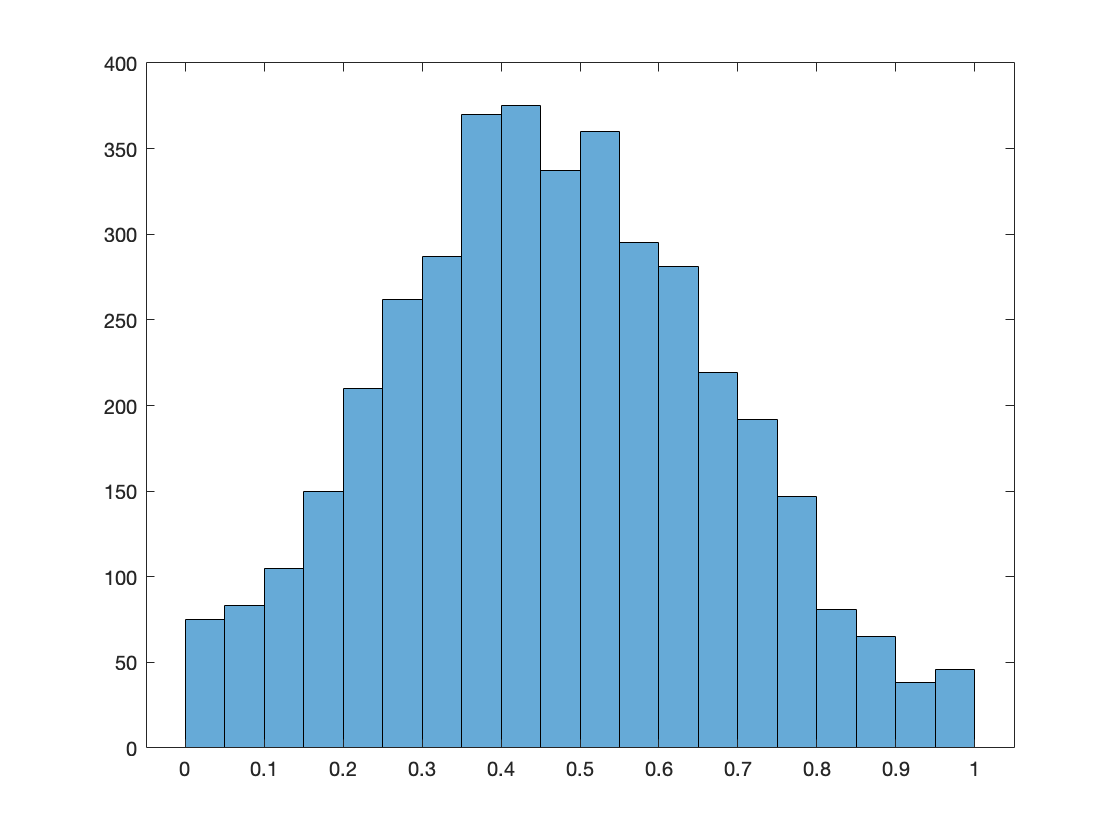

% roll, plot, scale the dataset 
train_x = train_x';
histogram(train_x(:,:));

train_y = train_y'

train_y =      0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


dZ =    -2.0002   -2.0004   -2.0003   -1.9998   -1.9999   -1.9997   -1.9998   -1.9998   -1.9998   -1.9998   -1.9999   -1.9999   -1.9998   -1.9999   -1.9998   -1.9998   -1.9998   -1.9996   -1.9999   -1.9999   -1.9998   -1.9998   -2.0004   -2.0002   -2.0004   -2.0004   -2.0004   -2.0006   -2.0003   -2.0004   -2.0004   -2.0003   -2.0003   -2.0004   -2.0003   -2.0004   -2.0004   -2.0002   -2.0003   -2.0002   -2.0004   -2.0004   -2.0004   -2.0003   -2.0004   -2.0003   -2.0004   -2.0002   -2.0002   -2.0003


dA_prev =    -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022
   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.029

dW =    -0.0059   -0.0144   -0.0060         0   -0.0001         0   -0.0570


db = -2.0003

dZ =          0         0   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022         0         0   -0.0022   -0.0022         0         0         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022         0         0         0         0   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022
   -0.0299   -0.0299   -0.0299         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0299         0   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299         0   -0.0299         0   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299         0   -

dA_prev = 	1.0e+-3 *

   -0.3580   -0.3580   -0.3435    0.0845    0.0101   -0.2544    0.0991    0.0101    0.0845    0.0991    0.0101   -0.2544   -0.3434   -0.3434    0.0991    0.0991   -0.2544   -0.2544    0.0101    0.0101    0.0991    0.0101   -0.3580    0.0846   -0.2545   -0.3435   -0.3580   -0.2691   -0.3580   -0.2545   -0.3435   -0.3435   -0.2545   -0.2545    0.0846   -0.3435   -0.2545    0.0846   -0.3580    0.0846   -0.3580   -0.3435   -0.3435   -0.3435   -0.2690   -0.3435   -0.2545   -0.2545    0.0991   -0.2545
   -0.0048   -0.0048   -0.0088   -0.1325   -0.0678   -0.0776   -0.1365   -0.0678   -0.1325   -0.1365   -0.0678   -0.0776   -0.0088   -0.0088   -0.1365   -0.1365   -0.0776   -0.0776   -0.0678   -0.0678   -0.1365   -0.0678   -0.0048   -0.1326   -0.0776   -0.0088   -0.0048   -0.0737   -0.0048   -0.0776   -0.0088   -0.0088   -0.0776   -0.0776   -0.1326   -0.0088   -0.0776   -0.1326   -0.0048   -0.1326   -0.0048   -0.0088   -0.0088   -0.0088   -0.0736   -0.0088   -0.0776   -0.0

dW =    -0.0007   -0.0003   -0.0005   -0.0009   -0.0007   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0006   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0120   -0.0053   -0.0093   -0.0141   -0.0126   -0.0074   -0.0132   -0.0093   -0.0135   -0.0084   -0.0124   -0.0140   -0.0110   -0.0089   -0.0114   -0.0105   -0.0135   -0.0095   -0.0119   -0.0138   -0.0153   -0.0109   -0.0093   -0.0110   -0.0094   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

db =    -0.0014
   -0.0229
    0.0064
         0
   -0.0001
         0
   -0.0151


dZ =    -2.0004   -2.0006   -2.0005   -1.9996   -1.9997   -1.9995   -1.9996   -1.9997   -1.9996   -1.9996   -1.9997   -1.9997   -1.9996   -1.9997   -1.9996   -1.9996   -1.9996   -1.9994   -1.9997   -1.9997   -1.9996   -1.9997   -2.0005   -2.0004   -2.0006   -2.0005   -2.0006   -2.0008   -2.0004   -2.0006   -2.0006   -2.0005   -2.0005   -2.0006   -2.0005   -2.0006   -2.0006   -2.0004   -2.0005   -2.0004   -2.0005   -2.0006   -2.0006   -2.0005   -2.0006   -2.0005   -2.0006   -2.0004   -2.0004   -2.0005


dA_prev =    -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022
   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.029

dW =    -0.0059   -0.0144   -0.0060         0   -0.0001         0   -0.0570


db = -2.0004

dZ =          0         0   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022         0         0   -0.0022   -0.0022         0         0         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022         0         0         0         0   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022
   -0.0299   -0.0299   -0.0299         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0299         0   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299         0   -0.0299         0   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299         0   -

dA_prev = 	1.0e+-3 *

   -0.3580   -0.3581   -0.3435    0.0846    0.0102   -0.2544    0.0991    0.0102    0.0846    0.0991    0.0102   -0.2544   -0.3433   -0.3433    0.0991    0.0991   -0.2544   -0.2544    0.0102    0.0102    0.0991    0.0102   -0.3581    0.0846   -0.2545   -0.3435   -0.3581   -0.2691   -0.3580   -0.2545   -0.3435   -0.3435   -0.2545   -0.2545    0.0846   -0.3435   -0.2545    0.0846   -0.3581    0.0846   -0.3581   -0.3435   -0.3435   -0.3435   -0.2691   -0.3435   -0.2545   -0.2545    0.0992   -0.2545
   -0.0049   -0.0049   -0.0090   -0.1326   -0.0679   -0.0777   -0.1366   -0.0679   -0.1326   -0.1366   -0.0679   -0.0777   -0.0089   -0.0089   -0.1366   -0.1366   -0.0777   -0.0777   -0.0679   -0.0679   -0.1366   -0.0679   -0.0049   -0.1327   -0.0778   -0.0090   -0.0050   -0.0738   -0.0049   -0.0778   -0.0090   -0.0090   -0.0778   -0.0778   -0.1327   -0.0090   -0.0778   -0.1327   -0.0049   -0.1327   -0.0049   -0.0090   -0.0090   -0.0090   -0.0738   -0.0090   -0.0778   -0.0

dW =    -0.0007   -0.0003   -0.0005   -0.0009   -0.0007   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0006   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0127   -0.0074   -0.0133   -0.0093   -0.0137   -0.0084   -0.0126   -0.0141   -0.0112   -0.0090   -0.0115   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0110   -0.0094   -0.0111   -0.0094   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

db =    -0.0014
   -0.0231
    0.0064
         0
   -0.0001
         0
   -0.0151


dZ =    -2.0006   -2.0008   -2.0007   -1.9994   -1.9995   -1.9994   -1.9995   -1.9995   -1.9994   -1.9994   -1.9995   -1.9995   -1.9995   -1.9995   -1.9994   -1.9994   -1.9994   -1.9992   -1.9995   -1.9995   -1.9994   -1.9995   -2.0007   -2.0006   -2.0008   -2.0007   -2.0008   -2.0010   -2.0006   -2.0008   -2.0008   -2.0007   -2.0007   -2.0008   -2.0007   -2.0008   -2.0008   -2.0006   -2.0007   -2.0006   -2.0007   -2.0008   -2.0008   -2.0007   -2.0008   -2.0007   -2.0008   -2.0006   -2.0006   -2.0007


dA_prev =    -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022
   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.029

dW =    -0.0059   -0.0144   -0.0060         0   -0.0001         0   -0.0570


db = -2.0005

dZ =          0         0   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022         0         0   -0.0022   -0.0022         0         0         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022         0         0         0         0   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022
   -0.0299   -0.0299   -0.0299         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0299         0   -0.0299   -0.0299   -0.0299   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299         0   -0.0299         0   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299         0   -

dA_prev = 	1.0e+-3 *

   -0.3581   -0.3581   -0.3435    0.0846    0.0102   -0.2544    0.0992    0.0102    0.0846    0.0992    0.0102   -0.2544   -0.3433   -0.3433    0.0992    0.0992   -0.2544   -0.2544    0.0102    0.0102    0.0992    0.0102   -0.3581    0.0847   -0.2546   -0.3435   -0.3581   -0.2692   -0.3581   -0.2545   -0.3436   -0.3435   -0.2545   -0.2546    0.0847   -0.3435   -0.2545    0.0847   -0.3581    0.0847   -0.3581   -0.3435   -0.3435   -0.3435   -0.2691   -0.3435   -0.2545   -0.2545    0.0992   -0.2545
   -0.0051   -0.0051   -0.0091   -0.1327   -0.0680   -0.0778   -0.1367   -0.0680   -0.1327   -0.1367   -0.0680   -0.0778   -0.0091   -0.0091   -0.1367   -0.1367   -0.0778   -0.0778   -0.0680   -0.0680   -0.1367   -0.0680   -0.0051   -0.1328   -0.0779   -0.0091   -0.0051   -0.0739   -0.0051   -0.0779   -0.0091   -0.0091   -0.0779   -0.0779   -0.1328   -0.0091   -0.0779   -0.1328   -0.0051   -0.1328   -0.0051   -0.0091   -0.0091   -0.0091   -0.0739   -0.0091   -0.0779   -0.0

dW =    -0.0007   -0.0003   -0.0005   -0.0009   -0.0007   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0006   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0127   -0.0074   -0.0133   -0.0093   -0.0137   -0.0084   -0.0126   -0.0141   -0.0112   -0.0090   -0.0115   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0110   -0.0094   -0.0111   -0.0094   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

db =    -0.0014
   -0.0231
    0.0064
         0
   -0.0001
         0
   -0.0152


dZ =    -2.0007   -2.0009   -2.0009   -1.9993   -1.9994   -1.9992   -1.9993   -1.9993   -1.9993   -1.9992   -1.9993   -1.9993   -1.9993   -1.9993   -1.9993   -1.9993   -1.9993   -1.9991   -1.9993   -1.9994   -1.9992   -1.9993   -2.0009   -2.0007   -2.0010   -2.0009   -2.0010   -2.0012   -2.0008   -2.0009   -2.0010   -2.0009   -2.0008   -2.0010   -2.0008   -2.0010   -2.0009   -2.0008   -2.0009   -2.0008   -2.0009   -2.0010   -2.0010   -2.0009   -2.0010   -2.0009   -2.0009   -2.0008   -2.0008   -2.0009


dA_prev =    -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022
   -0.0299   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.029

dW =    -0.0059   -0.0144   -0.0060         0   -0.0001         0   -0.0571


db = -2.0007

dZ =          0         0   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022         0         0   -0.0022   -0.0022         0         0         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022         0         0         0         0   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022
   -0.0299   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0   -0.0300   -0.0300         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0   -

dA_prev = 	1.0e+-3 *

   -0.3581   -0.3582   -0.3436    0.0847    0.0103   -0.2544    0.0992    0.0103    0.0847    0.0992    0.0103   -0.2544   -0.3433   -0.3433    0.0992    0.0992   -0.2544   -0.2543    0.0103    0.0103    0.0992    0.0103   -0.3581    0.0847   -0.2546   -0.3436   -0.3582   -0.2692   -0.3581   -0.2546   -0.3436   -0.3436   -0.2546   -0.2546    0.0847   -0.3436   -0.2546    0.0847   -0.3581    0.0847   -0.3582   -0.3436   -0.3436   -0.3436   -0.2692   -0.3436   -0.2546   -0.2546    0.0993   -0.2546
   -0.0052   -0.0052   -0.0092   -0.1328   -0.0681   -0.0779   -0.1368   -0.0680   -0.1328   -0.1368   -0.0680   -0.0779   -0.0092   -0.0092   -0.1368   -0.1368   -0.0779   -0.0779   -0.0680   -0.0681   -0.1368   -0.0680   -0.0052   -0.1329   -0.0780   -0.0092   -0.0052   -0.0740   -0.0052   -0.0780   -0.0092   -0.0092   -0.0780   -0.0780   -0.1329   -0.0092   -0.0780   -0.1329   -0.0052   -0.1329   -0.0052   -0.0092   -0.0092   -0.0092   -0.0740   -0.0092   -0.0780   -0.0

dW =    -0.0007   -0.0003   -0.0005   -0.0009   -0.0007   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0006   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0127   -0.0074   -0.0133   -0.0093   -0.0137   -0.0084   -0.0126   -0.0141   -0.0112   -0.0090   -0.0116   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0110   -0.0094   -0.0111   -0.0094   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

db =    -0.0014
   -0.0231
    0.0064
         0
   -0.0001
         0
   -0.0152


dZ =    -2.0009   -2.0011   -2.0010   -1.9991   -1.9992   -1.9990   -1.9991   -1.9991   -1.9991   -1.9991   -1.9991   -1.9991   -1.9991   -1.9991   -1.9991   -1.9991   -1.9991   -1.9989   -1.9992   -1.9992   -1.9991   -1.9991   -2.0011   -2.0009   -2.0011   -2.0011   -2.0011   -2.0013   -2.0010   -2.0011   -2.0012   -2.0010   -2.0010   -2.0011   -2.0010   -2.0012   -2.0011   -2.0009   -2.0010   -2.0009   -2.0011   -2.0011   -2.0012   -2.0010   -2.0011   -2.0010   -2.0011   -2.0010   -2.0009   -2.0011


dA_prev =    -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.030

dW =    -0.0059   -0.0145   -0.0059         0   -0.0001         0   -0.0571


db = -2.0008

dZ =          0         0   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022         0         0   -0.0022   -0.0022         0         0         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022         0         0         0         0   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0   -0.0300   -0.0300         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0   -

dA_prev = 	1.0e+-3 *

   -0.3582   -0.3582   -0.3436    0.0847    0.0104   -0.2543    0.0993    0.0104    0.0847    0.0993    0.0104   -0.2544   -0.3433   -0.3433    0.0993    0.0993   -0.2544   -0.2543    0.0104    0.0104    0.0993    0.0104   -0.3582    0.0848   -0.2546   -0.3436   -0.3582   -0.2692   -0.3582   -0.2546   -0.3436   -0.3436   -0.2546   -0.2546    0.0848   -0.3436   -0.2546    0.0848   -0.3582    0.0848   -0.3582   -0.3436   -0.3436   -0.3436   -0.2692   -0.3436   -0.2546   -0.2546    0.0994   -0.2546
   -0.0053   -0.0053   -0.0093   -0.1329   -0.0681   -0.0780   -0.1369   -0.0681   -0.1329   -0.1369   -0.0681   -0.0780   -0.0093   -0.0093   -0.1369   -0.1369   -0.0780   -0.0780   -0.0681   -0.0681   -0.1369   -0.0681   -0.0053   -0.1330   -0.0781   -0.0093   -0.0053   -0.0741   -0.0053   -0.0781   -0.0093   -0.0093   -0.0781   -0.0781   -0.1330   -0.0093   -0.0781   -0.1330   -0.0053   -0.1330   -0.0053   -0.0093   -0.0093   -0.0093   -0.0741   -0.0093   -0.0781   -0.0

dW =    -0.0007   -0.0003   -0.0005   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0128   -0.0074   -0.0133   -0.0093   -0.0137   -0.0084   -0.0126   -0.0141   -0.0112   -0.0090   -0.0116   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0110   -0.0094   -0.0111   -0.0094   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

db =    -0.0014
   -0.0231
    0.0064
         0
   -0.0001
         0
   -0.0152


Cost after iteration 5.000000: 0.693550

dZ =    -2.0011   -2.0013   -2.0012   -1.9989   -1.9990   -1.9988   -1.9989   -1.9989   -1.9989   -1.9989   -1.9990   -1.9990   -1.9989   -1.9989   -1.9989   -1.9989   -1.9989   -1.9987   -1.9990   -1.9990   -1.9989   -1.9989   -2.0013   -2.0011   -2.0013   -2.0013   -2.0013   -2.0015   -2.0012   -2.0013   -2.0014   -2.0012   -2.0012   -2.0013   -2.0012   -2.0013   -2.0013   -2.0011   -2.0012   -2.0011   -2.0013   -2.0013   -2.0013   -2.0012   -2.0013   -2.0012   -2.0013   -2.0011   -2.0011   -2.0012


dA_prev =    -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.030

dW =    -0.0059   -0.0145   -0.0059         0   -0.0001         0   -0.0571


db = -2.0009

dZ =          0         0   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022         0         0   -0.0022   -0.0022         0         0         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022         0         0         0         0   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0   -0.0300   -0.0300         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0   -

dA_prev = 	1.0e+-3 *

   -0.3582   -0.3582   -0.3436    0.0847    0.0104   -0.2543    0.0993    0.0104    0.0847    0.0993    0.0104   -0.2543   -0.3432   -0.3432    0.0993    0.0993   -0.2543   -0.2543    0.0104    0.0104    0.0993    0.0104   -0.3582    0.0848   -0.2547   -0.3436   -0.3583   -0.2693   -0.3582   -0.2546   -0.3437   -0.3436   -0.2546   -0.2547    0.0848   -0.3437   -0.2546    0.0848   -0.3582    0.0848   -0.3582   -0.3437   -0.3437   -0.3436   -0.2692   -0.3436   -0.2546   -0.2546    0.0994   -0.2546
   -0.0054   -0.0054   -0.0094   -0.1329   -0.0682   -0.0781   -0.1370   -0.0682   -0.1329   -0.1370   -0.0682   -0.0781   -0.0094   -0.0094   -0.1370   -0.1370   -0.0781   -0.0781   -0.0682   -0.0682   -0.1370   -0.0682   -0.0054   -0.1331   -0.0782   -0.0094   -0.0054   -0.0742   -0.0054   -0.0782   -0.0094   -0.0094   -0.0782   -0.0782   -0.1331   -0.0094   -0.0782   -0.1331   -0.0054   -0.1331   -0.0054   -0.0094   -0.0094   -0.0094   -0.0742   -0.0094   -0.0782   -0.0

dW =    -0.0007   -0.0003   -0.0005   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0128   -0.0074   -0.0133   -0.0093   -0.0137   -0.0084   -0.0126   -0.0141   -0.0112   -0.0090   -0.0116   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0110   -0.0094   -0.0111   -0.0094   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

db =    -0.0014
   -0.0231
    0.0064
         0
   -0.0001
         0
   -0.0152


dZ =    -2.0013   -2.0015   -2.0014   -1.9987   -1.9988   -1.9986   -1.9987   -1.9988   -1.9987   -1.9987   -1.9988   -1.9988   -1.9987   -1.9988   -1.9987   -1.9987   -1.9987   -1.9985   -1.9988   -1.9988   -1.9987   -1.9988   -2.0014   -2.0013   -2.0015   -2.0015   -2.0015   -2.0017   -2.0013   -2.0015   -2.0015   -2.0014   -2.0014   -2.0015   -2.0014   -2.0015   -2.0015   -2.0013   -2.0014   -2.0013   -2.0015   -2.0015   -2.0015   -2.0014   -2.0015   -2.0014   -2.0015   -2.0013   -2.0013   -2.0014


dA_prev =    -0.0022   -0.0023   -0.0023   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0023   -0.0022   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0022   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0022   -0.0023
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.030

dW =    -0.0059   -0.0145   -0.0059         0   -0.0001         0   -0.0571


db = -2.0011

dZ =          0         0   -0.0023         0   -0.0022   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022         0         0   -0.0023   -0.0023         0         0         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023         0         0         0         0   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0022   -0.0023
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0   -0.0300   -0.0300         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0   -

dA_prev = 	1.0e+-3 *

   -0.3583   -0.3583   -0.3437    0.0848    0.0105   -0.2543    0.0994    0.0105    0.0848    0.0994    0.0105   -0.2543   -0.3432   -0.3432    0.0994    0.0994   -0.2543   -0.2543    0.0105    0.0105    0.0994    0.0105   -0.3583    0.0849   -0.2547   -0.3437   -0.3583   -0.2693   -0.3583   -0.2547   -0.3437   -0.3437   -0.2547   -0.2547    0.0849   -0.3437   -0.2547    0.0849   -0.3583    0.0849   -0.3583   -0.3437   -0.3437   -0.3437   -0.2693   -0.3437   -0.2547   -0.2547    0.0995   -0.2547
   -0.0055   -0.0055   -0.0095   -0.1330   -0.0683   -0.0782   -0.1370   -0.0683   -0.1330   -0.1370   -0.0683   -0.0782   -0.0095   -0.0095   -0.1370   -0.1370   -0.0782   -0.0782   -0.0683   -0.0683   -0.1370   -0.0683   -0.0055   -0.1332   -0.0783   -0.0095   -0.0055   -0.0743   -0.0055   -0.0783   -0.0095   -0.0095   -0.0783   -0.0783   -0.1332   -0.0095   -0.0783   -0.1332   -0.0055   -0.1332   -0.0055   -0.0095   -0.0095   -0.0095   -0.0743   -0.0095   -0.0783   -0.0

dW =    -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0128   -0.0074   -0.0133   -0.0093   -0.0137   -0.0084   -0.0126   -0.0141   -0.0112   -0.0090   -0.0116   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0110   -0.0094   -0.0111   -0.0094   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

db =    -0.0014
   -0.0231
    0.0064
         0
   -0.0001
         0
   -0.0152


dZ = 1×153
   -2.0015   -2.0017   -2.0016   -1.9985   -1.9986   -1.9985   -1.9986   -1.9986   -1.9985   -1.9985   -1.9986   -1.9986   -1.9986   -1.9986   -1.9985   -1.9985   -1.9985   -1.9983   -1.9986   -1.9986   -1.9985   -1.9986   -2.0016   -2.0015   -2.0017   -2.0016   -2.0017   -2.0019   -2.0015   -2.0017


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0344    0.0344    0.0344    0.0344    0.0344    0.0344    0.0344    0.0344 

dW = 1×7
   -0.0059   -0.0145   -0.0059         0   -0.0001         0   -0.0571


db = -2.0012

dZ = 7×153
         0         0   -0.0023         0   -0.0022   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3583   -0.3583   -0.3437    0.0848    0.0105   -0.2543    0.0994    0.0105    0.0848    0.0994    0.0105   -0.2543   -0.3432   -0.3432    0.0994    0.0994   -0.2543   -0.2543    0.0105    0.0105    0.0994    0.0105   -0.3583    0.0849   -0.2547   -0.3437   -0.3583   -0.2694   -0.3583   -0.2547
   -0.0056   -0.0056   -0.0096   -0.1331   -0.0684   -0.0783   -0.1371   -0.0684   -0.1331   -0.1371   -0.0684   -0.0783   -0.0096   -0.0096   -0.1371   -0.1371   -0.0783   -0.0783   -0.0684   -0.0684   -0.1371   -0.0684   -0.0056   -0.1333   -0.0784   -0.0096   -0.0056   -0.0744   -0.0056   -0.0784
   -0.2389   -0.2390   -0.2335    0.0418   -0.1830   -0.0029    0.0472   -0.1830    0.0418    0.0472   -0.1830   -0.0029   -0.2331   -0.2331    0.0472    0.0472   -0.0029   -0.0029   -0.1830   -0.1830    0.0472   -0.1830   -0.2390    0.0418   -0.0029   -0.2335   -0.2390   -0.0084   -0.2389   -0.0029
   -0.5395   -0.5396   -0.5531   -0.2131   -0.0190   -0.7600   -0.2267   -0.0190

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0128   -0.0074   -0.0133   -0.0094   -0.0137   -0.0084   -0.0126   -0.0142   -0.0112   -0.0090   -0.0116   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0110   -0.0094   -0.0111   -0.0094   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0231
    0.0064
         0
   -0.0001
         0
   -0.0152


dZ = 1×153
   -2.0016   -2.0018   -2.0018   -1.9984   -1.9985   -1.9983   -1.9984   -1.9984   -1.9984   -1.9983   -1.9984   -1.9984   -1.9984   -1.9984   -1.9984   -1.9984   -1.9984   -1.9982   -1.9984   -1.9985   -1.9983   -1.9984   -2.0018   -2.0016   -2.0019   -2.0018   -2.0019   -2.0021   -2.0017   -2.0018


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0344    0.0344    0.0344    0.0344    0.0344    0.0343    0.0344    0.0344 

dW = 1×7
   -0.0059   -0.0146   -0.0059         0   -0.0001         0   -0.0572


db = -2.0013

dZ = 7×153
         0         0   -0.0023         0   -0.0022   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3583   -0.3584   -0.3437    0.0849    0.0106   -0.2543    0.0994    0.0106    0.0849    0.0994    0.0106   -0.2543   -0.3432   -0.3432    0.0994    0.0994   -0.2543   -0.2543    0.0106    0.0106    0.0994    0.0106   -0.3584    0.0850   -0.2548   -0.3438   -0.3584   -0.2694   -0.3584   -0.2547
   -0.0057   -0.0057   -0.0098   -0.1332   -0.0685   -0.0784   -0.1372   -0.0685   -0.1332   -0.1372   -0.0685   -0.0784   -0.0097   -0.0097   -0.1372   -0.1372   -0.0784   -0.0784   -0.0685   -0.0685   -0.1372   -0.0685   -0.0057   -0.1334   -0.0785   -0.0098   -0.0057   -0.0745   -0.0057   -0.0785
   -0.2390   -0.2390   -0.2335    0.0418   -0.1830   -0.0029    0.0472   -0.1830    0.0418    0.0472   -0.1830   -0.0029   -0.2331   -0.2331    0.0472    0.0472   -0.0029   -0.0029   -0.1830   -0.1830    0.0472   -0.1830   -0.2390    0.0418   -0.0029   -0.2335   -0.2390   -0.0084   -0.2390   -0.0029
   -0.5398   -0.5399   -0.5535   -0.2133   -0.0191   -0.7602   -0.2268   -0.0191

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0128   -0.0074   -0.0133   -0.0094   -0.0137   -0.0084   -0.0126   -0.0142   -0.0112   -0.0090   -0.0116   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0110   -0.0094   -0.0111   -0.0094   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0231
    0.0064
         0
   -0.0001
         0
   -0.0152


dZ = 1×153
   -2.0018   -2.0020   -2.0019   -1.9982   -1.9983   -1.9981   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9982   -1.9980   -1.9983   -1.9983   -1.9982   -1.9982   -2.0020   -2.0018   -2.0021   -2.0020   -2.0021   -2.0023   -2.0019   -2.0020


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0344    0.0344    0.0344    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0059   -0.0146   -0.0059         0   -0.0001         0   -0.0572


db = -2.0015

dZ = 7×153
         0         0   -0.0023         0   -0.0022   -0.0022   -0.0022   -0.0022         0   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3584   -0.3584   -0.3438    0.0849    0.0106   -0.2543    0.0995    0.0106    0.0849    0.0995    0.0106   -0.2543   -0.3431   -0.3431    0.0995    0.0995   -0.2543   -0.2543    0.0106    0.0106    0.0995    0.0106   -0.3584    0.0850   -0.2548   -0.3438   -0.3584   -0.2694   -0.3584   -0.2548
   -0.0058   -0.0058   -0.0099   -0.1333   -0.0686   -0.0785   -0.1373   -0.0686   -0.1333   -0.1373   -0.0686   -0.0785   -0.0098   -0.0098   -0.1373   -0.1373   -0.0785   -0.0785   -0.0686   -0.0686   -0.1373   -0.0686   -0.0058   -0.1335   -0.0787   -0.0099   -0.0058   -0.0746   -0.0058   -0.0787
   -0.2390   -0.2390   -0.2335    0.0418   -0.1829   -0.0029    0.0473   -0.1829    0.0418    0.0473   -0.1829   -0.0029   -0.2331   -0.2331    0.0473    0.0473   -0.0029   -0.0029   -0.1829   -0.1829    0.0473   -0.1829   -0.2390    0.0419   -0.0029   -0.2335   -0.2390   -0.0084   -0.2390   -0.0029
   -0.5402   -0.5402   -0.5538   -0.2134   -0.0193   -0.7604   -0.2270   -0.0193

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0128   -0.0074   -0.0133   -0.0094   -0.0137   -0.0085   -0.0126   -0.0142   -0.0112   -0.0090   -0.0116   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0110   -0.0094   -0.0111   -0.0094   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0231
    0.0064
         0
   -0.0001
         0
   -0.0152


Cost after iteration 10.000000: 0.693890

dZ = 1×153
   -2.0020   -2.0022   -2.0021   -1.9980   -1.9981   -1.9979   -1.9980   -1.9980   -1.9980   -1.9980   -1.9981   -1.9981   -1.9980   -1.9980   -1.9980   -1.9980   -1.9980   -1.9978   -1.9981   -1.9981   -1.9980   -1.9980   -2.0022   -2.0020   -2.0022   -2.0022   -2.0022   -2.0024   -2.0021   -2.0022


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0344    0.0344    0.0344    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0059   -0.0146   -0.0059         0   -0.0001         0   -0.0572


db = -2.0016

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3584   -0.3585   -0.3438    0.0849    0.0107   -0.2543    0.0995    0.0107    0.0849    0.0995    0.0107   -0.2543   -0.3431   -0.3431    0.0995    0.0995   -0.2543   -0.2543    0.0107    0.0107    0.0995    0.0107   -0.3585    0.0851   -0.2548   -0.3438   -0.3585   -0.2695   -0.3584   -0.2548
   -0.0060   -0.0060   -0.0100   -0.1334   -0.0687   -0.0786   -0.1374   -0.0687   -0.1334   -0.1374   -0.0687   -0.0786   -0.0100   -0.0100   -0.1374   -0.1374   -0.0786   -0.0786   -0.0687   -0.0687   -0.1374   -0.0687   -0.0060   -0.1336   -0.0788   -0.0100   -0.0060   -0.0748   -0.0060   -0.0788
   -0.2390   -0.2390   -0.2335    0.0418   -0.1829   -0.0029    0.0473   -0.1829    0.0418    0.0473   -0.1829   -0.0029   -0.2330   -0.2330    0.0473    0.0473   -0.0029   -0.0029   -0.1829   -0.1829    0.0473   -0.1829   -0.2390    0.0419   -0.0029   -0.2335   -0.2390   -0.0084   -0.2390   -0.0029
   -0.5405   -0.5405   -0.5541   -0.2135   -0.0195   -0.7606   -0.2271   -0.0195

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0128   -0.0074   -0.0133   -0.0094   -0.0137   -0.0085   -0.0126   -0.0142   -0.0112   -0.0090   -0.0116   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0110   -0.0094   -0.0111   -0.0094   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0231
    0.0064
         0
   -0.0001
         0
   -0.0152


dZ = 1×153
   -2.0022   -2.0024   -2.0023   -1.9978   -1.9979   -1.9977   -1.9978   -1.9979   -1.9978   -1.9978   -1.9979   -1.9979   -1.9978   -1.9979   -1.9978   -1.9978   -1.9978   -1.9976   -1.9979   -1.9979   -1.9978   -1.9979   -2.0023   -2.0022   -2.0024   -2.0024   -2.0024   -2.0026   -2.0022   -2.0024


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0344    0.0344    0.0344    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0059   -0.0146   -0.0059         0   -0.0001         0   -0.0572


db = -2.0018

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3585   -0.3585   -0.3439    0.0850    0.0108   -0.2543    0.0996    0.0108    0.0850    0.0996    0.0108   -0.2543   -0.3431   -0.3431    0.0996    0.0996   -0.2543   -0.2542    0.0108    0.0108    0.0996    0.0108   -0.3585    0.0852   -0.2548   -0.3439   -0.3585   -0.2695   -0.3585   -0.2548
   -0.0061   -0.0061   -0.0101   -0.1334   -0.0688   -0.0787   -0.1375   -0.0688   -0.1334   -0.1375   -0.0688   -0.0787   -0.0101   -0.0101   -0.1375   -0.1375   -0.0787   -0.0787   -0.0688   -0.0688   -0.1375   -0.0688   -0.0061   -0.1337   -0.0789   -0.0101   -0.0061   -0.0749   -0.0061   -0.0789
   -0.2390   -0.2390   -0.2335    0.0418   -0.1828   -0.0029    0.0473   -0.1828    0.0418    0.0473   -0.1828   -0.0029   -0.2330   -0.2330    0.0473    0.0473   -0.0029   -0.0029   -0.1828   -0.1828    0.0473   -0.1828   -0.2390    0.0419   -0.0029   -0.2335   -0.2390   -0.0084   -0.2390   -0.0029
   -0.5408   -0.5408   -0.5544   -0.2137   -0.0197   -0.7607   -0.2273   -0.0197

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0128   -0.0074   -0.0133   -0.0094   -0.0137   -0.0085   -0.0126   -0.0142   -0.0112   -0.0090   -0.0116   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0110   -0.0094   -0.0111   -0.0094   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0231
    0.0064
         0
   -0.0001
         0
   -0.0153


dZ = 1×153
   -2.0024   -2.0026   -2.0025   -1.9976   -1.9977   -1.9976   -1.9977   -1.9977   -1.9976   -1.9976   -1.9977   -1.9977   -1.9977   -1.9977   -1.9976   -1.9976   -1.9976   -1.9974   -1.9977   -1.9977   -1.9976   -1.9977   -2.0025   -2.0024   -2.0026   -2.0025   -2.0026   -2.0028   -2.0024   -2.0026


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0344    0.0344    0.0344    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0059   -0.0147   -0.0059         0   -0.0001         0   -0.0573


db = -2.0019

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3585   -0.3586   -0.3439    0.0850    0.0108   -0.2542    0.0996    0.0108    0.0850    0.0996    0.0108   -0.2543   -0.3431   -0.3431    0.0996    0.0996   -0.2543   -0.2542    0.0108    0.0108    0.0996    0.0108   -0.3586    0.0852   -0.2549   -0.3439   -0.3586   -0.2696   -0.3585   -0.2549
   -0.0062   -0.0062   -0.0102   -0.1335   -0.0689   -0.0788   -0.1376   -0.0689   -0.1335   -0.1375   -0.0689   -0.0788   -0.0102   -0.0102   -0.1375   -0.1375   -0.0788   -0.0788   -0.0689   -0.0689   -0.1375   -0.0689   -0.0062   -0.1338   -0.0790   -0.0102   -0.0062   -0.0750   -0.0062   -0.0790
   -0.2390   -0.2390   -0.2335    0.0418   -0.1828   -0.0029    0.0473   -0.1828    0.0418    0.0473   -0.1828   -0.0029   -0.2330   -0.2330    0.0473    0.0473   -0.0029   -0.0029   -0.1828   -0.1828    0.0473   -0.1828   -0.2390    0.0419   -0.0029   -0.2335   -0.2390   -0.0084   -0.2390   -0.0029
   -0.5411   -0.5411   -0.5548   -0.2138   -0.0199   -0.7609   -0.2274   -0.0199

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0128   -0.0074   -0.0133   -0.0094   -0.0137   -0.0085   -0.0126   -0.0142   -0.0112   -0.0090   -0.0116   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0110   -0.0094   -0.0111   -0.0094   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0231
    0.0064
         0
   -0.0001
         0
   -0.0153


dZ = 1×153
   -2.0025   -2.0027   -2.0027   -1.9975   -1.9976   -1.9974   -1.9975   -1.9975   -1.9975   -1.9974   -1.9975   -1.9975   -1.9975   -1.9975   -1.9975   -1.9975   -1.9975   -1.9973   -1.9975   -1.9976   -1.9974   -1.9975   -2.0027   -2.0025   -2.0028   -2.0027   -2.0028   -2.0030   -2.0026   -2.0027


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0344    0.0344    0.0344    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0059   -0.0147   -0.0059         0   -0.0001         0   -0.0573


db = -2.0020

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3586   -0.3586   -0.3439    0.0850    0.0109   -0.2542    0.0997    0.0109    0.0850    0.0997    0.0109   -0.2542   -0.3430   -0.3430    0.0997    0.0997   -0.2542   -0.2542    0.0109    0.0109    0.0997    0.0109   -0.3586    0.0853   -0.2549   -0.3439   -0.3586   -0.2696   -0.3586   -0.2549
   -0.0063   -0.0063   -0.0103   -0.1336   -0.0690   -0.0789   -0.1376   -0.0690   -0.1336   -0.1376   -0.0690   -0.0789   -0.0103   -0.0103   -0.1376   -0.1376   -0.0789   -0.0789   -0.0690   -0.0690   -0.1376   -0.0690   -0.0063   -0.1340   -0.0791   -0.0103   -0.0063   -0.0751   -0.0063   -0.0791
   -0.2390   -0.2390   -0.2335    0.0419   -0.1827   -0.0029    0.0473   -0.1827    0.0419    0.0473   -0.1827   -0.0029   -0.2329   -0.2329    0.0473    0.0473   -0.0029   -0.0029   -0.1827   -0.1827    0.0473   -0.1827   -0.2390    0.0420   -0.0029   -0.2336   -0.2390   -0.0084   -0.2390   -0.0029
   -0.5414   -0.5415   -0.5551   -0.2139   -0.0201   -0.7611   -0.2276   -0.0201

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0128   -0.0074   -0.0133   -0.0094   -0.0137   -0.0085   -0.0126   -0.0142   -0.0112   -0.0090   -0.0116   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0110   -0.0094   -0.0111   -0.0095   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0231
    0.0064
         0
   -0.0001
         0
   -0.0153


dZ = 1×153
   -2.0027   -2.0029   -2.0028   -1.9973   -1.9974   -1.9972   -1.9973   -1.9973   -1.9973   -1.9973   -1.9973   -1.9973   -1.9973   -1.9973   -1.9973   -1.9973   -1.9973   -1.9971   -1.9974   -1.9974   -1.9973   -1.9973   -2.0029   -2.0027   -2.0030   -2.0029   -2.0030   -2.0032   -2.0028   -2.0029


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0344    0.0344    0.0344    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0059   -0.0147   -0.0059         0   -0.0001         0   -0.0573


db = -2.0022

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3586   -0.3586   -0.3440    0.0851    0.0109   -0.2542    0.0997    0.0109    0.0851    0.0997    0.0109   -0.2542   -0.3430   -0.3430    0.0997    0.0997   -0.2542   -0.2542    0.0109    0.0109    0.0997    0.0109   -0.3586    0.0853   -0.2549   -0.3440   -0.3587   -0.2696   -0.3586   -0.2549
   -0.0064   -0.0064   -0.0104   -0.1337   -0.0691   -0.0790   -0.1377   -0.0691   -0.1337   -0.1377   -0.0691   -0.0790   -0.0104   -0.0104   -0.1377   -0.1377   -0.0790   -0.0790   -0.0691   -0.0691   -0.1377   -0.0691   -0.0064   -0.1341   -0.0792   -0.0104   -0.0064   -0.0752   -0.0064   -0.0792
   -0.2390   -0.2391   -0.2336    0.0419   -0.1826   -0.0029    0.0473   -0.1826    0.0419    0.0473   -0.1826   -0.0029   -0.2329   -0.2329    0.0473    0.0473   -0.0029   -0.0029   -0.1826   -0.1826    0.0473   -0.1826   -0.2390    0.0420   -0.0029   -0.2336   -0.2391   -0.0084   -0.2390   -0.0029
   -0.5417   -0.5418   -0.5554   -0.2141   -0.0202   -0.7613   -0.2277   -0.0202

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0128   -0.0074   -0.0133   -0.0094   -0.0137   -0.0085   -0.0127   -0.0142   -0.0112   -0.0090   -0.0116   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0110   -0.0094   -0.0111   -0.0095   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0231
    0.0064
         0
   -0.0001
         0
   -0.0153


Cost after iteration 15.000000: 0.694230

dZ = 1×153
   -2.0029   -2.0031   -2.0030   -1.9971   -1.9972   -1.9970   -1.9971   -1.9971   -1.9971   -1.9971   -1.9972   -1.9971   -1.9971   -1.9971   -1.9971   -1.9971   -1.9971   -1.9969   -1.9972   -1.9972   -1.9971   -1.9971   -2.0031   -2.0029   -2.0031   -2.0031   -2.0031   -2.0033   -2.0030   -2.0031


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0344    0.0344    0.0344    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0059   -0.0147   -0.0059         0   -0.0001         0   -0.0573


db = -2.0023

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3587   -0.3587   -0.3440    0.0851    0.0110   -0.2542    0.0998    0.0110    0.0851    0.0998    0.0110   -0.2542   -0.3430   -0.3430    0.0998    0.0998   -0.2542   -0.2542    0.0110    0.0110    0.0998    0.0110   -0.3587    0.0854   -0.2550   -0.3440   -0.3587   -0.2697   -0.3587   -0.2550
   -0.0065   -0.0065   -0.0106   -0.1338   -0.0692   -0.0791   -0.1378   -0.0692   -0.1338   -0.1378   -0.0692   -0.0791   -0.0105   -0.0105   -0.1378   -0.1378   -0.0791   -0.0791   -0.0692   -0.0692   -0.1378   -0.0692   -0.0065   -0.1342   -0.0793   -0.0106   -0.0065   -0.0753   -0.0065   -0.0793
   -0.2390   -0.2391   -0.2336    0.0419   -0.1826   -0.0029    0.0474   -0.1826    0.0419    0.0474   -0.1826   -0.0029   -0.2329   -0.2329    0.0474    0.0474   -0.0029   -0.0029   -0.1826   -0.1826    0.0474   -0.1826   -0.2391    0.0420   -0.0029   -0.2336   -0.2391   -0.0084   -0.2390   -0.0029
   -0.5420   -0.5421   -0.5557   -0.2142   -0.0204   -0.7615   -0.2278   -0.0204

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0128   -0.0074   -0.0133   -0.0094   -0.0137   -0.0085   -0.0127   -0.0142   -0.0112   -0.0090   -0.0116   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0111   -0.0094   -0.0111   -0.0095   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0231
    0.0064
         0
   -0.0001
         0
   -0.0153


dZ = 1×153
   -2.0031   -2.0033   -2.0032   -1.9969   -1.9970   -1.9968   -1.9969   -1.9970   -1.9969   -1.9969   -1.9970   -1.9970   -1.9969   -1.9970   -1.9969   -1.9969   -1.9969   -1.9967   -1.9970   -1.9970   -1.9969   -1.9970   -2.0032   -2.0031   -2.0033   -2.0033   -2.0033   -2.0035   -2.0031   -2.0033


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0344    0.0344    0.0344    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0059   -0.0148   -0.0059         0   -0.0001         0   -0.0574


db = -2.0024

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3587   -0.3587   -0.3440    0.0852    0.0110   -0.2542    0.0998    0.0110    0.0852    0.0998    0.0110   -0.2542   -0.3430   -0.3430    0.0998    0.0998   -0.2542   -0.2542    0.0110    0.0110    0.0998    0.0110   -0.3587    0.0854   -0.2550   -0.3440   -0.3587   -0.2697   -0.3587   -0.2550
   -0.0066   -0.0066   -0.0107   -0.1339   -0.0693   -0.0792   -0.1379   -0.0693   -0.1339   -0.1379   -0.0693   -0.0792   -0.0106   -0.0106   -0.1379   -0.1379   -0.0792   -0.0792   -0.0693   -0.0693   -0.1379   -0.0693   -0.0066   -0.1343   -0.0795   -0.0107   -0.0066   -0.0754   -0.0066   -0.0795
   -0.2391   -0.2391   -0.2336    0.0419   -0.1825   -0.0029    0.0474   -0.1825    0.0419    0.0474   -0.1825   -0.0029   -0.2328   -0.2328    0.0474    0.0474   -0.0029   -0.0029   -0.1825   -0.1825    0.0474   -0.1825   -0.2391    0.0420   -0.0030   -0.2336   -0.2391   -0.0084   -0.2391   -0.0030
   -0.5424   -0.5424   -0.5560   -0.2144   -0.0206   -0.7616   -0.2280   -0.0206

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0128   -0.0074   -0.0133   -0.0094   -0.0137   -0.0085   -0.0127   -0.0142   -0.0112   -0.0090   -0.0116   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0111   -0.0094   -0.0111   -0.0095   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0232
    0.0064
         0
   -0.0001
         0
   -0.0153


dZ = 1×153
   -2.0033   -2.0035   -2.0034   -1.9967   -1.9968   -1.9967   -1.9968   -1.9968   -1.9967   -1.9967   -1.9968   -1.9968   -1.9968   -1.9968   -1.9967   -1.9967   -1.9967   -1.9965   -1.9968   -1.9968   -1.9967   -1.9968   -2.0034   -2.0033   -2.0035   -2.0034   -2.0035   -2.0037   -2.0033   -2.0035


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0344    0.0344    0.0344    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0059   -0.0148   -0.0059         0   -0.0001         0   -0.0574


db = -2.0026

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3587   -0.3588   -0.3441    0.0852    0.0111   -0.2542    0.0998    0.0111    0.0852    0.0998    0.0111   -0.2542   -0.3429   -0.3429    0.0998    0.0998   -0.2542   -0.2542    0.0111    0.0111    0.0998    0.0111   -0.3588    0.0855   -0.2551   -0.3441   -0.3588   -0.2698   -0.3588   -0.2550
   -0.0067   -0.0067   -0.0108   -0.1339   -0.0694   -0.0793   -0.1380   -0.0694   -0.1339   -0.1380   -0.0694   -0.0793   -0.0108   -0.0108   -0.1380   -0.1380   -0.0793   -0.0793   -0.0694   -0.0694   -0.1380   -0.0694   -0.0067   -0.1344   -0.0796   -0.0108   -0.0067   -0.0755   -0.0067   -0.0796
   -0.2391   -0.2391   -0.2336    0.0419   -0.1825   -0.0029    0.0474   -0.1825    0.0419    0.0474   -0.1825   -0.0029   -0.2328   -0.2328    0.0474    0.0474   -0.0029   -0.0029   -0.1825   -0.1825    0.0474   -0.1825   -0.2391    0.0421   -0.0030   -0.2336   -0.2391   -0.0085   -0.2391   -0.0030
   -0.5427   -0.5427   -0.5564   -0.2145   -0.0208   -0.7618   -0.2281   -0.0208

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0128   -0.0074   -0.0133   -0.0094   -0.0137   -0.0085   -0.0127   -0.0142   -0.0112   -0.0090   -0.0116   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0111   -0.0094   -0.0111   -0.0095   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0232
    0.0064
         0
   -0.0001
         0
   -0.0153


dZ = 1×153
   -2.0035   -2.0037   -2.0036   -1.9966   -1.9967   -1.9965   -1.9966   -1.9966   -1.9966   -1.9965   -1.9966   -1.9966   -1.9966   -1.9966   -1.9966   -1.9966   -1.9966   -1.9964   -1.9966   -1.9967   -1.9965   -1.9966   -2.0036   -2.0034   -2.0037   -2.0036   -2.0037   -2.0039   -2.0035   -2.0037


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0344    0.0344    0.0344    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0059   -0.0148   -0.0059         0   -0.0001         0   -0.0574


db = -2.0027

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299         0         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3588   -0.3588   -0.3441    0.0852    0.0112   -0.2542    0.0999    0.0112    0.0852    0.0999    0.0112   -0.2542   -0.3429   -0.3429    0.0999    0.0999   -0.2542   -0.2542    0.0112    0.0112    0.0999    0.0112   -0.3588    0.0855   -0.2551   -0.3441   -0.3588   -0.2698   -0.3588   -0.2551
   -0.0069   -0.0069   -0.0109   -0.1340   -0.0695   -0.0794   -0.1381   -0.0695   -0.1340   -0.1381   -0.0695   -0.0794   -0.0109   -0.0109   -0.1381   -0.1381   -0.0794   -0.0794   -0.0695   -0.0695   -0.1381   -0.0695   -0.0069   -0.1345   -0.0797   -0.0109   -0.0069   -0.0756   -0.0069   -0.0797
   -0.2391   -0.2391   -0.2336    0.0419   -0.1824   -0.0030    0.0474   -0.1824    0.0419    0.0474   -0.1824   -0.0030   -0.2328   -0.2328    0.0474    0.0474   -0.0030   -0.0030   -0.1824   -0.1824    0.0474   -0.1824   -0.2391    0.0421   -0.0030   -0.2336   -0.2391   -0.0085   -0.2391   -0.0030
   -0.5430   -0.5430   -0.5567   -0.2146   -0.0210   -0.7620   -0.2283   -0.0210

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0008   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0121   -0.0053   -0.0094   -0.0143   -0.0128   -0.0074   -0.0133   -0.0094   -0.0137   -0.0085   -0.0127   -0.0142   -0.0112   -0.0090   -0.0116   -0.0106   -0.0136   -0.0096   -0.0120   -0.0139   -0.0155   -0.0111   -0.0094   -0.0111   -0.0095   -0.0064
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0232
    0.0064
         0
   -0.0001
         0
   -0.0153


dZ = 1×153
   -2.0036   -2.0038   -2.0038   -1.9964   -1.9965   -1.9963   -1.9964   -1.9964   -1.9964   -1.9964   -1.9965   -1.9964   -1.9964   -1.9964   -1.9964   -1.9964   -1.9964   -1.9962   -1.9965   -1.9965   -1.9964   -1.9964   -2.0038   -2.0036   -2.0039   -2.0038   -2.0039   -2.0041   -2.0037   -2.0038


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0344    0.0344    0.0344    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0059   -0.0148   -0.0059         0   -0.0001         0   -0.0574


db = -2.0028

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3588   -0.3589   -0.3442    0.0853    0.0112   -0.2542    0.0999    0.0112    0.0853    0.0999    0.0112   -0.2542   -0.3429   -0.3429    0.0999    0.0999   -0.2542   -0.2541   -0.3429    0.0112    0.0999    0.0112   -0.3589    0.0856   -0.2551   -0.3442   -0.3589   -0.2699   -0.3588   -0.2551
   -0.0070   -0.0070   -0.0110   -0.1341   -0.0696   -0.0795   -0.1381   -0.0696   -0.1341   -0.1381   -0.0696   -0.0795   -0.0110   -0.0110   -0.1381   -0.1381   -0.0795   -0.0795   -0.0110   -0.0696   -0.1381   -0.0696   -0.0070   -0.1346   -0.0798   -0.0110   -0.0070   -0.0758   -0.0070   -0.0798
   -0.2391   -0.2391   -0.2336    0.0420   -0.1824   -0.0030    0.0474   -0.1823    0.0420    0.0474   -0.1824   -0.0030   -0.2327   -0.2328    0.0474    0.0474   -0.0030   -0.0030   -0.2328   -0.1824    0.0474   -0.1823   -0.2391    0.0421   -0.0030   -0.2336   -0.2391   -0.0085   -0.2391   -0.0030
   -0.5433   -0.5434   -0.5570   -0.2148   -0.0212   -0.7622   -0.2284   -0.0212

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0123   -0.0053   -0.0095   -0.0144   -0.0129   -0.0075   -0.0134   -0.0094   -0.0138   -0.0086   -0.0128   -0.0144   -0.0113   -0.0091   -0.0117   -0.0107   -0.0138   -0.0096   -0.0122   -0.0140   -0.0157   -0.0111   -0.0094   -0.0112   -0.0095   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0234
    0.0064
         0
   -0.0001
         0
   -0.0154


Cost after iteration 20.000000: 0.694570

dZ = 1×153
   -2.0038   -2.0040   -2.0039   -1.9962   -1.9963   -1.9961   -1.9962   -1.9962   -1.9962   -1.9962   -1.9963   -1.9962   -1.9962   -1.9962   -1.9962   -1.9962   -1.9962   -1.9960   -1.9963   -1.9963   -1.9962   -1.9962   -2.0040   -2.0038   -2.0040   -2.0040   -2.0040   -2.0042   -2.0039   -2.0040


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0344    0.0344    0.0344    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0059   -0.0149   -0.0059         0   -0.0001         0   -0.0575


db = -2.0030

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3589   -0.3589   -0.3442    0.0853    0.0113   -0.2541    0.1000    0.0113    0.0853    0.1000    0.0113   -0.2542   -0.3429   -0.3429    0.1000    0.1000   -0.2542   -0.2541   -0.3429    0.0113    0.1000    0.0113   -0.3589    0.0856   -0.2552   -0.3442   -0.3589   -0.2699   -0.3589   -0.2551
   -0.0071   -0.0071   -0.0111   -0.1342   -0.0697   -0.0796   -0.1382   -0.0697   -0.1342   -0.1382   -0.0697   -0.0796   -0.0111   -0.0111   -0.1382   -0.1382   -0.0796   -0.0796   -0.0111   -0.0697   -0.1382   -0.0697   -0.0071   -0.1347   -0.0799   -0.0111   -0.0071   -0.0759   -0.0071   -0.0799
   -0.2391   -0.2391   -0.2336    0.0420   -0.1823   -0.0030    0.0475   -0.1823    0.0420    0.0475   -0.1823   -0.0030   -0.2327   -0.2327    0.0475    0.0475   -0.0030   -0.0030   -0.2327   -0.1823    0.0475   -0.1823   -0.2391    0.0421   -0.0030   -0.2336   -0.2391   -0.0085   -0.2391   -0.0030
   -0.5436   -0.5437   -0.5573   -0.2149   -0.0214   -0.7624   -0.2285   -0.0214

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0123   -0.0053   -0.0095   -0.0144   -0.0129   -0.0075   -0.0134   -0.0094   -0.0138   -0.0086   -0.0128   -0.0144   -0.0113   -0.0091   -0.0117   -0.0107   -0.0138   -0.0096   -0.0122   -0.0140   -0.0157   -0.0111   -0.0094   -0.0112   -0.0095   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0234
    0.0064
         0
   -0.0001
         0
   -0.0154


dZ = 1×153
   -2.0040   -2.0042   -2.0041   -1.9960   -1.9961   -1.9959   -1.9960   -1.9961   -1.9960   -1.9960   -1.9961   -1.9961   -1.9960   -1.9961   -1.9960   -1.9960   -1.9960   -1.9958   -1.9961   -1.9961   -1.9960   -1.9961   -2.0042   -2.0040   -2.0042   -2.0042   -2.0042   -2.0044   -2.0041   -2.0042


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0301   -0.0300   -0.0300
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0344    0.0345    0.0344    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0059   -0.0149   -0.0059         0   -0.0001         0   -0.0575


db = -2.0031

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0300   -0.0300   -0.0300         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0300         0   -0.0300   -0.0300   -0.0300   -0.0301   -0.0300   -0.0300
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3589   -0.3590   -0.3442    0.0854    0.0113   -0.2541    0.1000    0.0113    0.0854    0.1000    0.0113   -0.2541   -0.3428   -0.3428    0.1000    0.1000   -0.2541   -0.2541   -0.3429    0.0113    0.1000    0.0113   -0.3590    0.0857   -0.2552   -0.3442   -0.3590   -0.2699   -0.3589   -0.2552
   -0.0072   -0.0072   -0.0112   -0.1343   -0.0698   -0.0797   -0.1383   -0.0698   -0.1343   -0.1383   -0.0698   -0.0797   -0.0112   -0.0112   -0.1383   -0.1383   -0.0797   -0.0797   -0.0112   -0.0698   -0.1383   -0.0698   -0.0072   -0.1348   -0.0800   -0.0112   -0.0072   -0.0760   -0.0072   -0.0800
   -0.2391   -0.2391   -0.2336    0.0420   -0.1822   -0.0030    0.0475   -0.1822    0.0420    0.0475   -0.1822   -0.0030   -0.2327   -0.2327    0.0475    0.0475   -0.0030   -0.0030   -0.2327   -0.1822    0.0475   -0.1822   -0.2391    0.0422   -0.0030   -0.2336   -0.2391   -0.0085   -0.2391   -0.0030
   -0.5439   -0.5440   -0.5577   -0.2150   -0.0215   -0.7625   -0.2287   -0.0215

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0123   -0.0053   -0.0095   -0.0144   -0.0129   -0.0075   -0.0134   -0.0094   -0.0138   -0.0086   -0.0128   -0.0144   -0.0113   -0.0091   -0.0117   -0.0107   -0.0138   -0.0096   -0.0122   -0.0140   -0.0157   -0.0111   -0.0094   -0.0112   -0.0095   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0234
    0.0064
         0
   -0.0001
         0
   -0.0154


dZ = 1×153
   -2.0042   -2.0044   -2.0043   -1.9958   -1.9960   -1.9958   -1.9959   -1.9959   -1.9958   -1.9958   -1.9959   -1.9959   -1.9959   -1.9959   -1.9958   -1.9958   -1.9958   -1.9956   -1.9959   -1.9960   -1.9958   -1.9959   -2.0043   -2.0042   -2.0044   -2.0044   -2.0044   -2.0046   -2.0042   -2.0044


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0149   -0.0059         0   -0.0001         0   -0.0575


db = -2.0033

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3590   -0.3590   -0.3443    0.0854    0.0114   -0.2541    0.1001    0.0114    0.0854    0.1001    0.0114   -0.2541   -0.3428   -0.3428    0.1001    0.1001   -0.2541   -0.2541   -0.3428    0.0114    0.1001    0.0114   -0.3590    0.0858   -0.2552   -0.3443   -0.3590   -0.2700   -0.3590   -0.2552
   -0.0073   -0.0073   -0.0114   -0.1344   -0.0699   -0.0798   -0.1384   -0.0699   -0.1344   -0.1384   -0.0699   -0.0798   -0.0113   -0.0113   -0.1384   -0.1384   -0.0798   -0.0798   -0.0113   -0.0699   -0.1384   -0.0699   -0.0073   -0.1349   -0.0801   -0.0114   -0.0073   -0.0761   -0.0073   -0.0801
   -0.2391   -0.2392   -0.2336    0.0420   -0.1822   -0.0030    0.0475   -0.1822    0.0420    0.0475   -0.1822   -0.0030   -0.2327   -0.2327    0.0475    0.0475   -0.0030   -0.0030   -0.2327   -0.1822    0.0475   -0.1822   -0.2392    0.0422   -0.0030   -0.2336   -0.2392   -0.0085   -0.2391   -0.0030
   -0.5442   -0.5443   -0.5580   -0.2152   -0.0217   -0.7627   -0.2288   -0.0217

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0123   -0.0053   -0.0095   -0.0144   -0.0129   -0.0075   -0.0134   -0.0094   -0.0138   -0.0086   -0.0128   -0.0144   -0.0113   -0.0091   -0.0117   -0.0107   -0.0138   -0.0096   -0.0122   -0.0140   -0.0157   -0.0111   -0.0094   -0.0112   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0234
    0.0064
         0
   -0.0001
         0
   -0.0154


dZ = 1×153
   -2.0044   -2.0046   -2.0045   -1.9957   -1.9958   -1.9956   -1.9957   -1.9957   -1.9957   -1.9956   -1.9957   -1.9957   -1.9957   -1.9957   -1.9957   -1.9957   -1.9957   -1.9955   -1.9957   -1.9958   -1.9956   -1.9957   -2.0045   -2.0044   -2.0046   -2.0045   -2.0046   -2.0048   -2.0044   -2.0046


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0149   -0.0059         0   -0.0001         0   -0.0575


db = -2.0034

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3590   -0.3591   -0.3443    0.0854    0.0114   -0.2541    0.1001    0.0114    0.0854    0.1001    0.0114   -0.2541   -0.3428   -0.3428    0.1001    0.1001   -0.2541   -0.2541   -0.3428    0.0114    0.1001    0.0114   -0.3591    0.0858   -0.2553   -0.3443   -0.3591   -0.2700   -0.3590   -0.2553
   -0.0074   -0.0074   -0.0115   -0.1344   -0.0700   -0.0799   -0.1385   -0.0700   -0.1344   -0.1385   -0.0700   -0.0799   -0.0114   -0.0114   -0.1385   -0.1385   -0.0799   -0.0799   -0.0114   -0.0700   -0.1385   -0.0700   -0.0074   -0.1350   -0.0803   -0.0115   -0.0074   -0.0762   -0.0074   -0.0803
   -0.2391   -0.2392   -0.2336    0.0420   -0.1821   -0.0030    0.0475   -0.1821    0.0420    0.0475   -0.1821   -0.0030   -0.2326   -0.2326    0.0475    0.0475   -0.0030   -0.0030   -0.2326   -0.1821    0.0475   -0.1821   -0.2392    0.0422   -0.0030   -0.2337   -0.2392   -0.0085   -0.2392   -0.0030
   -0.5446   -0.5446   -0.5583   -0.2153   -0.0219   -0.7629   -0.2290   -0.0219

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0123   -0.0053   -0.0095   -0.0144   -0.0129   -0.0075   -0.0134   -0.0094   -0.0138   -0.0086   -0.0128   -0.0144   -0.0114   -0.0091   -0.0117   -0.0107   -0.0138   -0.0096   -0.0122   -0.0140   -0.0157   -0.0111   -0.0094   -0.0112   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0234
    0.0064
         0
   -0.0001
         0
   -0.0154


dZ = 1×153
   -2.0045   -2.0047   -2.0047   -1.9955   -1.9956   -1.9954   -1.9955   -1.9955   -1.9955   -1.9955   -1.9956   -1.9955   -1.9955   -1.9955   -1.9955   -1.9955   -1.9955   -1.9953   -1.9956   -1.9956   -1.9955   -1.9955   -2.0047   -2.0045   -2.0048   -2.0047   -2.0048   -2.0050   -2.0046   -2.0047


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0150   -0.0059         0   -0.0001         0   -0.0575


db = -2.0035

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3591   -0.3591   -0.3443    0.0855    0.0115   -0.2541    0.1002    0.0115    0.0855    0.1002    0.0115   -0.2541   -0.3428   -0.3428    0.1002    0.1002   -0.2541   -0.2541   -0.3428    0.0115    0.1002    0.0115   -0.3591    0.0859   -0.2553   -0.3444   -0.3591   -0.2701   -0.3591   -0.2553
   -0.0075   -0.0075   -0.0116   -0.1345   -0.0701   -0.0800   -0.1386   -0.0701   -0.1345   -0.1386   -0.0701   -0.0800   -0.0115   -0.0115   -0.1386   -0.1386   -0.0800   -0.0800   -0.0115   -0.0701   -0.1386   -0.0701   -0.0075   -0.1351   -0.0804   -0.0116   -0.0075   -0.0763   -0.0075   -0.0804
   -0.2392   -0.2392   -0.2337    0.0420   -0.1821   -0.0030    0.0475   -0.1821    0.0420    0.0475   -0.1821   -0.0030   -0.2326   -0.2326    0.0475    0.0475   -0.0030   -0.0030   -0.2326   -0.1821    0.0475   -0.1821   -0.2392    0.0422   -0.0030   -0.2337   -0.2392   -0.0085   -0.2392   -0.0030
   -0.5449   -0.5449   -0.5586   -0.2155   -0.0221   -0.7631   -0.2291   -0.0221

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0123   -0.0053   -0.0095   -0.0144   -0.0129   -0.0076   -0.0134   -0.0094   -0.0138   -0.0086   -0.0128   -0.0144   -0.0114   -0.0091   -0.0117   -0.0107   -0.0138   -0.0096   -0.0122   -0.0140   -0.0157   -0.0111   -0.0094   -0.0112   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0234
    0.0064
         0
   -0.0001
         0
   -0.0154


Cost after iteration 25.000000: 0.694911

dZ = 1×153
   -2.0047   -2.0049   -2.0048   -1.9953   -1.9954   -1.9952   -1.9953   -1.9953   -1.9953   -1.9953   -1.9954   -1.9953   -1.9953   -1.9953   -1.9953   -1.9953   -1.9953   -1.9951   -1.9954   -1.9954   -1.9953   -1.9954   -2.0049   -2.0047   -2.0050   -2.0049   -2.0050   -2.0052   -2.0048   -2.0049


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0150   -0.0059         0   -0.0001         0   -0.0576


db = -2.0037

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3591   -0.3592   -0.3444    0.0855    0.0116   -0.2541    0.1002    0.0116    0.0855    0.1002    0.0116   -0.2541   -0.3427   -0.3427    0.1002    0.1002   -0.2541   -0.2541   -0.3428    0.0116    0.1002    0.0116   -0.3591    0.0859   -0.2553   -0.3444   -0.3592   -0.2701   -0.3591   -0.2553
   -0.0077   -0.0077   -0.0117   -0.1346   -0.0702   -0.0801   -0.1387   -0.0702   -0.1346   -0.1387   -0.0702   -0.0801   -0.0117   -0.0117   -0.1387   -0.1387   -0.0801   -0.0801   -0.0117   -0.0702   -0.1387   -0.0702   -0.0077   -0.1352   -0.0805   -0.0117   -0.0077   -0.0764   -0.0077   -0.0805
   -0.2392   -0.2392   -0.2337    0.0421   -0.1820   -0.0030    0.0476   -0.1820    0.0421    0.0476   -0.1820   -0.0030   -0.2326   -0.2326    0.0476    0.0476   -0.0030   -0.0030   -0.2326   -0.1820    0.0476   -0.1820   -0.2392    0.0423   -0.0030   -0.2337   -0.2392   -0.0085   -0.2392   -0.0030
   -0.5452   -0.5453   -0.5590   -0.2156   -0.0223   -0.7633   -0.2293   -0.0223

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0123   -0.0053   -0.0095   -0.0144   -0.0129   -0.0076   -0.0134   -0.0094   -0.0138   -0.0086   -0.0128   -0.0144   -0.0114   -0.0091   -0.0117   -0.0107   -0.0138   -0.0096   -0.0122   -0.0140   -0.0157   -0.0111   -0.0095   -0.0112   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0234
    0.0064
         0
   -0.0001
         0
   -0.0154


dZ = 1×153
   -2.0049   -2.0051   -2.0050   -1.9951   -1.9952   -1.9950   -1.9951   -1.9952   -1.9951   -1.9951   -1.9952   -1.9952   -1.9951   -1.9952   -1.9951   -1.9951   -1.9951   -1.9949   -1.9952   -1.9952   -1.9951   -1.9952   -2.0051   -2.0049   -2.0051   -2.0051   -2.0051   -2.0053   -2.0050   -2.0051


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0150   -0.0059         0   -0.0001         0   -0.0576


db = -2.0038

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3592   -0.3592   -0.3444    0.0856    0.0116   -0.2541    0.1002    0.0116    0.0856    0.1002    0.0116   -0.2541   -0.3427   -0.3427    0.1002    0.1002   -0.2541   -0.2541   -0.3427    0.0116    0.1002    0.0116   -0.3592    0.0860   -0.2554   -0.3444   -0.3592   -0.2702   -0.3592   -0.2554
   -0.0078   -0.0078   -0.0118   -0.1347   -0.0703   -0.0802   -0.1387   -0.0703   -0.1347   -0.1387   -0.0703   -0.0802   -0.0118   -0.0118   -0.1387   -0.1387   -0.0802   -0.0802   -0.0118   -0.0703   -0.1387   -0.0703   -0.0078   -0.1354   -0.0806   -0.0118   -0.0078   -0.0765   -0.0078   -0.0806
   -0.2392   -0.2392   -0.2337    0.0421   -0.1820   -0.0030    0.0476   -0.1819    0.0421    0.0476   -0.1819   -0.0030   -0.2325   -0.2325    0.0476    0.0476   -0.0030   -0.0030   -0.2325   -0.1820    0.0476   -0.1819   -0.2392    0.0423   -0.0030   -0.2337   -0.2392   -0.0085   -0.2392   -0.0030
   -0.5455   -0.5456   -0.5593   -0.2157   -0.0225   -0.7634   -0.2294   -0.0225

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0123   -0.0053   -0.0095   -0.0145   -0.0129   -0.0076   -0.0134   -0.0094   -0.0138   -0.0086   -0.0128   -0.0144   -0.0114   -0.0091   -0.0117   -0.0107   -0.0138   -0.0096   -0.0122   -0.0140   -0.0157   -0.0111   -0.0095   -0.0112   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0234
    0.0064
         0
   -0.0001
         0
   -0.0154


dZ = 1×153
   -2.0051   -2.0053   -2.0052   -1.9949   -1.9951   -1.9949   -1.9950   -1.9950   -1.9949   -1.9949   -1.9950   -1.9950   -1.9950   -1.9950   -1.9949   -1.9949   -1.9949   -1.9947   -1.9950   -1.9951   -1.9949   -1.9950   -2.0052   -2.0051   -2.0053   -2.0053   -2.0053   -2.0055   -2.0051   -2.0053


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0150   -0.0059         0   -0.0001         0   -0.0576


db = -2.0039

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3592   -0.3592   -0.3445    0.0856    0.0117   -0.2541    0.1003    0.0117    0.0856    0.1003    0.0117   -0.2541   -0.3427   -0.3427    0.1003    0.1003   -0.2541   -0.2540   -0.3427    0.0117    0.1003    0.0117   -0.3592    0.0860   -0.2554   -0.3445   -0.3592   -0.2702   -0.3592   -0.2554
   -0.0079   -0.0079   -0.0119   -0.1348   -0.0704   -0.0803   -0.1388   -0.0704   -0.1348   -0.1388   -0.0704   -0.0803   -0.0119   -0.0119   -0.1388   -0.1388   -0.0803   -0.0803   -0.0119   -0.0704   -0.1388   -0.0704   -0.0079   -0.1355   -0.0807   -0.0119   -0.0079   -0.0767   -0.0079   -0.0807
   -0.2392   -0.2392   -0.2337    0.0421   -0.1819   -0.0030    0.0476   -0.1819    0.0421    0.0476   -0.1819   -0.0030   -0.2325   -0.2325    0.0476    0.0476   -0.0030   -0.0030   -0.2325   -0.1819    0.0476   -0.1819   -0.2392    0.0423   -0.0030   -0.2337   -0.2392   -0.0086   -0.2392   -0.0030
   -0.5458   -0.5459   -0.5596   -0.2159   -0.0226   -0.7636   -0.2295   -0.0226

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0123   -0.0053   -0.0095   -0.0145   -0.0129   -0.0076   -0.0134   -0.0094   -0.0138   -0.0086   -0.0128   -0.0144   -0.0114   -0.0091   -0.0117   -0.0107   -0.0138   -0.0096   -0.0122   -0.0140   -0.0157   -0.0111   -0.0095   -0.0112   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0234
    0.0064
         0
   -0.0001
         0
   -0.0154


dZ = 1×153
   -2.0053   -2.0055   -2.0054   -1.9948   -1.9949   -1.9947   -1.9948   -1.9948   -1.9948   -1.9947   -1.9948   -1.9948   -1.9948   -1.9948   -1.9948   -1.9948   -1.9948   -1.9946   -1.9948   -1.9949   -1.9947   -1.9948   -2.0054   -2.0053   -2.0055   -2.0054   -2.0055   -2.0057   -2.0053   -2.0055


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0151   -0.0058         0   -0.0001         0   -0.0576


db = -2.0041

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3593   -0.3593   -0.3445    0.0856    0.0117   -0.2541    0.1003    0.0117    0.0856    0.1003    0.0117   -0.2541   -0.3427   -0.3427    0.1003    0.1003   -0.2541   -0.2540   -0.3427    0.0117    0.1003    0.0117   -0.3593    0.0861   -0.2554   -0.3445   -0.3593   -0.2702   -0.3593   -0.2554
   -0.0080   -0.0080   -0.0121   -0.1349   -0.0705   -0.0804   -0.1389   -0.0705   -0.1349   -0.1389   -0.0705   -0.0804   -0.0120   -0.0120   -0.1389   -0.1389   -0.0804   -0.0804   -0.0120   -0.0705   -0.1389   -0.0705   -0.0080   -0.1356   -0.0808   -0.0121   -0.0080   -0.0768   -0.0080   -0.0808
   -0.2392   -0.2392   -0.2337    0.0421   -0.1818   -0.0030    0.0476   -0.1818    0.0421    0.0476   -0.1818   -0.0030   -0.2325   -0.2325    0.0476    0.0476   -0.0030   -0.0030   -0.2325   -0.1818    0.0476   -0.1818   -0.2392    0.0423   -0.0030   -0.2337   -0.2392   -0.0086   -0.2392   -0.0030
   -0.5462   -0.5462   -0.5599   -0.2160   -0.0228   -0.7638   -0.2297   -0.0228

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0008   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0123   -0.0053   -0.0095   -0.0145   -0.0129   -0.0076   -0.0134   -0.0094   -0.0138   -0.0086   -0.0128   -0.0144   -0.0114   -0.0091   -0.0117   -0.0107   -0.0138   -0.0096   -0.0122   -0.0140   -0.0157   -0.0111   -0.0095   -0.0112   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0234
    0.0064
         0
   -0.0001
         0
   -0.0155


dZ = 1×153
   -2.0054   -2.0057   -2.0056   -1.9946   -1.9947   -1.9945   -1.9946   -1.9946   -1.9946   -1.9946   -1.9947   -1.9946   -1.9946   -1.9946   -1.9946   -1.9946   -1.9946   -1.9944   -1.9947   -1.9947   -1.9946   -1.9946   -2.0056   -2.0054   -2.0057   -2.0056   -2.0057   -2.0059   -2.0055   -2.0057


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0151   -0.0058         0   -0.0001         0   -0.0577


db = -2.0042

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3593   -0.3593   -0.3445    0.0857    0.0118   -0.2540    0.1004    0.0118    0.0857    0.1004    0.0118   -0.2541   -0.3426   -0.3427    0.1004    0.1004   -0.2540   -0.2540   -0.3427    0.0118    0.1004    0.0118   -0.3593    0.0861   -0.2555   -0.3445   -0.3593   -0.2703   -0.3593   -0.2555
   -0.0081   -0.0081   -0.0122   -0.1349   -0.0706   -0.0805   -0.1390   -0.0706   -0.1349   -0.1390   -0.0706   -0.0805   -0.0121   -0.0121   -0.1390   -0.1390   -0.0805   -0.0805   -0.0121   -0.0706   -0.1390   -0.0706   -0.0081   -0.1357   -0.0809   -0.0122   -0.0081   -0.0769   -0.0081   -0.0809
   -0.2392   -0.2393   -0.2337    0.0421   -0.1818   -0.0030    0.0476   -0.1818    0.0421    0.0476   -0.1818   -0.0030   -0.2324   -0.2324    0.0476    0.0476   -0.0030   -0.0030   -0.2324   -0.1818    0.0476   -0.1818   -0.2392    0.0424   -0.0030   -0.2337   -0.2393   -0.0086   -0.2392   -0.0030
   -0.5465   -0.5465   -0.5603   -0.2161   -0.0230   -0.7640   -0.2298   -0.0230

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0009   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0123   -0.0053   -0.0095   -0.0145   -0.0129   -0.0076   -0.0134   -0.0094   -0.0138   -0.0086   -0.0128   -0.0144   -0.0114   -0.0091   -0.0117   -0.0107   -0.0138   -0.0096   -0.0122   -0.0140   -0.0157   -0.0111   -0.0095   -0.0112   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0234
    0.0064
         0
   -0.0001
         0
   -0.0155


Cost after iteration 30.000000: 0.695251

dZ = 1×153
   -2.0056   -2.0058   -2.0058   -1.9944   -1.9945   -1.9943   -1.9944   -1.9944   -1.9944   -1.9944   -1.9945   -1.9945   -1.9944   -1.9944   -1.9944   -1.9944   -1.9944   -1.9942   -1.9945   -1.9945   -1.9944   -1.9945   -2.0058   -2.0056   -2.0059   -2.0058   -2.0059   -2.0061   -2.0057   -2.0058


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0151   -0.0058         0   -0.0001         0   -0.0577


db = -2.0044

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3593   -0.3594   -0.3446    0.0857    0.0118   -0.2540    0.1004    0.0118    0.0857    0.1004    0.0118   -0.2540   -0.3426   -0.3426    0.1004    0.1004   -0.2540   -0.2540   -0.3426    0.0118    0.1004    0.0118   -0.3594    0.0862   -0.2555   -0.3446   -0.3594   -0.2703   -0.3594   -0.2555
   -0.0082   -0.0082   -0.0123   -0.1350   -0.0707   -0.0806   -0.1391   -0.0707   -0.1350   -0.1391   -0.0707   -0.0806   -0.0122   -0.0122   -0.1391   -0.1391   -0.0806   -0.0806   -0.0122   -0.0707   -0.1391   -0.0707   -0.0082   -0.1358   -0.0811   -0.0123   -0.0082   -0.0770   -0.0082   -0.0811
   -0.2392   -0.2393   -0.2337    0.0421   -0.1817   -0.0030    0.0477   -0.1817    0.0421    0.0477   -0.1817   -0.0030   -0.2324   -0.2324    0.0477    0.0477   -0.0030   -0.0030   -0.2324   -0.1817    0.0477   -0.1817   -0.2393    0.0424   -0.0031   -0.2337   -0.2393   -0.0086   -0.2392   -0.0031
   -0.5468   -0.5468   -0.5606   -0.2163   -0.0232   -0.7642   -0.2300   -0.0232

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0123   -0.0053   -0.0095   -0.0145   -0.0129   -0.0076   -0.0134   -0.0094   -0.0138   -0.0086   -0.0128   -0.0144   -0.0114   -0.0091   -0.0117   -0.0107   -0.0138   -0.0096   -0.0122   -0.0140   -0.0157   -0.0111   -0.0095   -0.0112   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0234
    0.0064
         0
   -0.0001
         0
   -0.0155


dZ = 1×153
   -2.0058   -2.0060   -2.0059   -1.9942   -1.9943   -1.9941   -1.9942   -1.9943   -1.9942   -1.9942   -1.9943   -1.9943   -1.9942   -1.9943   -1.9942   -1.9942   -1.9942   -1.9940   -1.9943   -1.9943   -1.9942   -1.9943   -2.0060   -2.0058   -2.0060   -2.0060   -2.0060   -2.0062   -2.0059   -2.0060


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0151   -0.0058         0   -0.0001         0   -0.0577


db = -2.0045

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3594   -0.3594   -0.3446    0.0858    0.0119   -0.2540    0.1005    0.0119    0.0858    0.1005    0.0119   -0.2540   -0.3426   -0.3426    0.1005    0.1005   -0.2540   -0.2540   -0.3426    0.0119    0.1005    0.0119   -0.3594    0.0862   -0.2555   -0.3446   -0.3594   -0.2704   -0.3594   -0.2555
   -0.0083   -0.0083   -0.0124   -0.1351   -0.0708   -0.0807   -0.1392   -0.0708   -0.1351   -0.1392   -0.0708   -0.0807   -0.0123   -0.0123   -0.1392   -0.1392   -0.0807   -0.0807   -0.0123   -0.0708   -0.1392   -0.0708   -0.0083   -0.1359   -0.0812   -0.0124   -0.0083   -0.0771   -0.0083   -0.0812
   -0.2393   -0.2393   -0.2337    0.0422   -0.1817   -0.0030    0.0477   -0.1817    0.0422    0.0477   -0.1817   -0.0030   -0.2324   -0.2324    0.0477    0.0477   -0.0030   -0.0030   -0.2324   -0.1817    0.0477   -0.1817   -0.2393    0.0424   -0.0031   -0.2337   -0.2393   -0.0086   -0.2393   -0.0031
   -0.5471   -0.5472   -0.5609   -0.2164   -0.0234   -0.7643   -0.2301   -0.0234

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0123   -0.0053   -0.0095   -0.0145   -0.0129   -0.0076   -0.0134   -0.0094   -0.0138   -0.0086   -0.0128   -0.0144   -0.0114   -0.0091   -0.0117   -0.0107   -0.0138   -0.0096   -0.0122   -0.0140   -0.0157   -0.0111   -0.0095   -0.0112   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0234
    0.0064
         0
   -0.0001
         0
   -0.0155


dZ = 1×153
   -2.0060   -2.0062   -2.0061   -1.9940   -1.9942   -1.9940   -1.9941   -1.9941   -1.9940   -1.9940   -1.9941   -1.9941   -1.9941   -1.9941   -1.9940   -1.9940   -1.9940   -1.9938   -1.9941   -1.9942   -1.9940   -1.9941   -2.0062   -2.0060   -2.0062   -2.0062   -2.0062   -2.0064   -2.0061   -2.0062


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0152   -0.0058         0   -0.0001         0   -0.0577


db = -2.0046

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3594   -0.3595   -0.3446    0.0858    0.0120   -0.2540    0.1005    0.0120    0.0858    0.1005    0.0120   -0.2540   -0.3426   -0.3426    0.1005    0.1005   -0.2540   -0.2540   -0.3426    0.0120    0.1005    0.0120   -0.3595    0.0863   -0.2556   -0.3447   -0.3595   -0.2704   -0.3595   -0.2556
   -0.0084   -0.0084   -0.0125   -0.1352   -0.0709   -0.0808   -0.1392   -0.0709   -0.1352   -0.1392   -0.0709   -0.0808   -0.0124   -0.0124   -0.1392   -0.1392   -0.0808   -0.0808   -0.0124   -0.0709   -0.1392   -0.0709   -0.0084   -0.1360   -0.0813   -0.0125   -0.0084   -0.0772   -0.0084   -0.0813
   -0.2393   -0.2393   -0.2337    0.0422   -0.1816   -0.0030    0.0477   -0.1816    0.0422    0.0477   -0.1816   -0.0030   -0.2323   -0.2323    0.0477    0.0477   -0.0030   -0.0030   -0.2323   -0.1816    0.0477   -0.1816   -0.2393    0.0424   -0.0031   -0.2337   -0.2393   -0.0086   -0.2393   -0.0031
   -0.5474   -0.5475   -0.5612   -0.2166   -0.0236   -0.7645   -0.2303   -0.0236

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0123   -0.0053   -0.0095   -0.0145   -0.0129   -0.0076   -0.0134   -0.0094   -0.0138   -0.0086   -0.0128   -0.0144   -0.0114   -0.0091   -0.0117   -0.0107   -0.0138   -0.0096   -0.0122   -0.0140   -0.0157   -0.0111   -0.0095   -0.0112   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0234
    0.0064
         0
   -0.0001
         0
   -0.0155


dZ = 1×153
   -2.0062   -2.0064   -2.0063   -1.9939   -1.9940   -1.9938   -1.9939   -1.9939   -1.9939   -1.9938   -1.9939   -1.9939   -1.9939   -1.9939   -1.9939   -1.9939   -1.9939   -1.9937   -1.9939   -1.9940   -1.9938   -1.9939   -2.0063   -2.0062   -2.0064   -2.0064   -2.0064   -2.0066   -2.0062   -2.0064


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0152   -0.0058         0   -0.0001         0   -0.0578


db = -2.0048

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3595   -0.3595   -0.3447    0.0858    0.0120   -0.2540    0.1006    0.0120    0.0858    0.1006    0.0120   -0.2540   -0.3426   -0.3426    0.1006    0.1006   -0.2540   -0.2540   -0.3426    0.0120    0.1006    0.0120   -0.3595    0.0864   -0.2556   -0.3447   -0.3595   -0.2705   -0.3595   -0.2556
   -0.0086   -0.0086   -0.0126   -0.1353   -0.0710   -0.0809   -0.1393   -0.0710   -0.1353   -0.1393   -0.0710   -0.0809   -0.0126   -0.0126   -0.1393   -0.1393   -0.0809   -0.0809   -0.0126   -0.0710   -0.1393   -0.0710   -0.0086   -0.1361   -0.0814   -0.0126   -0.0086   -0.0773   -0.0086   -0.0814
   -0.2393   -0.2393   -0.2338    0.0422   -0.1816   -0.0031    0.0477   -0.1815    0.0422    0.0477   -0.1815   -0.0031   -0.2323   -0.2323    0.0477    0.0477   -0.0031   -0.0031   -0.2323   -0.1816    0.0477   -0.1815   -0.2393    0.0425   -0.0031   -0.2338   -0.2393   -0.0086   -0.2393   -0.0031
   -0.5477   -0.5478   -0.5616   -0.2167   -0.0238   -0.7647   -0.2304   -0.0238

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0123   -0.0053   -0.0095   -0.0145   -0.0129   -0.0076   -0.0134   -0.0094   -0.0138   -0.0086   -0.0128   -0.0144   -0.0114   -0.0091   -0.0117   -0.0107   -0.0138   -0.0096   -0.0122   -0.0140   -0.0157   -0.0111   -0.0095   -0.0112   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0234
    0.0064
         0
   -0.0001
         0
   -0.0155


dZ = 1×153
   -2.0064   -2.0066   -2.0065   -1.9937   -1.9938   -1.9936   -1.9937   -1.9937   -1.9937   -1.9937   -1.9938   -1.9937   -1.9937   -1.9937   -1.9937   -1.9937   -1.9937   -1.9935   -1.9938   -1.9938   -1.9937   -1.9937   -2.0065   -2.0064   -2.0066   -2.0065   -2.0066   -2.0068   -2.0064   -2.0066


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0152   -0.0058         0   -0.0001         0   -0.0578


db = -2.0049

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3595   -0.3596   -0.3447    0.0859    0.0121   -0.2540    0.1006    0.0121    0.0859    0.1006    0.0121   -0.2540   -0.3425   -0.3425    0.1006    0.1006   -0.2540   -0.2540   -0.3425    0.0121    0.1006    0.0121   -0.3596    0.0864   -0.2556   -0.3447   -0.3596   -0.2705   -0.3595   -0.2556
   -0.0087   -0.0087   -0.0128   -0.1354   -0.0711   -0.0810   -0.1394   -0.0711   -0.1354   -0.1394   -0.0711   -0.0810   -0.0127   -0.0127   -0.1394   -0.1394   -0.0810   -0.0810   -0.0127   -0.0711   -0.1394   -0.0711   -0.0087   -0.1362   -0.0815   -0.0128   -0.0087   -0.0774   -0.0087   -0.0815
   -0.2393   -0.2393   -0.2338    0.0422   -0.1815   -0.0031    0.0477   -0.1815    0.0422    0.0477   -0.1815   -0.0031   -0.2323   -0.2323    0.0477    0.0477   -0.0031   -0.0031   -0.2323   -0.1815    0.0477   -0.1815   -0.2393    0.0425   -0.0031   -0.2338   -0.2393   -0.0086   -0.2393   -0.0031
   -0.5481   -0.5481   -0.5619   -0.2168   -0.0239   -0.7649   -0.2305   -0.0239

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0124   -0.0053   -0.0096   -0.0146   -0.0130   -0.0076   -0.0135   -0.0096   -0.0140   -0.0087   -0.0130   -0.0145   -0.0115   -0.0092   -0.0118   -0.0108   -0.0139   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0236
    0.0064
         0
   -0.0001
         0
   -0.0155


Cost after iteration 35.000000: 0.695593

dZ = 1×153
   -2.0065   -2.0067   -2.0067   -1.9935   -1.9936   -1.9934   -1.9935   -1.9936   -1.9935   -1.9935   -1.9936   -1.9936   -1.9935   -1.9935   -1.9935   -1.9935   -1.9935   -1.9933   -1.9936   -1.9936   -1.9935   -1.9936   -2.0067   -2.0065   -2.0068   -2.0067   -2.0068   -2.0070   -2.0066   -2.0067


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0152   -0.0058         0   -0.0001         0   -0.0578


db = -2.0050

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3596   -0.3596   -0.3448    0.0859    0.0121   -0.2540    0.1006    0.0121    0.0859    0.1006    0.0121   -0.2540   -0.3425   -0.3425    0.1006    0.1006   -0.2540   -0.2540   -0.3425    0.0121    0.1006    0.0121   -0.3596    0.0865   -0.2557   -0.3448   -0.3596   -0.2705   -0.3596   -0.2557
   -0.0088   -0.0088   -0.0129   -0.1354   -0.0712   -0.0811   -0.1395   -0.0712   -0.1354   -0.1395   -0.0712   -0.0811   -0.0128   -0.0128   -0.1395   -0.1395   -0.0811   -0.0811   -0.0128   -0.0712   -0.1395   -0.0712   -0.0088   -0.1363   -0.0816   -0.0129   -0.0088   -0.0776   -0.0088   -0.0816
   -0.2393   -0.2393   -0.2338    0.0422   -0.1814   -0.0031    0.0477   -0.1814    0.0422    0.0477   -0.1814   -0.0031   -0.2322   -0.2322    0.0477    0.0477   -0.0031   -0.0031   -0.2322   -0.1814    0.0477   -0.1814   -0.2393    0.0425   -0.0031   -0.2338   -0.2393   -0.0086   -0.2393   -0.0031
   -0.5484   -0.5484   -0.5622   -0.2170   -0.0241   -0.7651   -0.2307   -0.0241

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0124   -0.0053   -0.0096   -0.0146   -0.0130   -0.0076   -0.0135   -0.0096   -0.0140   -0.0087   -0.0130   -0.0145   -0.0115   -0.0092   -0.0118   -0.0108   -0.0139   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0236
    0.0064
         0
   -0.0001
         0
   -0.0155


dZ = 1×153
   -2.0067   -2.0069   -2.0068   -1.9933   -1.9934   -1.9932   -1.9933   -1.9934   -1.9933   -1.9933   -1.9934   -1.9934   -1.9933   -1.9934   -1.9933   -1.9933   -1.9933   -1.9931   -1.9934   -1.9934   -1.9933   -1.9934   -2.0069   -2.0067   -2.0070   -2.0069   -2.0070   -2.0072   -2.0068   -2.0069


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0153   -0.0058         0   -0.0001         0   -0.0578


db = -2.0052

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3596   -0.3597   -0.3448    0.0859    0.0122   -0.2540    0.1007    0.0122    0.0859    0.1007    0.0122   -0.2540   -0.3425   -0.3425    0.1007    0.1007   -0.2540   -0.2539   -0.3425    0.0122    0.1007    0.0122   -0.3597    0.0865   -0.2557   -0.3448   -0.3597   -0.2706   -0.3596   -0.2557
   -0.0089   -0.0089   -0.0130   -0.1355   -0.0713   -0.0812   -0.1396   -0.0713   -0.1355   -0.1396   -0.0713   -0.0812   -0.0129   -0.0129   -0.1396   -0.1396   -0.0812   -0.0812   -0.0129   -0.0713   -0.1396   -0.0713   -0.0089   -0.1364   -0.0817   -0.0130   -0.0089   -0.0777   -0.0089   -0.0817
   -0.2393   -0.2393   -0.2338    0.0422   -0.1814   -0.0031    0.0478   -0.1814    0.0422    0.0478   -0.1814   -0.0031   -0.2322   -0.2322    0.0478    0.0478   -0.0031   -0.0031   -0.2322   -0.1814    0.0478   -0.1814   -0.2393    0.0425   -0.0031   -0.2338   -0.2393   -0.0086   -0.2393   -0.0031
   -0.5487   -0.5488   -0.5626   -0.2171   -0.0243   -0.7653   -0.2308   -0.0243

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0124   -0.0053   -0.0096   -0.0146   -0.0130   -0.0076   -0.0135   -0.0096   -0.0140   -0.0087   -0.0130   -0.0145   -0.0115   -0.0092   -0.0118   -0.0108   -0.0139   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0236
    0.0064
         0
   -0.0001
         0
   -0.0155


dZ = 1×153
   -2.0069   -2.0071   -2.0070   -1.9931   -1.9933   -1.9931   -1.9932   -1.9932   -1.9931   -1.9931   -1.9932   -1.9932   -1.9932   -1.9932   -1.9931   -1.9931   -1.9931   -1.9929   -1.9932   -1.9933   -1.9931   -1.9932   -2.0071   -2.0069   -2.0071   -2.0071   -2.0071   -2.0073   -2.0070   -2.0071


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0153   -0.0058         0   -0.0001         0   -0.0579


db = -2.0053

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0117         0         0    0.0117         0         0    0.0117         0    0.0117    0.0117         0         0         0         0    0.0117    0.0117         0    0.0117    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3597   -0.3597   -0.3448    0.0860    0.0122   -0.2540    0.1007    0.0122    0.0860    0.1007    0.0122   -0.2540   -0.3425   -0.3425    0.1007    0.1007   -0.2540   -0.2539   -0.3425    0.0122    0.1007    0.0122   -0.3597    0.0866   -0.2557   -0.3449   -0.3597   -0.2706   -0.3597   -0.2557
   -0.0090   -0.0090   -0.0131   -0.1356   -0.0714   -0.0813   -0.1397   -0.0714   -0.1356   -0.1397   -0.0714   -0.0813   -0.0130   -0.0130   -0.1397   -0.1397   -0.0813   -0.0813   -0.0130   -0.0714   -0.1397   -0.0714   -0.0090   -0.1366   -0.0819   -0.0131   -0.0090   -0.0778   -0.0090   -0.0819
   -0.2393   -0.2394   -0.2338    0.0423   -0.1813   -0.0031    0.0478   -0.1813    0.0423    0.0478   -0.1813   -0.0031   -0.2322   -0.2322    0.0478    0.0478   -0.0031   -0.0031   -0.2322   -0.1813    0.0478   -0.1813   -0.2394    0.0426   -0.0031   -0.2338   -0.2394   -0.0087   -0.2393   -0.0031
   -0.5490   -0.5491   -0.5629   -0.2172   -0.0245   -0.7654   -0.2310   -0.0245

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0124   -0.0053   -0.0096   -0.0146   -0.0130   -0.0076   -0.0135   -0.0096   -0.0140   -0.0087   -0.0130   -0.0145   -0.0115   -0.0092   -0.0118   -0.0108   -0.0139   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0014
   -0.0236
    0.0064
         0
   -0.0001
         0
   -0.0156


dZ = 1×153
   -2.0071   -2.0073   -2.0072   -1.9930   -1.9931   -1.9929   -1.9930   -1.9930   -1.9930   -1.9929   -1.9930   -1.9930   -1.9930   -1.9930   -1.9930   -1.9930   -1.9930   -1.9928   -1.9930   -1.9931   -1.9929   -1.9930   -2.0072   -2.0071   -2.0073   -2.0073   -2.0073   -2.0075   -2.0071   -2.0073


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0153   -0.0058         0   -0.0001         0   -0.0579


db = -2.0055

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3597   -0.3598   -0.3449    0.0860    0.0123   -0.2539    0.1008    0.0123    0.0860    0.1008    0.0123   -0.2540   -0.3424   -0.3424    0.1008    0.1008   -0.2539   -0.2539   -0.3425    0.0123    0.1008    0.0123   -0.3598    0.0866   -0.2558   -0.3449   -0.3598   -0.2707   -0.3597   -0.2558
   -0.0091   -0.0091   -0.0132   -0.1357   -0.0715   -0.0814   -0.1398   -0.0715   -0.1357   -0.1398   -0.0715   -0.0814   -0.0131   -0.0131   -0.1398   -0.1398   -0.0814   -0.0814   -0.0131   -0.0715   -0.1398   -0.0715   -0.0091   -0.1367   -0.0820   -0.0132   -0.0091   -0.0779   -0.0091   -0.0820
   -0.2393   -0.2394   -0.2338    0.0423   -0.1813   -0.0031    0.0478   -0.1813    0.0423    0.0478   -0.1813   -0.0031   -0.2321   -0.2322    0.0478    0.0478   -0.0031   -0.0031   -0.2322   -0.1813    0.0478   -0.1813   -0.2394    0.0426   -0.0031   -0.2338   -0.2394   -0.0087   -0.2394   -0.0031
   -0.5493   -0.5494   -0.5632   -0.2174   -0.0247   -0.7656   -0.2311   -0.0247

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0124   -0.0053   -0.0096   -0.0146   -0.0130   -0.0076   -0.0135   -0.0096   -0.0140   -0.0087   -0.0130   -0.0145   -0.0115   -0.0092   -0.0118   -0.0108   -0.0139   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0236
    0.0064
         0
   -0.0001
         0
   -0.0156


dZ = 1×153
   -2.0073   -2.0075   -2.0074   -1.9928   -1.9929   -1.9927   -1.9928   -1.9928   -1.9928   -1.9928   -1.9929   -1.9928   -1.9928   -1.9928   -1.9928   -1.9928   -1.9928   -1.9926   -1.9929   -1.9929   -1.9928   -1.9928   -2.0074   -2.0073   -2.0075   -2.0074   -2.0075   -2.0077   -2.0073   -2.0075


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0301   -0.0301   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0301   -0.0301   -0.0301   -0.0301   -0.0301   -0.0302   -0.0301   -0.0301
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0153   -0.0058         0   -0.0001         0   -0.0579


db = -2.0056

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0301   -0.0301         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0301         0   -0.0301   -0.0301   -0.0301   -0.0302   -0.0301   -0.0301
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3598   -0.3598   -0.3449    0.0861    0.0124   -0.2539    0.1008    0.0124    0.0861    0.1008    0.0124   -0.2539   -0.3424   -0.3424    0.1008    0.1008   -0.2539   -0.2539   -0.3424    0.0124    0.1008    0.0124   -0.3598    0.0867   -0.2558   -0.3449   -0.3598   -0.2707   -0.3598   -0.2558
   -0.0092   -0.0092   -0.0133   -0.1358   -0.0716   -0.0815   -0.1398   -0.0716   -0.1358   -0.1398   -0.0716   -0.0815   -0.0132   -0.0132   -0.1398   -0.1398   -0.0815   -0.0815   -0.0132   -0.0716   -0.1398   -0.0716   -0.0092   -0.1368   -0.0821   -0.0133   -0.0092   -0.0780   -0.0092   -0.0821
   -0.2394   -0.2394   -0.2338    0.0423   -0.1812   -0.0031    0.0478   -0.1812    0.0423    0.0478   -0.1812   -0.0031   -0.2321   -0.2321    0.0478    0.0478   -0.0031   -0.0031   -0.2321   -0.1812    0.0478   -0.1812   -0.2394    0.0426   -0.0031   -0.2338   -0.2394   -0.0087   -0.2394   -0.0031
   -0.5497   -0.5497   -0.5635   -0.2175   -0.0249   -0.7658   -0.2313   -0.0249

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0124   -0.0053   -0.0096   -0.0146   -0.0130   -0.0076   -0.0135   -0.0096   -0.0140   -0.0087   -0.0130   -0.0145   -0.0115   -0.0092   -0.0118   -0.0108   -0.0139   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0236
    0.0064
         0
   -0.0001
         0
   -0.0156


Cost after iteration 40.000000: 0.695934

dZ = 1×153
   -2.0075   -2.0077   -2.0076   -1.9926   -1.9927   -1.9925   -1.9926   -1.9927   -1.9926   -1.9926   -1.9927   -1.9927   -1.9926   -1.9927   -1.9926   -1.9926   -1.9926   -1.9924   -1.9927   -1.9927   -1.9926   -1.9927   -2.0076   -2.0074   -2.0077   -2.0076   -2.0077   -2.0079   -2.0075   -2.0077


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0301   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0301   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0343    0.0343    0.0343    0.0343    0.0343 

dW = 1×7
   -0.0060   -0.0154   -0.0058         0   -0.0001         0   -0.0579


db = -2.0057

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0301   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3598   -0.3599   -0.3450    0.0861    0.0124   -0.2539    0.1009    0.0124    0.0861    0.1009    0.0124   -0.2539   -0.3424   -0.3424    0.1009    0.1009   -0.2539   -0.2539   -0.3424    0.0124    0.1009    0.0124   -0.3598    0.0867   -0.2559   -0.3450   -0.3599   -0.2708   -0.3598   -0.2558
   -0.0094   -0.0094   -0.0135   -0.1359   -0.0717   -0.0816   -0.1399   -0.0717   -0.1359   -0.1399   -0.0717   -0.0816   -0.0134   -0.0134   -0.1399   -0.1399   -0.0816   -0.0816   -0.0134   -0.0717   -0.1399   -0.0717   -0.0094   -0.1369   -0.0822   -0.0135   -0.0094   -0.0781   -0.0094   -0.0822
   -0.2394   -0.2394   -0.2338    0.0423   -0.1812   -0.0031    0.0478   -0.1811    0.0423    0.0478   -0.1811   -0.0031   -0.2321   -0.2321    0.0478    0.0478   -0.0031   -0.0031   -0.2321   -0.1812    0.0478   -0.1811   -0.2394    0.0426   -0.0031   -0.2338   -0.2394   -0.0087   -0.2394   -0.0031
   -0.5500   -0.5500   -0.5639   -0.2177   -0.0250   -0.7660   -0.2314   -0.0250

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0005   -0.0004
   -0.0124   -0.0053   -0.0096   -0.0146   -0.0130   -0.0076   -0.0135   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0115   -0.0092   -0.0118   -0.0108   -0.0139   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0236
    0.0064
         0
   -0.0001
         0
   -0.0156


dZ = 1×153
   -2.0076   -2.0078   -2.0078   -1.9924   -1.9925   -1.9923   -1.9925   -1.9925   -1.9924   -1.9924   -1.9925   -1.9925   -1.9924   -1.9925   -1.9924   -1.9924   -1.9924   -1.9922   -1.9925   -1.9925   -1.9924   -1.9925   -2.0078   -2.0076   -2.0079   -2.0078   -2.0079   -2.0081   -2.0077   -2.0078


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0342    0.0343    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0154   -0.0058         0   -0.0001         0   -0.0579


db = -2.0059

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3599   -0.3599   -0.3450    0.0861    0.0125   -0.2539    0.1009    0.0125    0.0861    0.1009    0.0125   -0.2539   -0.3424   -0.3424    0.1009    0.1009   -0.2539   -0.2539   -0.3424    0.0125    0.1009    0.0125   -0.3599    0.0868   -0.2559   -0.3450   -0.3599   -0.2708   -0.3599   -0.2559
   -0.0095   -0.0095   -0.0136   -0.1360   -0.0718   -0.0817   -0.1400   -0.0718   -0.1360   -0.1400   -0.0718   -0.0817   -0.0135   -0.0135   -0.1400   -0.1400   -0.0817   -0.0817   -0.0135   -0.0718   -0.1400   -0.0718   -0.0095   -0.1370   -0.0823   -0.0136   -0.0095   -0.0782   -0.0095   -0.0823
   -0.2394   -0.2394   -0.2338    0.0423   -0.1811   -0.0031    0.0479   -0.1811    0.0423    0.0479   -0.1811   -0.0031   -0.2321   -0.2321    0.0479    0.0479   -0.0031   -0.0031   -0.2321   -0.1811    0.0479   -0.1811   -0.2394    0.0427   -0.0031   -0.2338   -0.2394   -0.0087   -0.2394   -0.0031
   -0.5503   -0.5504   -0.5642   -0.2178   -0.0252   -0.7662   -0.2316   -0.0252

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0053   -0.0096   -0.0146   -0.0130   -0.0076   -0.0135   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0115   -0.0092   -0.0118   -0.0108   -0.0139   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0236
    0.0064
         0
   -0.0001
         0
   -0.0156


dZ = 1×153
   -2.0078   -2.0080   -2.0079   -1.9922   -1.9924   -1.9922   -1.9923   -1.9923   -1.9922   -1.9922   -1.9923   -1.9923   -1.9923   -1.9923   -1.9922   -1.9923   -1.9922   -1.9920   -1.9923   -1.9924   -1.9922   -1.9923   -2.0080   -2.0078   -2.0081   -2.0080   -2.0081   -2.0082   -2.0079   -2.0080


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0154   -0.0058         0   -0.0001         0   -0.0580


db = -2.0060

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3599   -0.3600   -0.3450    0.0862    0.0125   -0.2539    0.1010    0.0125    0.0862    0.1010    0.0125   -0.2539   -0.3423   -0.3424    0.1010    0.1010   -0.2539   -0.2539   -0.3424    0.0125    0.1010    0.0125   -0.3599    0.0869   -0.2559   -0.3451   -0.3600   -0.2708   -0.3599   -0.2559
   -0.0096   -0.0096   -0.0137   -0.1360   -0.0719   -0.0818   -0.1401   -0.0719   -0.1360   -0.1401   -0.0719   -0.0818   -0.0136   -0.0136   -0.1401   -0.1401   -0.0818   -0.0818   -0.0136   -0.0719   -0.1401   -0.0719   -0.0096   -0.1371   -0.0824   -0.0137   -0.0096   -0.0783   -0.0096   -0.0824
   -0.2394   -0.2394   -0.2339    0.0424   -0.1810   -0.0031    0.0479   -0.1810    0.0424    0.0479   -0.1810   -0.0031   -0.2320   -0.2320    0.0479    0.0479   -0.0031   -0.0031   -0.2320   -0.1810    0.0479   -0.1810   -0.2394    0.0427   -0.0031   -0.2339   -0.2394   -0.0087   -0.2394   -0.0031
   -0.5506   -0.5507   -0.5645   -0.2179   -0.0254   -0.7664   -0.2317   -0.0254

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0053   -0.0096   -0.0146   -0.0130   -0.0076   -0.0135   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0115   -0.0092   -0.0118   -0.0108   -0.0139   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0236
    0.0064
         0
   -0.0001
         0
   -0.0156


dZ = 1×153
   -2.0080   -2.0082   -2.0081   -1.9921   -1.9922   -1.9920   -1.9921   -1.9921   -1.9921   -1.9920   -1.9921   -1.9921   -1.9921   -1.9921   -1.9921   -1.9921   -1.9921   -1.9919   -1.9921   -1.9922   -1.9920   -1.9921   -2.0082   -2.0080   -2.0082   -2.0082   -2.0082   -2.0084   -2.0081   -2.0082


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0154   -0.0058         0   -0.0001         0   -0.0580


db = -2.0061

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3600   -0.3600   -0.3451    0.0862    0.0126   -0.2539    0.1010    0.0126    0.0862    0.1010    0.0126   -0.2539   -0.3423   -0.3423    0.1010    0.1010   -0.2539   -0.2539   -0.3423    0.0126    0.1010    0.0126   -0.3600    0.0869   -0.2560   -0.3451   -0.3600   -0.2709   -0.3600   -0.2560
   -0.0097   -0.0097   -0.0138   -0.1361   -0.0720   -0.0819   -0.1402   -0.0720   -0.1361   -0.1402   -0.0720   -0.0819   -0.0137   -0.0137   -0.1402   -0.1402   -0.0819   -0.0819   -0.0137   -0.0720   -0.1402   -0.0720   -0.0097   -0.1372   -0.0826   -0.0138   -0.0097   -0.0785   -0.0097   -0.0826
   -0.2394   -0.2394   -0.2339    0.0424   -0.1810   -0.0031    0.0479   -0.1810    0.0424    0.0479   -0.1810   -0.0031   -0.2320   -0.2320    0.0479    0.0479   -0.0031   -0.0031   -0.2320   -0.1810    0.0479   -0.1810   -0.2394    0.0427   -0.0031   -0.2339   -0.2394   -0.0087   -0.2394   -0.0031
   -0.5509   -0.5510   -0.5649   -0.2181   -0.0256   -0.7666   -0.2318   -0.0256

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0053   -0.0096   -0.0146   -0.0130   -0.0076   -0.0135   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0115   -0.0092   -0.0118   -0.0108   -0.0139   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0064
         0
   -0.0001
         0
   -0.0156


dZ = 1×153
   -2.0082   -2.0084   -2.0083   -1.9919   -1.9920   -1.9918   -1.9919   -1.9919   -1.9919   -1.9919   -1.9920   -1.9919   -1.9919   -1.9919   -1.9919   -1.9919   -1.9919   -1.9917   -1.9920   -1.9920   -1.9919   -1.9919   -2.0083   -2.0082   -2.0084   -2.0084   -2.0084   -2.0086   -2.0082   -2.0084


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0155   -0.0058         0   -0.0001         0   -0.0580


db = -2.0063

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3600   -0.3600   -0.3451    0.0863    0.0126   -0.2539    0.1010    0.0126    0.0863    0.1010    0.0126   -0.2539   -0.3423   -0.3423    0.1010    0.1010   -0.2539   -0.2539   -0.3423    0.0126    0.1010    0.0126   -0.3600    0.0870   -0.2560   -0.3451   -0.3601   -0.2709   -0.3600   -0.2560
   -0.0098   -0.0098   -0.0139   -0.1362   -0.0721   -0.0820   -0.1403   -0.0721   -0.1362   -0.1403   -0.0721   -0.0820   -0.0138   -0.0138   -0.1403   -0.1403   -0.0820   -0.0820   -0.0138   -0.0721   -0.1403   -0.0721   -0.0098   -0.1373   -0.0827   -0.0139   -0.0098   -0.0786   -0.0098   -0.0827
   -0.2394   -0.2395   -0.2339    0.0424   -0.1809   -0.0031    0.0479   -0.1809    0.0424    0.0479   -0.1809   -0.0031   -0.2320   -0.2320    0.0479    0.0479   -0.0031   -0.0031   -0.2320   -0.1809    0.0479   -0.1809   -0.2395    0.0427   -0.0032   -0.2339   -0.2395   -0.0087   -0.2394   -0.0032
   -0.5513   -0.5513   -0.5652   -0.2182   -0.0258   -0.7667   -0.2320   -0.0258

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0005   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0053   -0.0096   -0.0146   -0.0130   -0.0076   -0.0135   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0115   -0.0092   -0.0118   -0.0108   -0.0139   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0064
         0
   -0.0001
         0
   -0.0156


Cost after iteration 45.000000: 0.696276

dZ = 1×153
   -2.0084   -2.0086   -2.0085   -1.9917   -1.9918   -1.9916   -1.9917   -1.9918   -1.9917   -1.9917   -1.9918   -1.9918   -1.9917   -1.9918   -1.9917   -1.9917   -1.9917   -1.9915   -1.9918   -1.9918   -1.9917   -1.9918   -2.0085   -2.0084   -2.0086   -2.0085   -2.0086   -2.0088   -2.0084   -2.0086


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0155   -0.0058         0   -0.0001         0   -0.0580


db = -2.0064

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3601   -0.3601   -0.3452    0.0863    0.0127   -0.2539    0.1011    0.0127    0.0863    0.1011    0.0127   -0.2539   -0.3423   -0.3423    0.1011    0.1011   -0.2539   -0.2539   -0.3423    0.0127    0.1011    0.0127   -0.3601    0.0870   -0.2560   -0.3452   -0.3601   -0.2710   -0.3601   -0.2560
   -0.0099   -0.0099   -0.0140   -0.1363   -0.0722   -0.0821   -0.1404   -0.0722   -0.1363   -0.1404   -0.0722   -0.0821   -0.0139   -0.0139   -0.1404   -0.1404   -0.0821   -0.0821   -0.0139   -0.0722   -0.1404   -0.0722   -0.0099   -0.1374   -0.0828   -0.0140   -0.0099   -0.0787   -0.0099   -0.0828
   -0.2394   -0.2395   -0.2339    0.0424   -0.1809   -0.0031    0.0479   -0.1809    0.0424    0.0479   -0.1809   -0.0031   -0.2319   -0.2319    0.0479    0.0479   -0.0031   -0.0031   -0.2319   -0.1809    0.0479   -0.1809   -0.2395    0.0428   -0.0032   -0.2339   -0.2395   -0.0087   -0.2395   -0.0032
   -0.5516   -0.5516   -0.5655   -0.2183   -0.0260   -0.7669   -0.2321   -0.0260

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0053   -0.0096   -0.0146   -0.0130   -0.0076   -0.0136   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0115   -0.0092   -0.0118   -0.0108   -0.0139   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0064
         0
   -0.0001
         0
   -0.0156


dZ = 1×153
   -2.0085   -2.0088   -2.0087   -1.9915   -1.9916   -1.9915   -1.9916   -1.9916   -1.9915   -1.9915   -1.9916   -1.9916   -1.9915   -1.9916   -1.9915   -1.9915   -1.9915   -1.9913   -1.9916   -1.9916   -1.9915   -1.9916   -2.0087   -2.0085   -2.0088   -2.0087   -2.0088   -2.0090   -2.0086   -2.0088


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0155   -0.0058         0   -0.0001         0   -0.0581


db = -2.0066

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3601   -0.3601   -0.3452    0.0863    0.0128   -0.2539    0.1011    0.0128    0.0863    0.1011    0.0128   -0.2539   -0.3423   -0.3423    0.1011    0.1011   -0.2539   -0.2538   -0.3423    0.0128    0.1011    0.0128   -0.3601    0.0871   -0.2561   -0.3452   -0.3602   -0.2710   -0.3601   -0.2561
   -0.0100   -0.0100   -0.0142   -0.1364   -0.0723   -0.0822   -0.1404   -0.0723   -0.1364   -0.1404   -0.0723   -0.0822   -0.0140   -0.0140   -0.1404   -0.1404   -0.0822   -0.0822   -0.0140   -0.0723   -0.1404   -0.0723   -0.0100   -0.1375   -0.0829   -0.0142   -0.0100   -0.0788   -0.0100   -0.0829
   -0.2395   -0.2395   -0.2339    0.0424   -0.1808   -0.0031    0.0480   -0.1808    0.0424    0.0480   -0.1808   -0.0031   -0.2319   -0.2319    0.0480    0.0480   -0.0031   -0.0031   -0.2319   -0.1808    0.0480   -0.1808   -0.2395    0.0428   -0.0032   -0.2339   -0.2395   -0.0088   -0.2395   -0.0032
   -0.5519   -0.5520   -0.5658   -0.2185   -0.0262   -0.7671   -0.2323   -0.0262

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0009   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0053   -0.0096   -0.0146   -0.0130   -0.0076   -0.0136   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0115   -0.0092   -0.0118   -0.0108   -0.0139   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0064
         0
   -0.0001
         0
   -0.0157


dZ = 1×153
   -2.0087   -2.0089   -2.0089   -1.9913   -1.9915   -1.9913   -1.9914   -1.9914   -1.9913   -1.9913   -1.9914   -1.9914   -1.9914   -1.9914   -1.9913   -1.9914   -1.9913   -1.9911   -1.9914   -1.9915   -1.9913   -1.9914   -2.0089   -2.0087   -2.0090   -2.0089   -2.0090   -2.0092   -2.0088   -2.0089


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0155   -0.0058         0   -0.0001         0   -0.0581


db = -2.0067

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3602   -0.3602   -0.3452    0.0864    0.0128   -0.2538    0.1012    0.0128    0.0864    0.1012    0.0128   -0.2539   -0.3422   -0.3422    0.1012    0.1012   -0.2539   -0.2538   -0.3422    0.0128    0.1012    0.0128   -0.3602    0.0871   -0.2561   -0.3453   -0.3602   -0.2711   -0.3602   -0.2561
   -0.0102   -0.0102   -0.0143   -0.1365   -0.0724   -0.0823   -0.1405   -0.0724   -0.1365   -0.1405   -0.0724   -0.0823   -0.0141   -0.0141   -0.1405   -0.1405   -0.0823   -0.0823   -0.0141   -0.0724   -0.1405   -0.0724   -0.0102   -0.1376   -0.0830   -0.0143   -0.0102   -0.0789   -0.0102   -0.0830
   -0.2395   -0.2395   -0.2339    0.0424   -0.1808   -0.0032    0.0480   -0.1807    0.0424    0.0480   -0.1808   -0.0032   -0.2319   -0.2319    0.0480    0.0480   -0.0032   -0.0032   -0.2319   -0.1808    0.0480   -0.1808   -0.2395    0.0428   -0.0032   -0.2339   -0.2395   -0.0088   -0.2395   -0.0032
   -0.5522   -0.5523   -0.5662   -0.2186   -0.0263   -0.7673   -0.2324   -0.0263

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0053   -0.0096   -0.0146   -0.0130   -0.0076   -0.0136   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0115   -0.0092   -0.0118   -0.0108   -0.0140   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0064
         0
   -0.0001
         0
   -0.0157


dZ = 1×153
   -2.0089   -2.0091   -2.0090   -1.9912   -1.9913   -1.9911   -1.9912   -1.9912   -1.9912   -1.9912   -1.9912   -1.9912   -1.9912   -1.9912   -1.9912   -1.9912   -1.9912   -1.9910   -1.9913   -1.9913   -1.9911   -1.9912   -2.0091   -2.0089   -2.0091   -2.0091   -2.0091   -2.0093   -2.0090   -2.0091


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0156   -0.0058         0   -0.0001         0   -0.0581


db = -2.0068

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3602   -0.3602   -0.3453    0.0864    0.0129   -0.2538    0.1012    0.0129    0.0864    0.1012    0.0129   -0.2539   -0.3422   -0.3422    0.1012    0.1012   -0.2538   -0.2538   -0.3422    0.0129    0.1012    0.0129   -0.3602    0.0872   -0.2561   -0.3453   -0.3602   -0.2711   -0.3602   -0.2561
   -0.0103   -0.0103   -0.0144   -0.1365   -0.0725   -0.0824   -0.1406   -0.0725   -0.1365   -0.1406   -0.0725   -0.0824   -0.0143   -0.0143   -0.1406   -0.1406   -0.0824   -0.0824   -0.0143   -0.0725   -0.1406   -0.0725   -0.0103   -0.1378   -0.0831   -0.0144   -0.0103   -0.0790   -0.0103   -0.0831
   -0.2395   -0.2395   -0.2339    0.0425   -0.1807   -0.0032    0.0480   -0.1807    0.0425    0.0480   -0.1807   -0.0032   -0.2318   -0.2318    0.0480    0.0480   -0.0032   -0.0032   -0.2318   -0.1807    0.0480   -0.1807   -0.2395    0.0428   -0.0032   -0.2339   -0.2395   -0.0088   -0.2395   -0.0032
   -0.5526   -0.5526   -0.5665   -0.2188   -0.0265   -0.7675   -0.2326   -0.0265

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0053   -0.0096   -0.0146   -0.0130   -0.0076   -0.0136   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0115   -0.0092   -0.0118   -0.0108   -0.0140   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0064
         0
   -0.0001
         0
   -0.0157


dZ = 1×153
   -2.0091   -2.0093   -2.0092   -1.9910   -1.9911   -1.9909   -1.9910   -1.9910   -1.9910   -1.9910   -1.9911   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9910   -1.9908   -1.9911   -1.9911   -1.9910   -1.9910   -2.0093   -2.0091   -2.0093   -2.0093   -2.0093   -2.0095   -2.0092   -2.0093


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0156   -0.0058         0   -0.0001         0   -0.0581


db = -2.0070

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3603   -0.3603   -0.3453    0.0865    0.0129   -0.2538    0.1013    0.0129    0.0865    0.1013    0.0129   -0.2538   -0.3422   -0.3422    0.1013    0.1013   -0.2538   -0.2538   -0.3422    0.0129    0.1013    0.0129   -0.3603    0.0872   -0.2562   -0.3453   -0.3603   -0.2712   -0.3603   -0.2562
   -0.0104   -0.0104   -0.0145   -0.1366   -0.0726   -0.0825   -0.1407   -0.0726   -0.1366   -0.1407   -0.0726   -0.0825   -0.0144   -0.0144   -0.1407   -0.1407   -0.0825   -0.0825   -0.0144   -0.0726   -0.1407   -0.0726   -0.0104   -0.1379   -0.0832   -0.0145   -0.0104   -0.0791   -0.0104   -0.0832
   -0.2395   -0.2395   -0.2339    0.0425   -0.1806   -0.0032    0.0480   -0.1806    0.0425    0.0480   -0.1806   -0.0032   -0.2318   -0.2318    0.0480    0.0480   -0.0032   -0.0032   -0.2318   -0.1806    0.0480   -0.1806   -0.2395    0.0429   -0.0032   -0.2339   -0.2395   -0.0088   -0.2395   -0.0032
   -0.5529   -0.5529   -0.5668   -0.2189   -0.0267   -0.7677   -0.2327   -0.0267

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0053   -0.0096   -0.0146   -0.0130   -0.0076   -0.0136   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0115   -0.0092   -0.0118   -0.0108   -0.0140   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0065
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0064
         0
   -0.0001
         0
   -0.0157


Cost after iteration 50.000000: 0.696618

dZ = 1×153
   -2.0093   -2.0095   -2.0094   -1.9908   -1.9909   -1.9907   -1.9908   -1.9909   -1.9908   -1.9908   -1.9909   -1.9909   -1.9908   -1.9909   -1.9908   -1.9908   -1.9908   -1.9906   -1.9909   -1.9909   -1.9908   -1.9909   -2.0094   -2.0093   -2.0095   -2.0095   -2.0095   -2.0097   -2.0093   -2.0095


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0156   -0.0058         0   -0.0001         0   -0.0582


db = -2.0071

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3603   -0.3603   -0.3454    0.0865    0.0130   -0.2538    0.1013    0.0130    0.0865    0.1013    0.0130   -0.2538   -0.3422   -0.3422    0.1013    0.1013   -0.2538   -0.2538   -0.3422    0.0130    0.1013    0.0130   -0.3603    0.0873   -0.2562   -0.3454   -0.3603   -0.2712   -0.3603   -0.2562
   -0.0105   -0.0105   -0.0146   -0.1367   -0.0727   -0.0826   -0.1408   -0.0727   -0.1367   -0.1408   -0.0727   -0.0826   -0.0145   -0.0145   -0.1408   -0.1408   -0.0826   -0.0826   -0.0145   -0.0727   -0.1408   -0.0727   -0.0105   -0.1380   -0.0834   -0.0146   -0.0105   -0.0793   -0.0105   -0.0834
   -0.2395   -0.2395   -0.2339    0.0425   -0.1806   -0.0032    0.0480   -0.1806    0.0425    0.0480   -0.1806   -0.0032   -0.2318   -0.2318    0.0480    0.0480   -0.0032   -0.0032   -0.2318   -0.1806    0.0480   -0.1806   -0.2395    0.0429   -0.0032   -0.2339   -0.2395   -0.0088   -0.2395   -0.0032
   -0.5532   -0.5533   -0.5672   -0.2190   -0.0269   -0.7678   -0.2328   -0.0269

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0004   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0054   -0.0096   -0.0146   -0.0130   -0.0076   -0.0136   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0115   -0.0092   -0.0118   -0.0108   -0.0140   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0066
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0064
         0
   -0.0001
         0
   -0.0157


dZ = 1×153
   -2.0095   -2.0097   -2.0096   -1.9906   -1.9907   -1.9906   -1.9907   -1.9907   -1.9906   -1.9906   -1.9907   -1.9907   -1.9906   -1.9907   -1.9906   -1.9906   -1.9906   -1.9904   -1.9907   -1.9907   -1.9906   -1.9907   -2.0096   -2.0094   -2.0097   -2.0096   -2.0097   -2.0099   -2.0095   -2.0097


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0156   -0.0058         0   -0.0001         0   -0.0582


db = -2.0072

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3604   -0.3604   -0.3454    0.0865    0.0130   -0.2538    0.1014    0.0130    0.0865    0.1014    0.0130   -0.2538   -0.3421   -0.3422    0.1014    0.1014   -0.2538   -0.2538   -0.3422    0.0130    0.1014    0.0130   -0.3604    0.0873   -0.2563   -0.3454   -0.3604   -0.2712   -0.3604   -0.2562
   -0.0106   -0.0106   -0.0147   -0.1368   -0.0728   -0.0827   -0.1409   -0.0728   -0.1368   -0.1409   -0.0728   -0.0827   -0.0146   -0.0146   -0.1409   -0.1409   -0.0827   -0.0827   -0.0146   -0.0728   -0.1409   -0.0728   -0.0106   -0.1381   -0.0835   -0.0147   -0.0106   -0.0794   -0.0106   -0.0835
   -0.2395   -0.2396   -0.2340    0.0425   -0.1805   -0.0032    0.0480   -0.1805    0.0425    0.0480   -0.1805   -0.0032   -0.2317   -0.2318    0.0480    0.0480   -0.0032   -0.0032   -0.2318   -0.1805    0.0480   -0.1805   -0.2396    0.0429   -0.0032   -0.2340   -0.2396   -0.0088   -0.2395   -0.0032
   -0.5535   -0.5536   -0.5675   -0.2192   -0.0271   -0.7680   -0.2330   -0.0271

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0054   -0.0096   -0.0147   -0.0130   -0.0076   -0.0136   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0115   -0.0092   -0.0118   -0.0108   -0.0140   -0.0097   -0.0123   -0.0141   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0066
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0064
         0
   -0.0001
         0
   -0.0157


dZ = 1×153
   -2.0096   -2.0099   -2.0098   -1.9904   -1.9906   -1.9904   -1.9905   -1.9905   -1.9904   -1.9904   -1.9905   -1.9905   -1.9905   -1.9905   -1.9904   -1.9905   -1.9904   -1.9902   -1.9905   -1.9906   -1.9904   -1.9905   -2.0098   -2.0096   -2.0099   -2.0098   -2.0099   -2.0101   -2.0097   -2.0099


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0345    0.0345    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0157   -0.0058         0   -0.0001         0   -0.0582


db = -2.0074

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3604   -0.3604   -0.3454    0.0866    0.0131   -0.2538    0.1014    0.0131    0.0866    0.1014    0.0131   -0.2538   -0.3421   -0.3421    0.1014    0.1014   -0.2538   -0.2538   -0.3421    0.0131    0.1014    0.0131   -0.3604    0.0874   -0.2563   -0.3455   -0.3604   -0.2713   -0.3604   -0.2563
   -0.0107   -0.0107   -0.0149   -0.1369   -0.0729   -0.0828   -0.1410   -0.0729   -0.1369   -0.1410   -0.0729   -0.0828   -0.0147   -0.0147   -0.1410   -0.1410   -0.0828   -0.0828   -0.0147   -0.0729   -0.1410   -0.0729   -0.0107   -0.1382   -0.0836   -0.0149   -0.0107   -0.0795   -0.0107   -0.0836
   -0.2395   -0.2396   -0.2340    0.0425   -0.1805   -0.0032    0.0481   -0.1805    0.0425    0.0481   -0.1805   -0.0032   -0.2317   -0.2317    0.0481    0.0481   -0.0032   -0.0032   -0.2317   -0.1805    0.0481   -0.1805   -0.2396    0.0429   -0.0032   -0.2340   -0.2396   -0.0088   -0.2396   -0.0032
   -0.5539   -0.5539   -0.5678   -0.2193   -0.0273   -0.7682   -0.2331   -0.0273

dW = 7×26
   -0.0007   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0054   -0.0096   -0.0147   -0.0130   -0.0076   -0.0136   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0115   -0.0093   -0.0118   -0.0108   -0.0140   -0.0097   -0.0123   -0.0142   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0066
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0064
         0
   -0.0001
         0
   -0.0157


dZ = 1×153
   -2.0098   -2.0100   -2.0099   -1.9903   -1.9904   -1.9902   -1.9903   -1.9903   -1.9903   -1.9903   -1.9903   -1.9903   -1.9903   -1.9903   -1.9903   -1.9903   -1.9903   -1.9901   -1.9904   -1.9904   -1.9903   -1.9903   -2.0100   -2.0098   -2.0101   -2.0100   -2.0101   -2.0103   -2.0099   -2.0100


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0345    0.0346    0.0345    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0157   -0.0057         0   -0.0001         0   -0.0582


db = -2.0075

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3604   -0.3605   -0.3455    0.0866    0.0131   -0.2538    0.1014    0.0131    0.0866    0.1014    0.0131   -0.2538   -0.3421   -0.3421    0.1014    0.1014   -0.2538   -0.2538   -0.3421    0.0131    0.1014    0.0131   -0.3605    0.0875   -0.2563   -0.3455   -0.3605   -0.2713   -0.3605   -0.2563
   -0.0108   -0.0109   -0.0150   -0.1370   -0.0730   -0.0829   -0.1410   -0.0730   -0.1370   -0.1410   -0.0730   -0.0829   -0.0148   -0.0148   -0.1410   -0.1410   -0.0829   -0.0829   -0.0148   -0.0730   -0.1410   -0.0730   -0.0109   -0.1383   -0.0837   -0.0150   -0.0109   -0.0796   -0.0109   -0.0837
   -0.2396   -0.2396   -0.2340    0.0425   -0.1804   -0.0032    0.0481   -0.1804    0.0425    0.0481   -0.1804   -0.0032   -0.2317   -0.2317    0.0481    0.0481   -0.0032   -0.0032   -0.2317   -0.1804    0.0481   -0.1804   -0.2396    0.0430   -0.0032   -0.2340   -0.2396   -0.0088   -0.2396   -0.0032
   -0.5542   -0.5542   -0.5682   -0.2195   -0.0275   -0.7684   -0.2333   -0.0275

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0054   -0.0096   -0.0147   -0.0130   -0.0076   -0.0136   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0118   -0.0108   -0.0140   -0.0097   -0.0123   -0.0142   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0066
    0.0034    0.0013    0.0029    0.0041    0.0038    0.0024    0.0034    0.0023    0.0038    0.0024    0.0033    0.0040    0.0031    0.0023    0.0031    0.0029    0.0035    0.0025    0.0035    0.0036    0.0044    0.0030    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0064
         0
   -0.0001
         0
   -0.0157


dZ = 1×153
   -2.0100   -2.0102   -2.0101   -1.9901   -1.9902   -1.9900   -1.9901   -1.9901   -1.9901   -1.9901   -1.9902   -1.9901   -1.9901   -1.9901   -1.9901   -1.9901   -1.9901   -1.9899   -1.9902   -1.9902   -1.9901   -1.9901   -2.0102   -2.0100   -2.0102   -2.0102   -2.0102   -2.0104   -2.0101   -2.0102


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0157   -0.0057         0   -0.0001         0   -0.0583


db = -2.0077

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3605   -0.3605   -0.3455    0.0866    0.0132   -0.2538    0.1015    0.0132    0.0866    0.1015    0.0132   -0.2538   -0.3421   -0.3421    0.1015    0.1015   -0.2538   -0.2538   -0.3421    0.0132    0.1015    0.0132   -0.3605    0.0875   -0.2564   -0.3455   -0.3605   -0.2714   -0.3605   -0.2564
   -0.0110   -0.0110   -0.0151   -0.1370   -0.0731   -0.0830   -0.1411   -0.0731   -0.1370   -0.1411   -0.0731   -0.0830   -0.0149   -0.0149   -0.1411   -0.1411   -0.0830   -0.0830   -0.0149   -0.0731   -0.1411   -0.0731   -0.0110   -0.1384   -0.0838   -0.0151   -0.0110   -0.0797   -0.0110   -0.0838
   -0.2396   -0.2396   -0.2340    0.0426   -0.1804   -0.0032    0.0481   -0.1804    0.0426    0.0481   -0.1804   -0.0032   -0.2317   -0.2317    0.0481    0.0481   -0.0032   -0.0032   -0.2317   -0.1804    0.0481   -0.1804   -0.2396    0.0430   -0.0032   -0.2340   -0.2396   -0.0088   -0.2396   -0.0032
   -0.5545   -0.5546   -0.5685   -0.2196   -0.0276   -0.7686   -0.2334   -0.0276

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0054   -0.0096   -0.0147   -0.0130   -0.0076   -0.0136   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0118   -0.0108   -0.0140   -0.0097   -0.0123   -0.0142   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0063
         0
   -0.0001
         0
   -0.0158


Cost after iteration 55.000000: 0.696961

dZ = 1×153
   -2.0102   -2.0104   -2.0103   -1.9899   -1.9900   -1.9898   -1.9899   -1.9900   -1.9899   -1.9899   -1.9900   -1.9900   -1.9899   -1.9900   -1.9899   -1.9899   -1.9899   -1.9897   -1.9900   -1.9900   -1.9899   -1.9900   -2.0104   -2.0102   -2.0104   -2.0104   -2.0104   -2.0106   -2.0103   -2.0104


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0157   -0.0057         0   -0.0001         0   -0.0583


db = -2.0078

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3605   -0.3606   -0.3456    0.0867    0.0133   -0.2538    0.1015    0.0133    0.0867    0.1015    0.0133   -0.2538   -0.3421   -0.3421    0.1015    0.1015   -0.2538   -0.2538   -0.3421    0.0133    0.1015    0.0133   -0.3606    0.0876   -0.2564   -0.3456   -0.3606   -0.2714   -0.3606   -0.2564
   -0.0111   -0.0111   -0.0152   -0.1371   -0.0732   -0.0831   -0.1412   -0.0732   -0.1371   -0.1412   -0.0732   -0.0831   -0.0151   -0.0151   -0.1412   -0.1412   -0.0831   -0.0831   -0.0151   -0.0732   -0.1412   -0.0732   -0.0111   -0.1385   -0.0839   -0.0152   -0.0111   -0.0798   -0.0111   -0.0839
   -0.2396   -0.2396   -0.2340    0.0426   -0.1803   -0.0032    0.0481   -0.1803    0.0426    0.0481   -0.1803   -0.0032   -0.2316   -0.2316    0.0481    0.0481   -0.0032   -0.0032   -0.2316   -0.1803    0.0481   -0.1803   -0.2396    0.0430   -0.0032   -0.2340   -0.2396   -0.0089   -0.2396   -0.0032
   -0.5548   -0.5549   -0.5688   -0.2197   -0.0278   -0.7688   -0.2336   -0.0278

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0054   -0.0096   -0.0147   -0.0130   -0.0076   -0.0136   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0118   -0.0108   -0.0140   -0.0097   -0.0123   -0.0142   -0.0158   -0.0112   -0.0095   -0.0113   -0.0096   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0063
         0
   -0.0001
         0
   -0.0158


dZ = 1×153
   -2.0104   -2.0106   -2.0105   -1.9897   -1.9899   -1.9897   -1.9898   -1.9898   -1.9897   -1.9897   -1.9898   -1.9898   -1.9897   -1.9898   -1.9897   -1.9897   -1.9897   -1.9895   -1.9898   -1.9899   -1.9897   -1.9898   -2.0105   -2.0104   -2.0106   -2.0106   -2.0106   -2.0108   -2.0104   -2.0106


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0158   -0.0057         0   -0.0001         0   -0.0583


db = -2.0079

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3606   -0.3606   -0.3456    0.0867    0.0133   -0.2538    0.1016    0.0133    0.0867    0.1016    0.0133   -0.2538   -0.3420   -0.3420    0.1016    0.1016   -0.2538   -0.2537   -0.3421    0.0133    0.1016    0.0133   -0.3606    0.0876   -0.2564   -0.3456   -0.3606   -0.2715   -0.3606   -0.2564
   -0.0112   -0.0112   -0.0153   -0.1372   -0.0733   -0.0832   -0.1413   -0.0733   -0.1372   -0.1413   -0.0733   -0.0832   -0.0152   -0.0152   -0.1413   -0.1413   -0.0832   -0.0832   -0.0152   -0.0733   -0.1413   -0.0733   -0.0112   -0.1386   -0.0841   -0.0153   -0.0112   -0.0799   -0.0112   -0.0841
   -0.2396   -0.2396   -0.2340    0.0426   -0.1802   -0.0032    0.0481   -0.1802    0.0426    0.0481   -0.1802   -0.0032   -0.2316   -0.2316    0.0481    0.0481   -0.0032   -0.0032   -0.2316   -0.1802    0.0481   -0.1802   -0.2396    0.0430   -0.0033   -0.2340   -0.2396   -0.0089   -0.2396   -0.0033
   -0.5552   -0.5552   -0.5692   -0.2199   -0.0280   -0.7690   -0.2337   -0.0280

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0054   -0.0096   -0.0147   -0.0130   -0.0076   -0.0136   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0118   -0.0108   -0.0140   -0.0097   -0.0123   -0.0142   -0.0158   -0.0112   -0.0095   -0.0113   -0.0097   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0063
         0
   -0.0001
         0
   -0.0158


dZ = 1×153
   -2.0106   -2.0108   -2.0107   -1.9896   -1.9897   -1.9895   -1.9896   -1.9896   -1.9896   -1.9895   -1.9896   -1.9896   -1.9896   -1.9896   -1.9896   -1.9896   -1.9895   -1.9893   -1.9896   -1.9897   -1.9895   -1.9896   -2.0107   -2.0105   -2.0108   -2.0107   -2.0108   -2.0110   -2.0106   -2.0108


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0302   -0.0302   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0303   -0.0302   -0.0302
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0158   -0.0057         0   -0.0001         0   -0.0583


db = -2.0081

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0302   -0.0302         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0302         0   -0.0302   -0.0302   -0.0302   -0.0303   -0.0302   -0.0302
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3606   -0.3607   -0.3456    0.0868    0.0134   -0.2538    0.1016    0.0134    0.0868    0.1016    0.0134   -0.2538   -0.3420   -0.3420    0.1016    0.1016   -0.2538   -0.2537   -0.3420    0.0134    0.1016    0.0134   -0.3607    0.0877   -0.2565   -0.3457   -0.3607   -0.2715   -0.3607   -0.2565
   -0.0113   -0.0113   -0.0154   -0.1373   -0.0734   -0.0833   -0.1414   -0.0734   -0.1373   -0.1414   -0.0734   -0.0833   -0.0153   -0.0153   -0.1414   -0.1414   -0.0833   -0.0833   -0.0153   -0.0734   -0.1414   -0.0734   -0.0113   -0.1387   -0.0842   -0.0154   -0.0113   -0.0801   -0.0113   -0.0842
   -0.2396   -0.2396   -0.2340    0.0426   -0.1802   -0.0032    0.0482   -0.1802    0.0426    0.0482   -0.1802   -0.0032   -0.2316   -0.2316    0.0482    0.0482   -0.0032   -0.0032   -0.2316   -0.1802    0.0482   -0.1802   -0.2396    0.0431   -0.0033   -0.2340   -0.2396   -0.0089   -0.2396   -0.0033
   -0.5555   -0.5555   -0.5695   -0.2200   -0.0282   -0.7691   -0.2339   -0.0282

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0054   -0.0096   -0.0147   -0.0130   -0.0076   -0.0136   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0118   -0.0108   -0.0140   -0.0097   -0.0123   -0.0142   -0.0159   -0.0112   -0.0095   -0.0113   -0.0097   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0063
         0
   -0.0001
         0
   -0.0158


dZ = 1×153
   -2.0107   -2.0109   -2.0109   -1.9894   -1.9895   -1.9893   -1.9894   -1.9894   -1.9894   -1.9894   -1.9895   -1.9894   -1.9894   -1.9894   -1.9894   -1.9894   -1.9894   -1.9892   -1.9895   -1.9895   -1.9894   -1.9894   -2.0109   -2.0107   -2.0110   -2.0109   -2.0110   -2.0112   -2.0108   -2.0109


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0302   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0302   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0158   -0.0057         0   -0.0001         0   -0.0584


db = -2.0082

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0302   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3607   -0.3607   -0.3457    0.0868    0.0134   -0.2537    0.1017    0.0134    0.0868    0.1017    0.0134   -0.2538   -0.3420   -0.3420    0.1017    0.1017   -0.2538   -0.2537   -0.3420    0.0134    0.1017    0.0134   -0.3607    0.0877   -0.2565   -0.3457   -0.3607   -0.2716   -0.3607   -0.2565
   -0.0114   -0.0114   -0.0156   -0.1374   -0.0735   -0.0834   -0.1415   -0.0735   -0.1374   -0.1415   -0.0735   -0.0834   -0.0154   -0.0154   -0.1415   -0.1415   -0.0834   -0.0834   -0.0154   -0.0735   -0.1415   -0.0735   -0.0114   -0.1389   -0.0843   -0.0156   -0.0114   -0.0802   -0.0114   -0.0843
   -0.2396   -0.2397   -0.2340    0.0426   -0.1801   -0.0032    0.0482   -0.1801    0.0426    0.0482   -0.1801   -0.0032   -0.2315   -0.2315    0.0482    0.0482   -0.0032   -0.0032   -0.2315   -0.1801    0.0482   -0.1801   -0.2397    0.0431   -0.0033   -0.2340   -0.2397   -0.0089   -0.2396   -0.0033
   -0.5558   -0.5559   -0.5698   -0.2202   -0.0284   -0.7693   -0.2340   -0.0284

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0054   -0.0096   -0.0147   -0.0130   -0.0076   -0.0136   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0118   -0.0108   -0.0140   -0.0097   -0.0123   -0.0142   -0.0159   -0.0112   -0.0095   -0.0114   -0.0097   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0063
         0
   -0.0001
         0
   -0.0158


dZ = 1×153
   -2.0109   -2.0111   -2.0110   -1.9892   -1.9893   -1.9891   -1.9892   -1.9892   -1.9892   -1.9892   -1.9893   -1.9892   -1.9892   -1.9892   -1.9892   -1.9892   -1.9892   -1.9890   -1.9893   -1.9893   -1.9892   -1.9893   -2.0111   -2.0109   -2.0112   -2.0111   -2.0112   -2.0114   -2.0110   -2.0111


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0303   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0158   -0.0057         0   -0.0001         0   -0.0584


db = -2.0083

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0303   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3607   -0.3608   -0.3457    0.0868    0.0135   -0.2537    0.1017    0.0135    0.0868    0.1017    0.0135   -0.2538   -0.3420   -0.3420    0.1017    0.1017   -0.2537   -0.2537   -0.3420    0.0135    0.1017    0.0135   -0.3608    0.0878   -0.2565   -0.3457   -0.3608   -0.2716   -0.3608   -0.2565
   -0.0115   -0.0115   -0.0157   -0.1375   -0.0736   -0.0835   -0.1416   -0.0736   -0.1375   -0.1416   -0.0736   -0.0835   -0.0155   -0.0155   -0.1416   -0.1416   -0.0835   -0.0835   -0.0155   -0.0736   -0.1416   -0.0736   -0.0115   -0.1390   -0.0844   -0.0157   -0.0115   -0.0803   -0.0115   -0.0844
   -0.2397   -0.2397   -0.2340    0.0426   -0.1801   -0.0032    0.0482   -0.1801    0.0426    0.0482   -0.1801   -0.0032   -0.2315   -0.2315    0.0482    0.0482   -0.0032   -0.0032   -0.2315   -0.1801    0.0482   -0.1801   -0.2397    0.0431   -0.0033   -0.2341   -0.2397   -0.0089   -0.2397   -0.0033
   -0.5561   -0.5562   -0.5702   -0.2203   -0.0286   -0.7695   -0.2341   -0.0286

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0054   -0.0096   -0.0147   -0.0130   -0.0076   -0.0136   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0118   -0.0108   -0.0140   -0.0097   -0.0123   -0.0142   -0.0159   -0.0112   -0.0095   -0.0114   -0.0097   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0063
         0
   -0.0001
         0
   -0.0158


Cost after iteration 60.000000: 0.697304

dZ = 1×153
   -2.0111   -2.0113   -2.0112   -1.9890   -1.9891   -1.9889   -1.9890   -1.9891   -1.9890   -1.9890   -1.9891   -1.9891   -1.9890   -1.9891   -1.9890   -1.9890   -1.9890   -1.9888   -1.9891   -1.9891   -1.9890   -1.9891   -2.0113   -2.0111   -2.0113   -2.0113   -2.0113   -2.0115   -2.0112   -2.0113


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0303   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0159   -0.0057         0   -0.0001         0   -0.0584


db = -2.0085

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0303   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3608   -0.3608   -0.3458    0.0869    0.0135   -0.2537    0.1018    0.0135    0.0869    0.1018    0.0135   -0.2537   -0.3420   -0.3420    0.1018    0.1018   -0.2537   -0.2537   -0.3420    0.0135    0.1018    0.0135   -0.3608    0.0878   -0.2566   -0.3458   -0.3608   -0.2717   -0.3608   -0.2566
   -0.0117   -0.0117   -0.0158   -0.1376   -0.0737   -0.0836   -0.1417   -0.0737   -0.1376   -0.1416   -0.0737   -0.0836   -0.0156   -0.0156   -0.1416   -0.1416   -0.0836   -0.0836   -0.0156   -0.0737   -0.1416   -0.0737   -0.0117   -0.1391   -0.0845   -0.0158   -0.0117   -0.0804   -0.0117   -0.0845
   -0.2397   -0.2397   -0.2341    0.0427   -0.1800   -0.0032    0.0482   -0.1800    0.0427    0.0482   -0.1800   -0.0032   -0.2315   -0.2315    0.0482    0.0482   -0.0032   -0.0032   -0.2315   -0.1800    0.0482   -0.1800   -0.2397    0.0431   -0.0033   -0.2341   -0.2397   -0.0089   -0.2397   -0.0033
   -0.5565   -0.5565   -0.5705   -0.2204   -0.0288   -0.7697   -0.2343   -0.0287

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0054   -0.0096   -0.0147   -0.0130   -0.0076   -0.0136   -0.0096   -0.0140   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0118   -0.0108   -0.0140   -0.0098   -0.0123   -0.0142   -0.0159   -0.0112   -0.0095   -0.0114   -0.0097   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0063
         0
   -0.0001
         0
   -0.0158


dZ = 1×153
   -2.0113   -2.0115   -2.0114   -1.9888   -1.9890   -1.9888   -1.9889   -1.9889   -1.9888   -1.9888   -1.9889   -1.9889   -1.9888   -1.9889   -1.9888   -1.9888   -1.9888   -1.9886   -1.9889   -1.9890   -1.9888   -1.9889   -2.0115   -2.0113   -2.0115   -2.0115   -2.0115   -2.0117   -2.0114   -2.0115


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0303   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0159   -0.0057         0   -0.0001         0   -0.0584


db = -2.0086

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0303   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3608   -0.3609   -0.3458    0.0869    0.0136   -0.2537    0.1018    0.0136    0.0869    0.1018    0.0136   -0.2537   -0.3419   -0.3419    0.1018    0.1018   -0.2537   -0.2537   -0.3419    0.0136    0.1018    0.0136   -0.3609    0.0879   -0.2566   -0.3458   -0.3609   -0.2717   -0.3609   -0.2566
   -0.0118   -0.0118   -0.0159   -0.1376   -0.0738   -0.0837   -0.1417   -0.0738   -0.1376   -0.1417   -0.0738   -0.0837   -0.0157   -0.0157   -0.1417   -0.1417   -0.0837   -0.0837   -0.0157   -0.0738   -0.1417   -0.0738   -0.0118   -0.1392   -0.0846   -0.0159   -0.0118   -0.0805   -0.0118   -0.0846
   -0.2397   -0.2397   -0.2341    0.0427   -0.1800   -0.0033    0.0482   -0.1800    0.0427    0.0482   -0.1800   -0.0033   -0.2314   -0.2314    0.0482    0.0482   -0.0033   -0.0033   -0.2315   -0.1800    0.0482   -0.1800   -0.2397    0.0432   -0.0033   -0.2341   -0.2397   -0.0089   -0.2397   -0.0033
   -0.5568   -0.5568   -0.5708   -0.2206   -0.0289   -0.7699   -0.2344   -0.0289

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0118   -0.0108   -0.0140   -0.0098   -0.0123   -0.0142   -0.0159   -0.0112   -0.0095   -0.0114   -0.0097   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0063
         0
   -0.0001
         0
   -0.0158


dZ = 1×153
   -2.0115   -2.0117   -2.0116   -1.9887   -1.9888   -1.9886   -1.9887   -1.9887   -1.9887   -1.9886   -1.9887   -1.9887   -1.9887   -1.9887   -1.9887   -1.9887   -1.9887   -1.9884   -1.9887   -1.9888   -1.9886   -1.9887   -2.0116   -2.0115   -2.0117   -2.0117   -2.0117   -2.0119   -2.0115   -2.0117


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0303   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0159   -0.0057         0   -0.0001         0   -0.0585


db = -2.0088

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0303   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3609   -0.3609   -0.3459    0.0870    0.0137   -0.2537    0.1018    0.0137    0.0870    0.1018    0.0137   -0.2537   -0.3419   -0.3419    0.1018    0.1018   -0.2537   -0.2537   -0.3419    0.0137    0.1018    0.0137   -0.3609    0.0880   -0.2567   -0.3459   -0.3609   -0.2717   -0.3609   -0.2567
   -0.0119   -0.0119   -0.0160   -0.1377   -0.0739   -0.0838   -0.1418   -0.0739   -0.1377   -0.1418   -0.0739   -0.0838   -0.0159   -0.0159   -0.1418   -0.1418   -0.0838   -0.0838   -0.0159   -0.0739   -0.1418   -0.0739   -0.0119   -0.1393   -0.0848   -0.0160   -0.0119   -0.0806   -0.0119   -0.0848
   -0.2397   -0.2397   -0.2341    0.0427   -0.1799   -0.0033    0.0483   -0.1799    0.0427    0.0483   -0.1799   -0.0033   -0.2314   -0.2314    0.0483    0.0483   -0.0033   -0.0033   -0.2314   -0.1799    0.0483   -0.1799   -0.2397    0.0432   -0.0033   -0.2341   -0.2397   -0.0089   -0.2397   -0.0033
   -0.5571   -0.5572   -0.5712   -0.2207   -0.0291   -0.7701   -0.2346   -0.0291

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0118   -0.0108   -0.0140   -0.0098   -0.0123   -0.0142   -0.0159   -0.0112   -0.0095   -0.0114   -0.0097   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0063
         0
   -0.0001
         0
   -0.0158


dZ = 1×153
   -2.0117   -2.0119   -2.0118   -1.9885   -1.9886   -1.9884   -1.9885   -1.9885   -1.9885   -1.9885   -1.9886   -1.9885   -1.9885   -1.9885   -1.9885   -1.9885   -1.9885   -1.9883   -1.9886   -1.9886   -1.9885   -1.9885   -2.0118   -2.0116   -2.0119   -2.0118   -2.0119   -2.0121   -2.0117   -2.0119


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0303   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0159   -0.0057         0   -0.0001         0   -0.0585


db = -2.0089

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0303   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3609   -0.3610   -0.3459    0.0870    0.0137   -0.2537    0.1019    0.0137    0.0870    0.1019    0.0137   -0.2537   -0.3419   -0.3419    0.1019    0.1019   -0.2537   -0.2537   -0.3419    0.0137    0.1019    0.0137   -0.3610    0.0880   -0.2567   -0.3459   -0.3610   -0.2718   -0.3610   -0.2567
   -0.0120   -0.0120   -0.0162   -0.1378   -0.0740   -0.0839   -0.1419   -0.0740   -0.1378   -0.1419   -0.0740   -0.0839   -0.0160   -0.0160   -0.1419   -0.1419   -0.0839   -0.0839   -0.0160   -0.0740   -0.1419   -0.0740   -0.0120   -0.1394   -0.0849   -0.0162   -0.0120   -0.0807   -0.0120   -0.0849
   -0.2397   -0.2397   -0.2341    0.0427   -0.1799   -0.0033    0.0483   -0.1798    0.0427    0.0483   -0.1798   -0.0033   -0.2314   -0.2314    0.0483    0.0483   -0.0033   -0.0033   -0.2314   -0.1799    0.0483   -0.1798   -0.2397    0.0432   -0.0033   -0.2341   -0.2397   -0.0089   -0.2397   -0.0033
   -0.5574   -0.5575   -0.5715   -0.2208   -0.0293   -0.7703   -0.2347   -0.0293

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0118   -0.0108   -0.0140   -0.0098   -0.0123   -0.0142   -0.0159   -0.0112   -0.0095   -0.0114   -0.0097   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0063
         0
   -0.0001
         0
   -0.0159


dZ = 1×153
   -2.0118   -2.0120   -2.0120   -1.9883   -1.9884   -1.9882   -1.9883   -1.9884   -1.9883   -1.9883   -1.9884   -1.9884   -1.9883   -1.9883   -1.9883   -1.9883   -1.9883   -1.9881   -1.9884   -1.9884   -1.9883   -1.9884   -2.0120   -2.0118   -2.0121   -2.0120   -2.0121   -2.0123   -2.0119   -2.0120


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0303   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0160   -0.0057         0   -0.0001         0   -0.0585


db = -2.0090

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0303   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3610   -0.3610   -0.3459    0.0870    0.0138   -0.2537    0.1019    0.0138    0.0870    0.1019    0.0138   -0.2537   -0.3419   -0.3419    0.1019    0.1019   -0.2537   -0.2537   -0.3419    0.0138    0.1019    0.0138   -0.3610    0.0881   -0.2567   -0.3459   -0.3610   -0.2718   -0.3610   -0.2567
   -0.0121   -0.0121   -0.0163   -0.1379   -0.0741   -0.0840   -0.1420   -0.0741   -0.1379   -0.1420   -0.0741   -0.0840   -0.0161   -0.0161   -0.1420   -0.1420   -0.0840   -0.0840   -0.0161   -0.0741   -0.1420   -0.0741   -0.0121   -0.1395   -0.0850   -0.0163   -0.0121   -0.0809   -0.0121   -0.0850
   -0.2397   -0.2398   -0.2341    0.0427   -0.1798   -0.0033    0.0483   -0.1798    0.0427    0.0483   -0.1798   -0.0033   -0.2314   -0.2314    0.0483    0.0483   -0.0033   -0.0033   -0.2314   -0.1798    0.0483   -0.1798   -0.2397    0.0432   -0.0033   -0.2341   -0.2398   -0.0090   -0.2397   -0.0033
   -0.5578   -0.5578   -0.5718   -0.2210   -0.0295   -0.7705   -0.2349   -0.0295

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0124   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0118   -0.0108   -0.0140   -0.0098   -0.0123   -0.0142   -0.0159   -0.0112   -0.0095   -0.0114   -0.0097   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0063
         0
   -0.0001
         0
   -0.0159


Cost after iteration 65.000000: 0.697647

dZ = 1×153
   -2.0120   -2.0122   -2.0121   -1.9881   -1.9882   -1.9880   -1.9882   -1.9882   -1.9881   -1.9881   -1.9882   -1.9882   -1.9881   -1.9882   -1.9881   -1.9881   -1.9881   -1.9879   -1.9882   -1.9882   -1.9881   -1.9882   -2.0122   -2.0120   -2.0123   -2.0122   -2.0123   -2.0125   -2.0121   -2.0122


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0303   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0160   -0.0057         0   -0.0001         0   -0.0585


db = -2.0092

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0303   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3610   -0.3611   -0.3460    0.0871    0.0138   -0.2537    0.1020    0.0138    0.0871    0.1020    0.0138   -0.2537   -0.3418   -0.3419    0.1020    0.1020   -0.2537   -0.2537   -0.3419    0.0138    0.1020    0.0138   -0.3611    0.0881   -0.2568   -0.3460   -0.3611   -0.2719   -0.3611   -0.2568
   -0.0122   -0.0122   -0.0164   -0.1380   -0.0742   -0.0841   -0.1421   -0.0742   -0.1380   -0.1421   -0.0742   -0.0841   -0.0162   -0.0162   -0.1421   -0.1421   -0.0841   -0.0841   -0.0162   -0.0742   -0.1421   -0.0742   -0.0122   -0.1396   -0.0851   -0.0164   -0.0122   -0.0810   -0.0122   -0.0851
   -0.2397   -0.2398   -0.2341    0.0427   -0.1797   -0.0033    0.0483   -0.1797    0.0427    0.0483   -0.1797   -0.0033   -0.2313   -0.2313    0.0483    0.0483   -0.0033   -0.0033   -0.2313   -0.1797    0.0483   -0.1797   -0.2398    0.0433   -0.0033   -0.2341   -0.2398   -0.0090   -0.2397   -0.0033
   -0.5581   -0.5581   -0.5722   -0.2211   -0.0297   -0.7706   -0.2350   -0.0297

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0118   -0.0108   -0.0140   -0.0098   -0.0123   -0.0142   -0.0159   -0.0112   -0.0095   -0.0114   -0.0097   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0063
         0
   -0.0001
         0
   -0.0159


dZ = 1×153
   -2.0122   -2.0124   -2.0123   -1.9879   -1.9881   -1.9879   -1.9880   -1.9880   -1.9879   -1.9879   -1.9880   -1.9880   -1.9880   -1.9880   -1.9879   -1.9880   -1.9879   -1.9877   -1.9880   -1.9881   -1.9879   -1.9880   -2.0124   -2.0122   -2.0124   -2.0124   -2.0124   -2.0126   -2.0123   -2.0124


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0303   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0160   -0.0057         0   -0.0001         0   -0.0586


db = -2.0093

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0303   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3611   -0.3611   -0.3460    0.0871    0.0139   -0.2537    0.1020    0.0139    0.0871    0.1020    0.0139   -0.2537   -0.3418   -0.3418    0.1020    0.1020   -0.2537   -0.2537   -0.3418    0.0139    0.1020    0.0139   -0.3611    0.0882   -0.2568   -0.3460   -0.3611   -0.2719   -0.3611   -0.2568
   -0.0124   -0.0124   -0.0165   -0.1381   -0.0743   -0.0842   -0.1422   -0.0743   -0.1381   -0.1422   -0.0743   -0.0842   -0.0163   -0.0163   -0.1422   -0.1422   -0.0842   -0.0842   -0.0163   -0.0743   -0.1422   -0.0743   -0.0124   -0.1397   -0.0852   -0.0165   -0.0124   -0.0811   -0.0124   -0.0852
   -0.2398   -0.2398   -0.2341    0.0428   -0.1797   -0.0033    0.0483   -0.1797    0.0428    0.0483   -0.1797   -0.0033   -0.2313   -0.2313    0.0483    0.0483   -0.0033   -0.0033   -0.2313   -0.1797    0.0483   -0.1797   -0.2398    0.0433   -0.0033   -0.2341   -0.2398   -0.0090   -0.2398   -0.0033
   -0.5584   -0.5585   -0.5725   -0.2213   -0.0299   -0.7708   -0.2352   -0.0299

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0118   -0.0108   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0112   -0.0095   -0.0114   -0.0097   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0063
         0
   -0.0001
         0
   -0.0159


dZ = 1×153
   -2.0124   -2.0126   -2.0125   -1.9878   -1.9879   -1.9877   -1.9878   -1.9878   -1.9878   -1.9877   -1.9878   -1.9878   -1.9878   -1.9878   -1.9878   -1.9878   -1.9878   -1.9876   -1.9878   -1.9879   -1.9877   -1.9878   -2.0126   -2.0124   -2.0126   -2.0126   -2.0126   -2.0128   -2.0125   -2.0126


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0303   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0161   -0.0057         0   -0.0001         0   -0.0586


db = -2.0095

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0303   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3611   -0.3612   -0.3461    0.0872    0.0139   -0.2537    0.1021    0.0139    0.0872    0.1021    0.0139   -0.2537   -0.3418   -0.3418    0.1021    0.1021   -0.2537   -0.2536   -0.3418    0.0139    0.1021    0.0139   -0.3612    0.0882   -0.2568   -0.3461   -0.3612   -0.2720   -0.3612   -0.2568
   -0.0125   -0.0125   -0.0166   -0.1381   -0.0744   -0.0843   -0.1423   -0.0744   -0.1381   -0.1423   -0.0744   -0.0843   -0.0164   -0.0164   -0.1423   -0.1423   -0.0843   -0.0843   -0.0164   -0.0744   -0.1423   -0.0744   -0.0125   -0.1399   -0.0853   -0.0166   -0.0125   -0.0812   -0.0125   -0.0853
   -0.2398   -0.2398   -0.2341    0.0428   -0.1796   -0.0033    0.0483   -0.1796    0.0428    0.0483   -0.1796   -0.0033   -0.2313   -0.2313    0.0483    0.0483   -0.0033   -0.0033   -0.2313   -0.1796    0.0483   -0.1796   -0.2398    0.0433   -0.0033   -0.2341   -0.2398   -0.0090   -0.2398   -0.0033
   -0.5587   -0.5588   -0.5728   -0.2214   -0.0301   -0.7710   -0.2353   -0.0301

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0009   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0118   -0.0108   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0112   -0.0095   -0.0114   -0.0097   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0237
    0.0063
         0
   -0.0001
         0
   -0.0159


dZ = 1×153
   -2.0126   -2.0128   -2.0127   -1.9876   -1.9877   -1.9875   -1.9876   -1.9876   -1.9876   -1.9876   -1.9877   -1.9876   -1.9876   -1.9876   -1.9876   -1.9876   -1.9876   -1.9874   -1.9877   -1.9877   -1.9876   -1.9876   -2.0127   -2.0126   -2.0128   -2.0128   -2.0128   -2.0130   -2.0126   -2.0128


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0303   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0161   -0.0057         0   -0.0001         0   -0.0586


db = -2.0096

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0303   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3612   -0.3612   -0.3461    0.0872    0.0140   -0.2537    0.1021    0.0140    0.0872    0.1021    0.0140   -0.2537   -0.3418   -0.3418    0.1021    0.1021   -0.2537   -0.2536   -0.3418    0.0140    0.1021    0.0140   -0.3612    0.0883   -0.2569   -0.3461   -0.3612   -0.2720   -0.3612   -0.2569
   -0.0126   -0.0126   -0.0167   -0.1382   -0.0745   -0.0844   -0.1423   -0.0745   -0.1382   -0.1423   -0.0745   -0.0844   -0.0165   -0.0165   -0.1423   -0.1423   -0.0844   -0.0844   -0.0165   -0.0745   -0.1423   -0.0745   -0.0126   -0.1400   -0.0855   -0.0167   -0.0126   -0.0813   -0.0126   -0.0855
   -0.2398   -0.2398   -0.2342    0.0428   -0.1796   -0.0033    0.0484   -0.1796    0.0428    0.0484   -0.1796   -0.0033   -0.2312   -0.2312    0.0484    0.0484   -0.0033   -0.0033   -0.2312   -0.1796    0.0484   -0.1796   -0.2398    0.0433   -0.0033   -0.2342   -0.2398   -0.0090   -0.2398   -0.0033
   -0.5591   -0.5591   -0.5732   -0.2215   -0.0302   -0.7712   -0.2355   -0.0302

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0118   -0.0108   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0112   -0.0095   -0.0114   -0.0097   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0238
    0.0063
         0
   -0.0001
         0
   -0.0159


dZ = 1×153
   -2.0128   -2.0130   -2.0129   -1.9874   -1.9875   -1.9873   -1.9874   -1.9875   -1.9874   -1.9874   -1.9875   -1.9875   -1.9874   -1.9875   -1.9874   -1.9874   -1.9874   -1.9872   -1.9875   -1.9875   -1.9874   -1.9875   -2.0129   -2.0127   -2.0130   -2.0129   -2.0130   -2.0132   -2.0128   -2.0130


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0303   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0161   -0.0057         0   -0.0001         0   -0.0586


db = -2.0097

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0303   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3612   -0.3613   -0.3461    0.0872    0.0141   -0.2536    0.1022    0.0141    0.0872    0.1022    0.0141   -0.2537   -0.3418   -0.3418    0.1022    0.1022   -0.2537   -0.2536   -0.3418    0.0141    0.1022    0.0141   -0.3613    0.0883   -0.2569   -0.3462   -0.3613   -0.2721   -0.3613   -0.2569
   -0.0127   -0.0127   -0.0169   -0.1383   -0.0746   -0.0845   -0.1424   -0.0746   -0.1383   -0.1424   -0.0746   -0.0845   -0.0166   -0.0166   -0.1424   -0.1424   -0.0845   -0.0845   -0.0166   -0.0746   -0.1424   -0.0746   -0.0127   -0.1401   -0.0856   -0.0169   -0.0127   -0.0814   -0.0127   -0.0856
   -0.2398   -0.2398   -0.2342    0.0428   -0.1795   -0.0033    0.0484   -0.1795    0.0428    0.0484   -0.1795   -0.0033   -0.2312   -0.2312    0.0484    0.0484   -0.0033   -0.0033   -0.2312   -0.1795    0.0484   -0.1795   -0.2398    0.0433   -0.0034   -0.2342   -0.2398   -0.0090   -0.2398   -0.0034
   -0.5594   -0.5594   -0.5735   -0.2217   -0.0304   -0.7714   -0.2356   -0.0304

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0119   -0.0108   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0112   -0.0095   -0.0114   -0.0097   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0238
    0.0063
         0
   -0.0001
         0
   -0.0159


Cost after iteration 70.000000: 0.697991

dZ = 1×153
   -2.0129   -2.0132   -2.0131   -1.9872   -1.9873   -1.9871   -1.9873   -1.9873   -1.9872   -1.9872   -1.9873   -1.9873   -1.9872   -1.9873   -1.9872   -1.9872   -1.9872   -1.9870   -1.9873   -1.9873   -1.9872   -1.9873   -2.0131   -2.0129   -2.0132   -2.0131   -2.0132   -2.0134   -2.0130   -2.0132


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0303   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0161   -0.0057         0   -0.0001         0   -0.0586


db = -2.0099

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0303   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3613   -0.3613   -0.3462    0.0873    0.0141   -0.2536    0.1022    0.0141    0.0873    0.1022    0.0141   -0.2537   -0.3417   -0.3417    0.1022    0.1022   -0.2536   -0.2536   -0.3418    0.0141    0.1022    0.0141   -0.3613    0.0884   -0.2570   -0.3462   -0.3613   -0.2721   -0.3613   -0.2570
   -0.0128   -0.0128   -0.0170   -0.1384   -0.0747   -0.0846   -0.1425   -0.0747   -0.1384   -0.1425   -0.0747   -0.0846   -0.0168   -0.0168   -0.1425   -0.1425   -0.0846   -0.0846   -0.0168   -0.0747   -0.1425   -0.0747   -0.0128   -0.1402   -0.0857   -0.0170   -0.0128   -0.0815   -0.0128   -0.0857
   -0.2398   -0.2398   -0.2342    0.0428   -0.1795   -0.0033    0.0484   -0.1795    0.0428    0.0484   -0.1795   -0.0033   -0.2312   -0.2312    0.0484    0.0484   -0.0033   -0.0033   -0.2312   -0.1795    0.0484   -0.1795   -0.2398    0.0434   -0.0034   -0.2342   -0.2398   -0.0090   -0.2398   -0.0034
   -0.5597   -0.5598   -0.5738   -0.2218   -0.0306   -0.7716   -0.2357   -0.0306

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0119   -0.0108   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0112   -0.0095   -0.0114   -0.0097   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0238
    0.0063
         0
   -0.0001
         0
   -0.0159


dZ = 1×153
   -2.0131   -2.0133   -2.0133   -1.9870   -1.9872   -1.9870   -1.9871   -1.9871   -1.9870   -1.9870   -1.9871   -1.9871   -1.9871   -1.9871   -1.9870   -1.9871   -1.9870   -1.9868   -1.9871   -1.9872   -1.9870   -1.9871   -2.0133   -2.0131   -2.0134   -2.0133   -2.0134   -2.0136   -2.0132   -2.0133


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0303   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0162   -0.0057         0   -0.0001         0   -0.0587


db = -2.0100

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0303   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3613   -0.3614   -0.3462    0.0873    0.0142   -0.2536    0.1022    0.0142    0.0873    0.1022    0.0142   -0.2536   -0.3417   -0.3417    0.1022    0.1022   -0.2536   -0.2536   -0.3417    0.0142    0.1022    0.0142   -0.3614    0.0885   -0.2570   -0.3462   -0.3614   -0.2722   -0.3614   -0.2570
   -0.0129   -0.0129   -0.0171   -0.1385   -0.0748   -0.0847   -0.1426   -0.0748   -0.1385   -0.1426   -0.0748   -0.0847   -0.0169   -0.0169   -0.1426   -0.1426   -0.0847   -0.0847   -0.0169   -0.0748   -0.1426   -0.0748   -0.0129   -0.1403   -0.0858   -0.0171   -0.0129   -0.0817   -0.0129   -0.0858
   -0.2398   -0.2399   -0.2342    0.0428   -0.1794   -0.0033    0.0484   -0.1794    0.0428    0.0484   -0.1794   -0.0033   -0.2311   -0.2311    0.0484    0.0484   -0.0033   -0.0033   -0.2311   -0.1794    0.0484   -0.1794   -0.2399    0.0434   -0.0034   -0.2342   -0.2399   -0.0090   -0.2398   -0.0034
   -0.5600   -0.5601   -0.5742   -0.2220   -0.0308   -0.7718   -0.2359   -0.0308

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0119   -0.0108   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0112   -0.0095   -0.0114   -0.0097   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0238
    0.0063
         0
   -0.0001
         0
   -0.0160


dZ = 1×153
   -2.0133   -2.0135   -2.0134   -1.9869   -1.9870   -1.9868   -1.9869   -1.9869   -1.9869   -1.9869   -1.9869   -1.9869   -1.9869   -1.9869   -1.9869   -1.9869   -1.9869   -1.9867   -1.9869   -1.9870   -1.9869   -1.9869   -2.0135   -2.0133   -2.0135   -2.0135   -2.0135   -2.0137   -2.0134   -2.0135


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0303   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0342    0.0342    0.0342    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0162   -0.0057         0   -0.0001         0   -0.0587


db = -2.0101

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0303   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3614   -0.3614   -0.3463    0.0873    0.0142   -0.2536    0.1023    0.0142    0.0873    0.1023    0.0142   -0.2536   -0.3417   -0.3417    0.1023    0.1023   -0.2536   -0.2536   -0.3417    0.0142    0.1023    0.0142   -0.3614    0.0885   -0.2570   -0.3463   -0.3614   -0.2722   -0.3614   -0.2570
   -0.0130   -0.0130   -0.0172   -0.1386   -0.0749   -0.0848   -0.1427   -0.0749   -0.1386   -0.1427   -0.0749   -0.0848   -0.0170   -0.0170   -0.1427   -0.1427   -0.0848   -0.0848   -0.0170   -0.0749   -0.1427   -0.0749   -0.0130   -0.1404   -0.0859   -0.0172   -0.0130   -0.0818   -0.0130   -0.0859
   -0.2398   -0.2399   -0.2342    0.0429   -0.1793   -0.0033    0.0484   -0.1793    0.0429    0.0484   -0.1793   -0.0033   -0.2311   -0.2311    0.0484    0.0484   -0.0033   -0.0033   -0.2311   -0.1793    0.0484   -0.1793   -0.2399    0.0434   -0.0034   -0.2342   -0.2399   -0.0090   -0.2399   -0.0034
   -0.5604   -0.5604   -0.5745   -0.2221   -0.0310   -0.7720   -0.2360   -0.0310

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0119   -0.0108   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0112   -0.0096   -0.0114   -0.0097   -0.0066
    0.0034    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0038    0.0024    0.0033    0.0040    0.0030    0.0023    0.0030    0.0028    0.0035    0.0025    0.0034    0.0036    0.0043    0.0029    0.0026    0.0028    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0238
    0.0063
         0
   -0.0001
         0
   -0.0160


dZ = 1×153
   -2.0135   -2.0137   -2.0136   -1.9867   -1.9868   -1.9866   -1.9867   -1.9867   -1.9867   -1.9867   -1.9868   -1.9867   -1.9867   -1.9867   -1.9867   -1.9867   -1.9867   -1.9865   -1.9868   -1.9868   -1.9867   -1.9867   -2.0137   -2.0135   -2.0137   -2.0137   -2.0137   -2.0139   -2.0136   -2.0137


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0303   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0341    0.0342    0.0341    0.0342    0.0342 

dW = 1×7
   -0.0060   -0.0162   -0.0057         0   -0.0001         0   -0.0587


db = -2.0103

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0303   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3614   -0.3615   -0.3463    0.0874    0.0143   -0.2536    0.1023    0.0143    0.0874    0.1023    0.0143   -0.2536   -0.3417   -0.3417    0.1023    0.1023   -0.2536   -0.2536   -0.3417    0.0143    0.1023    0.0143   -0.3615    0.0886   -0.2571   -0.3463   -0.3615   -0.2723   -0.3615   -0.2571
   -0.0132   -0.0132   -0.0173   -0.1387   -0.0750   -0.0849   -0.1428   -0.0750   -0.1387   -0.1428   -0.0750   -0.0849   -0.0171   -0.0171   -0.1428   -0.1428   -0.0849   -0.0849   -0.0171   -0.0750   -0.1428   -0.0750   -0.0132   -0.1405   -0.0861   -0.0173   -0.0132   -0.0819   -0.0132   -0.0861
   -0.2399   -0.2399   -0.2342    0.0429   -0.1793   -0.0033    0.0485   -0.1793    0.0429    0.0485   -0.1793   -0.0033   -0.2311   -0.2311    0.0485    0.0485   -0.0033   -0.0033   -0.2311   -0.1793    0.0485   -0.1793   -0.2399    0.0434   -0.0034   -0.2342   -0.2399   -0.0091   -0.2399   -0.0034
   -0.5607   -0.5608   -0.5749   -0.2222   -0.0312   -0.7721   -0.2362   -0.0312

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0130   -0.0146   -0.0116   -0.0093   -0.0119   -0.0108   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0112   -0.0096   -0.0114   -0.0097   -0.0066
    0.0033    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0037    0.0023    0.0033    0.0039    0.0030    0.0023    0.0030    0.0028    0.0034    0.0025    0.0034    0.0035    0.0043    0.0029    0.0026    0.0027    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0238
    0.0062
         0
   -0.0001
         0
   -0.0160


dZ = 1×153
   -2.0137   -2.0139   -2.0138   -1.9865   -1.9866   -1.9864   -1.9865   -1.9866   -1.9865   -1.9865   -1.9866   -1.9866   -1.9865   -1.9866   -1.9865   -1.9865   -1.9865   -1.9863   -1.9866   -1.9866   -1.9865   -1.9866   -2.0138   -2.0137   -2.0139   -2.0139   -2.0139   -2.0141   -2.0137   -2.0139


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0303   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0060   -0.0162   -0.0057         0   -0.0001         0   -0.0587


db = -2.0104

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0303   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3615   -0.3615   -0.3464    0.0874    0.0143   -0.2536    0.1024    0.0143    0.0874    0.1024    0.0143   -0.2536   -0.3417   -0.3417    0.1024    0.1024   -0.2536   -0.2536   -0.3417    0.0143    0.1024    0.0143   -0.3615    0.0886   -0.2571   -0.3464   -0.3615   -0.2723   -0.3615   -0.2571
   -0.0133   -0.0133   -0.0175   -0.1387   -0.0751   -0.0850   -0.1429   -0.0751   -0.1387   -0.1429   -0.0751   -0.0850   -0.0172   -0.0172   -0.1429   -0.1429   -0.0850   -0.0850   -0.0172   -0.0751   -0.1429   -0.0751   -0.0133   -0.1406   -0.0862   -0.0175   -0.0133   -0.0820   -0.0133   -0.0862
   -0.2399   -0.2399   -0.2342    0.0429   -0.1792   -0.0034    0.0485   -0.1792    0.0429    0.0485   -0.1792   -0.0034   -0.2311   -0.2311    0.0485    0.0485   -0.0034   -0.0034   -0.2311   -0.1792    0.0485   -0.1792   -0.2399    0.0435   -0.0034   -0.2342   -0.2399   -0.0091   -0.2399   -0.0034
   -0.5610   -0.5611   -0.5752   -0.2224   -0.0314   -0.7723   -0.2363   -0.0314

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0131   -0.0146   -0.0116   -0.0093   -0.0119   -0.0108   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0112   -0.0096   -0.0114   -0.0097   -0.0066
    0.0033    0.0012    0.0028    0.0040    0.0037    0.0024    0.0033    0.0022    0.0037    0.0023    0.0033    0.0039    0.0030    0.0023    0.0030    0.0028    0.0034    0.0025    0.0034    0.0035    0.0043    0.0029    0.0026    0.0027    0.0026    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0238
    0.0062
         0
   -0.0001
         0
   -0.0160


Cost after iteration 75.000000: 0.698334

dZ = 1×153
   -2.0139   -2.0141   -2.0140   -1.9863   -1.9865   -1.9863   -1.9864   -1.9864   -1.9863   -1.9863   -1.9864   -1.9864   -1.9863   -1.9864   -1.9863   -1.9863   -1.9863   -1.9861   -1.9864   -1.9865   -1.9863   -1.9864   -2.0140   -2.0138   -2.0141   -2.0140   -2.0141   -2.0143   -2.0139   -2.0141


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0303   -0.0303   -0.0303   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0303   -0.0303   -0.0303   -0.0303   -0.0303   -0.0304   -0.0303   -0.0303
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0060   -0.0163   -0.0057         0   -0.0001         0   -0.0588


db = -2.0106

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0303   -0.0303   -0.0303         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0303         0   -0.0303   -0.0303   -0.0303   -0.0304   -0.0303   -0.0303
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3615   -0.3616   -0.3464    0.0875    0.0144   -0.2536    0.1024    0.0144    0.0875    0.1024    0.0144   -0.2536   -0.3416   -0.3416    0.1024    0.1024   -0.2536   -0.2536   -0.3417    0.0144    0.1024    0.0144   -0.3616    0.0887   -0.2572   -0.3464   -0.3616   -0.2723   -0.3616   -0.2571
   -0.0134   -0.0134   -0.0176   -0.1388   -0.0752   -0.0851   -0.1429   -0.0752   -0.1388   -0.1429   -0.0752   -0.0851   -0.0173   -0.0173   -0.1429   -0.1429   -0.0851   -0.0851   -0.0173   -0.0752   -0.1429   -0.0752   -0.0134   -0.1407   -0.0863   -0.0176   -0.0134   -0.0821   -0.0134   -0.0863
   -0.2399   -0.2399   -0.2342    0.0429   -0.1792   -0.0034    0.0485   -0.1792    0.0429    0.0485   -0.1792   -0.0034   -0.2310   -0.2310    0.0485    0.0485   -0.0034   -0.0034   -0.2310   -0.1792    0.0485   -0.1792   -0.2399    0.0435   -0.0034   -0.2342   -0.2399   -0.0091   -0.2399   -0.0034
   -0.5614   -0.5614   -0.5755   -0.2225   -0.0315   -0.7725   -0.2365   -0.0315

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0131   -0.0146   -0.0116   -0.0093   -0.0119   -0.0108   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0113   -0.0096   -0.0114   -0.0097   -0.0066
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0238
    0.0061
         0
   -0.0001
         0
   -0.0160


dZ = 1×153
   -2.0140   -2.0143   -2.0142   -1.9862   -1.9863   -1.9861   -1.9862   -1.9862   -1.9862   -1.9861   -1.9862   -1.9862   -1.9862   -1.9862   -1.9862   -1.9862   -1.9861   -1.9859   -1.9862   -1.9863   -1.9861   -1.9862   -2.0142   -2.0140   -2.0143   -2.0142   -2.0143   -2.0145   -2.0141   -2.0143


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0304   -0.0304   -0.0304   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0060   -0.0163   -0.0057         0   -0.0001         0   -0.0588


db = -2.0107

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0304   -0.0304   -0.0304         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0304         0   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3616   -0.3616   -0.3464    0.0875    0.0144   -0.2536    0.1025    0.0144    0.0875    0.1025    0.0144   -0.2536   -0.3416   -0.3416    0.1025    0.1025   -0.2536   -0.2536   -0.3416    0.0144    0.1025    0.0144   -0.3616    0.0887   -0.2572   -0.3464   -0.3616   -0.2724   -0.3616   -0.2572
   -0.0135   -0.0135   -0.0177   -0.1389   -0.0753   -0.0852   -0.1430   -0.0753   -0.1389   -0.1430   -0.0753   -0.0852   -0.0174   -0.0174   -0.1430   -0.1430   -0.0852   -0.0852   -0.0174   -0.0753   -0.1430   -0.0753   -0.0135   -0.1409   -0.0864   -0.0177   -0.0135   -0.0822   -0.0135   -0.0864
   -0.2399   -0.2399   -0.2342    0.0429   -0.1791   -0.0034    0.0485   -0.1791    0.0429    0.0485   -0.1791   -0.0034   -0.2310   -0.2310    0.0485    0.0485   -0.0034   -0.0034   -0.2310   -0.1791    0.0485   -0.1791   -0.2399    0.0435   -0.0034   -0.2343   -0.2399   -0.0091   -0.2399   -0.0034
   -0.5617   -0.5617   -0.5759   -0.2227   -0.0317   -0.7727   -0.2366   -0.0317

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0131   -0.0146   -0.0116   -0.0093   -0.0119   -0.0108   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0113   -0.0096   -0.0114   -0.0097   -0.0066
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0238
    0.0061
         0
   -0.0001
         0
   -0.0160


dZ = 1×153
   -2.0142   -2.0144   -2.0144   -1.9860   -1.9861   -1.9859   -1.9860   -1.9860   -1.9860   -1.9860   -1.9861   -1.9860   -1.9860   -1.9860   -1.9860   -1.9860   -1.9860   -1.9858   -1.9861   -1.9861   -1.9860   -1.9860   -2.0144   -2.0142   -2.0145   -2.0144   -2.0145   -2.0147   -2.0143   -2.0144


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0304   -0.0304   -0.0304   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0060   -0.0163   -0.0057         0   -0.0001         0   -0.0588


db = -2.0108

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0304   -0.0304   -0.0304         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0304         0   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3616   -0.3617   -0.3465    0.0875    0.0145   -0.2536    0.1025    0.0145    0.0875    0.1025    0.0145   -0.2536   -0.3416   -0.3416    0.1025    0.1025   -0.2536   -0.2536   -0.3416    0.0145    0.1025    0.0145   -0.3617    0.0888   -0.2572   -0.3465   -0.3617   -0.2724   -0.3617   -0.2572
   -0.0136   -0.0136   -0.0178   -0.1390   -0.0754   -0.0853   -0.1431   -0.0754   -0.1390   -0.1431   -0.0754   -0.0853   -0.0176   -0.0176   -0.1431   -0.1431   -0.0853   -0.0853   -0.0176   -0.0754   -0.1431   -0.0754   -0.0136   -0.1410   -0.0865   -0.0178   -0.0136   -0.0823   -0.0136   -0.0865
   -0.2399   -0.2399   -0.2343    0.0429   -0.1791   -0.0034    0.0485   -0.1791    0.0429    0.0485   -0.1791   -0.0034   -0.2310   -0.2310    0.0485    0.0485   -0.0034   -0.0034   -0.2310   -0.1791    0.0485   -0.1791   -0.2399    0.0435   -0.0034   -0.2343   -0.2400   -0.0091   -0.2399   -0.0034
   -0.5620   -0.5621   -0.5762   -0.2228   -0.0319   -0.7729   -0.2368   -0.0319

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0131   -0.0146   -0.0116   -0.0093   -0.0119   -0.0109   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0113   -0.0096   -0.0114   -0.0097   -0.0066
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0238
    0.0061
         0
   -0.0001
         0
   -0.0160


dZ = 1×153
   -2.0144   -2.0146   -2.0145   -1.9858   -1.9859   -1.9857   -1.9858   -1.9859   -1.9858   -1.9858   -1.9859   -1.9858   -1.9858   -1.9858   -1.9858   -1.9858   -1.9858   -1.9856   -1.9859   -1.9859   -1.9858   -1.9859   -2.0146   -2.0144   -2.0147   -2.0146   -2.0147   -2.0148   -2.0145   -2.0146


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0304   -0.0304   -0.0304   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0060   -0.0163   -0.0057         0   -0.0001         0   -0.0588


db = -2.0110

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0304   -0.0304   -0.0304         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0304         0   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3617   -0.3617   -0.3465    0.0876    0.0146   -0.2536    0.1026    0.0146    0.0876    0.1026    0.0146   -0.2536   -0.3416   -0.3416    0.1026    0.1026   -0.2536   -0.2536   -0.3416    0.0146    0.1026    0.0146   -0.3617    0.0888   -0.2573   -0.3465   -0.3617   -0.2725   -0.3617   -0.2573
   -0.0137   -0.0137   -0.0179   -0.1391   -0.0755   -0.0854   -0.1432   -0.0755   -0.1391   -0.1432   -0.0755   -0.0854   -0.0177   -0.0177   -0.1432   -0.1432   -0.0854   -0.0854   -0.0177   -0.0755   -0.1432   -0.0755   -0.0137   -0.1411   -0.0866   -0.0179   -0.0137   -0.0825   -0.0137   -0.0866
   -0.2399   -0.2400   -0.2343    0.0430   -0.1790   -0.0034    0.0486   -0.1790    0.0430    0.0486   -0.1790   -0.0034   -0.2309   -0.2309    0.0486    0.0486   -0.0034   -0.0034   -0.2309   -0.1790    0.0486   -0.1790   -0.2400    0.0436   -0.0034   -0.2343   -0.2400   -0.0091   -0.2399   -0.0034
   -0.5623   -0.5624   -0.5765   -0.2229   -0.0321   -0.7731   -0.2369   -0.0321

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0131   -0.0146   -0.0116   -0.0093   -0.0119   -0.0109   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0113   -0.0096   -0.0114   -0.0097   -0.0066
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0238
    0.0061
         0
   -0.0001
         0
   -0.0160


dZ = 1×153
   -2.0146   -2.0148   -2.0147   -1.9856   -1.9857   -1.9855   -1.9857   -1.9857   -1.9856   -1.9856   -1.9857   -1.9857   -1.9856   -1.9857   -1.9856   -1.9856   -1.9856   -1.9854   -1.9857   -1.9857   -1.9856   -1.9857   -2.0148   -2.0146   -2.0148   -2.0148   -2.0148   -2.0150   -2.0147   -2.0148


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0304   -0.0304   -0.0304   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0060   -0.0164   -0.0056         0   -0.0001         0   -0.0589


db = -2.0111

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0304   -0.0304   -0.0304         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0304         0   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3617   -0.3618   -0.3466    0.0876    0.0146   -0.2536    0.1026    0.0146    0.0876    0.1026    0.0146   -0.2536   -0.3416   -0.3416    0.1026    0.1026   -0.2536   -0.2535   -0.3416    0.0146    0.1026    0.0146   -0.3618    0.0889   -0.2573   -0.3466   -0.3618   -0.2725   -0.3618   -0.2573
   -0.0139   -0.0139   -0.0181   -0.1392   -0.0756   -0.0855   -0.1433   -0.0756   -0.1392   -0.1433   -0.0756   -0.0855   -0.0178   -0.0178   -0.1433   -0.1433   -0.0855   -0.0855   -0.0178   -0.0756   -0.1433   -0.0756   -0.0139   -0.1412   -0.0868   -0.0181   -0.0139   -0.0826   -0.0139   -0.0868
   -0.2400   -0.2400   -0.2343    0.0430   -0.1790   -0.0034    0.0486   -0.1789    0.0430    0.0486   -0.1789   -0.0034   -0.2309   -0.2309    0.0486    0.0486   -0.0034   -0.0034   -0.2309   -0.1790    0.0486   -0.1789   -0.2400    0.0436   -0.0034   -0.2343   -0.2400   -0.0091   -0.2400   -0.0034
   -0.5627   -0.5627   -0.5769   -0.2231   -0.0323   -0.7733   -0.2371   -0.0323

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0131   -0.0146   -0.0116   -0.0093   -0.0119   -0.0109   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0113   -0.0096   -0.0114   -0.0097   -0.0066
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0238
    0.0061
         0
   -0.0001
         0
   -0.0160


Cost after iteration 80.000000: 0.698679

dZ = 1×153
   -2.0148   -2.0150   -2.0149   -1.9854   -1.9856   -1.9854   -1.9855   -1.9855   -1.9854   -1.9854   -1.9855   -1.9855   -1.9854   -1.9855   -1.9854   -1.9855   -1.9854   -1.9852   -1.9855   -1.9856   -1.9854   -1.9855   -2.0149   -2.0148   -2.0150   -2.0150   -2.0150   -2.0152   -2.0148   -2.0150


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0304   -0.0304   -0.0304   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0060   -0.0164   -0.0056         0   -0.0001         0   -0.0589


db = -2.0113

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0304   -0.0304   -0.0304         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0304         0   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3618   -0.3618   -0.3466    0.0877    0.0147   -0.2536    0.1026    0.0147    0.0877    0.1026    0.0147   -0.2536   -0.3415   -0.3415    0.1026    0.1026   -0.2536   -0.2535   -0.3416    0.0147    0.1026    0.0147   -0.3618    0.0889   -0.2573   -0.3466   -0.3618   -0.2726   -0.3618   -0.2573
   -0.0140   -0.0140   -0.0182   -0.1393   -0.0757   -0.0856   -0.1434   -0.0757   -0.1393   -0.1434   -0.0757   -0.0856   -0.0179   -0.0179   -0.1434   -0.1434   -0.0856   -0.0856   -0.0179   -0.0757   -0.1434   -0.0757   -0.0140   -0.1413   -0.0869   -0.0182   -0.0140   -0.0827   -0.0140   -0.0869
   -0.2400   -0.2400   -0.2343    0.0430   -0.1789   -0.0034    0.0486   -0.1789    0.0430    0.0486   -0.1789   -0.0034   -0.2309   -0.2309    0.0486    0.0486   -0.0034   -0.0034   -0.2309   -0.1789    0.0486   -0.1789   -0.2400    0.0436   -0.0034   -0.2343   -0.2400   -0.0091   -0.2400   -0.0034
   -0.5630   -0.5631   -0.5772   -0.2232   -0.0325   -0.7735   -0.2372   -0.0325

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0131   -0.0147   -0.0116   -0.0093   -0.0119   -0.0109   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0113   -0.0096   -0.0114   -0.0097   -0.0066
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0238
    0.0061
         0
   -0.0001
         0
   -0.0161


dZ = 1×153
   -2.0150   -2.0152   -2.0151   -1.9853   -1.9854   -1.9852   -1.9853   -1.9853   -1.9853   -1.9852   -1.9853   -1.9853   -1.9853   -1.9853   -1.9853   -1.9853   -1.9853   -1.9850   -1.9853   -1.9854   -1.9852   -1.9853   -2.0151   -2.0149   -2.0152   -2.0152   -2.0152   -2.0154   -2.0150   -2.0152


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0304   -0.0304   -0.0304   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0060   -0.0164   -0.0056         0   -0.0001         0   -0.0589


db = -2.0114

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0304   -0.0304   -0.0304         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0304         0   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3618   -0.3619   -0.3467    0.0877    0.0147   -0.2535    0.1027    0.0147    0.0877    0.1027    0.0147   -0.2536   -0.3415   -0.3415    0.1027    0.1027   -0.2536   -0.2535   -0.3415    0.0147    0.1027    0.0147   -0.3619    0.0890   -0.2574   -0.3467   -0.3619   -0.2726   -0.3619   -0.2574
   -0.0141   -0.0141   -0.0183   -0.1393   -0.0758   -0.0857   -0.1435   -0.0758   -0.1393   -0.1435   -0.0758   -0.0857   -0.0180   -0.0180   -0.1435   -0.1435   -0.0857   -0.0857   -0.0180   -0.0758   -0.1435   -0.0758   -0.0141   -0.1414   -0.0870   -0.0183   -0.0141   -0.0828   -0.0141   -0.0870
   -0.2400   -0.2400   -0.2343    0.0430   -0.1788   -0.0034    0.0486   -0.1788    0.0430    0.0486   -0.1788   -0.0034   -0.2308   -0.2308    0.0486    0.0486   -0.0034   -0.0034   -0.2309   -0.1788    0.0486   -0.1788   -0.2400    0.0436   -0.0035   -0.2343   -0.2400   -0.0091   -0.2400   -0.0035
   -0.5633   -0.5634   -0.5776   -0.2234   -0.0327   -0.7737   -0.2373   -0.0327

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0131   -0.0147   -0.0116   -0.0093   -0.0119   -0.0109   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0113   -0.0096   -0.0114   -0.0097   -0.0066
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0238
    0.0061
         0
   -0.0001
         0
   -0.0161


dZ = 1×153
   -2.0152   -2.0154   -2.0153   -1.9851   -1.9852   -1.9850   -1.9851   -1.9851   -1.9851   -1.9851   -1.9852   -1.9851   -1.9851   -1.9851   -1.9851   -1.9851   -1.9851   -1.9849   -1.9852   -1.9852   -1.9851   -1.9851   -2.0153   -2.0151   -2.0154   -2.0153   -2.0154   -2.0156   -2.0152   -2.0154


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0304   -0.0304   -0.0304   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0060   -0.0164   -0.0056         0   -0.0001         0   -0.0589


db = -2.0115

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0304   -0.0304   -0.0304         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0304         0   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3619   -0.3619   -0.3467    0.0877    0.0148   -0.2535    0.1027    0.0148    0.0877    0.1027    0.0148   -0.2536   -0.3415   -0.3415    0.1027    0.1027   -0.2536   -0.2535   -0.3415    0.0148    0.1027    0.0148   -0.3619    0.0891   -0.2574   -0.3467   -0.3619   -0.2727   -0.3619   -0.2574
   -0.0142   -0.0142   -0.0184   -0.1394   -0.0759   -0.0858   -0.1436   -0.0759   -0.1394   -0.1436   -0.0759   -0.0858   -0.0181   -0.0181   -0.1436   -0.1436   -0.0858   -0.0858   -0.0181   -0.0759   -0.1436   -0.0759   -0.0142   -0.1415   -0.0871   -0.0184   -0.0142   -0.0829   -0.0142   -0.0871
   -0.2400   -0.2400   -0.2343    0.0430   -0.1788   -0.0034    0.0486   -0.1788    0.0430    0.0486   -0.1788   -0.0034   -0.2308   -0.2308    0.0486    0.0486   -0.0034   -0.0034   -0.2308   -0.1788    0.0486   -0.1788   -0.2400    0.0437   -0.0035   -0.2343   -0.2400   -0.0092   -0.2400   -0.0035
   -0.5637   -0.5637   -0.5779   -0.2235   -0.0328   -0.7739   -0.2375   -0.0328

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0131   -0.0147   -0.0116   -0.0093   -0.0119   -0.0109   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0113   -0.0096   -0.0114   -0.0097   -0.0066
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0238
    0.0061
         0
   -0.0001
         0
   -0.0161


dZ = 1×153
   -2.0153   -2.0155   -2.0155   -1.9849   -1.9850   -1.9848   -1.9849   -1.9850   -1.9849   -1.9849   -1.9850   -1.9850   -1.9849   -1.9849   -1.9849   -1.9849   -1.9849   -1.9847   -1.9850   -1.9850   -1.9849   -1.9850   -2.0155   -2.0153   -2.0156   -2.0155   -2.0156   -2.0158   -2.0154   -2.0155


dA_prev = 7×153
   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023
   -0.0304   -0.0304   -0.0304   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0060   -0.0165   -0.0056         0   -0.0001         0   -0.0590


db = -2.0117

dZ = 7×153
         0         0   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0023   -0.0023         0         0         0   -0.0023
   -0.0304   -0.0304   -0.0304         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0304         0   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3619   -0.3620   -0.3467    0.0878    0.0148   -0.2535    0.1028    0.0148    0.0878    0.1028    0.0148   -0.2536   -0.3415   -0.3415    0.1028    0.1028   -0.2535   -0.2535   -0.3415    0.0148    0.1028    0.0148   -0.3620    0.0891   -0.2575   -0.3467   -0.3620   -0.2727   -0.3620   -0.2575
   -0.0143   -0.0143   -0.0185   -0.1395   -0.0760   -0.0859   -0.1436   -0.0760   -0.1395   -0.1436   -0.0760   -0.0859   -0.0182   -0.0182   -0.1436   -0.1436   -0.0859   -0.0859   -0.0182   -0.0760   -0.1436   -0.0760   -0.0143   -0.1416   -0.0872   -0.0185   -0.0143   -0.0830   -0.0143   -0.0872
   -0.2400   -0.2400   -0.2343    0.0430   -0.1787   -0.0034    0.0486   -0.1787    0.0430    0.0486   -0.1787   -0.0034   -0.2308   -0.2308    0.0486    0.0486   -0.0034   -0.0034   -0.2308   -0.1787    0.0486   -0.1787   -0.2400    0.0437   -0.0035   -0.2343   -0.2400   -0.0092   -0.2400   -0.0035
   -0.5640   -0.5641   -0.5782   -0.2237   -0.0330   -0.7740   -0.2376   -0.0330

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0096   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0131   -0.0147   -0.0116   -0.0093   -0.0119   -0.0109   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0113   -0.0096   -0.0114   -0.0097   -0.0066
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0238
    0.0061
         0
   -0.0001
         0
   -0.0161


dZ = 1×153
   -2.0155   -2.0157   -2.0156   -1.9847   -1.9848   -1.9846   -1.9848   -1.9848   -1.9847   -1.9847   -1.9848   -1.9848   -1.9847   -1.9848   -1.9847   -1.9847   -1.9847   -1.9845   -1.9848   -1.9848   -1.9847   -1.9848   -2.0157   -2.0155   -2.0158   -2.0157   -2.0158   -2.0160   -2.0156   -2.0157


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0304   -0.0304   -0.0304   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0346    0.0346    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0060   -0.0165   -0.0056         0   -0.0001         0   -0.0590


db = -2.0118

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0304   -0.0304   -0.0304         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0304         0   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3620   -0.3620   -0.3468    0.0878    0.0149   -0.2535    0.1028    0.0149    0.0878    0.1028    0.0149   -0.2535   -0.3415   -0.3415    0.1028    0.1028   -0.2535   -0.2535   -0.3415    0.0149    0.1028    0.0149   -0.3620    0.0892   -0.2575   -0.3468   -0.3620   -0.2728   -0.3620   -0.2575
   -0.0144   -0.0144   -0.0186   -0.1396   -0.0761   -0.0860   -0.1437   -0.0761   -0.1396   -0.1437   -0.0761   -0.0860   -0.0184   -0.0184   -0.1437   -0.1437   -0.0860   -0.0860   -0.0184   -0.0761   -0.1437   -0.0761   -0.0144   -0.1418   -0.0874   -0.0186   -0.0144   -0.0832   -0.0144   -0.0874
   -0.2400   -0.2401   -0.2343    0.0431   -0.1787   -0.0034    0.0487   -0.1787    0.0431    0.0487   -0.1787   -0.0034   -0.2308   -0.2308    0.0487    0.0487   -0.0034   -0.0034   -0.2308   -0.1787    0.0487   -0.1787   -0.2401    0.0437   -0.0035   -0.2344   -0.2401   -0.0092   -0.2400   -0.0035
   -0.5643   -0.5644   -0.5786   -0.2238   -0.0332   -0.7742   -0.2378   -0.0332

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0125   -0.0054   -0.0097   -0.0147   -0.0131   -0.0076   -0.0136   -0.0096   -0.0141   -0.0087   -0.0131   -0.0147   -0.0116   -0.0093   -0.0119   -0.0109   -0.0140   -0.0098   -0.0124   -0.0142   -0.0159   -0.0113   -0.0096   -0.0114   -0.0097   -0.0066
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0238
    0.0061
         0
   -0.0001
         0
   -0.0161


Cost after iteration 85.000000: 0.699023

dZ = 1×153
   -2.0157   -2.0159   -2.0158   -1.9845   -1.9847   -1.9845   -1.9846   -1.9846   -1.9845   -1.9845   -1.9846   -1.9846   -1.9846   -1.9846   -1.9845   -1.9846   -1.9845   -1.9843   -1.9846   -1.9847   -1.9845   -1.9846   -2.0159   -2.0157   -2.0159   -2.0159   -2.0159   -2.0161   -2.0158   -2.0159


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0304   -0.0304   -0.0304   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0116    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0346    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0060   -0.0165   -0.0056         0   -0.0001         0   -0.0590


db = -2.0120

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0304   -0.0304   -0.0304         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0304         0   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0116         0         0    0.0116         0    0.0116    0.0116         0         0         0         0    0.0116    0.0116         0    0.0116    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3621   -0.3621   -0.3468    0.0878    0.0150   -0.2535    0.1029    0.0150    0.0878    0.1029    0.0150   -0.2535   -0.3414   -0.3414    0.1029    0.1029   -0.2535   -0.2535   -0.3415    0.0150    0.1029    0.0150   -0.3621    0.0892   -0.2575   -0.3468   -0.3621   -0.2728   -0.3621   -0.2575
   -0.0146   -0.0146   -0.0188   -0.1397   -0.0762   -0.0861   -0.1438   -0.0762   -0.1397   -0.1438   -0.0762   -0.0861   -0.0185   -0.0185   -0.1438   -0.1438   -0.0861   -0.0861   -0.0185   -0.0762   -0.1438   -0.0762   -0.0146   -0.1419   -0.0875   -0.0188   -0.0146   -0.0833   -0.0146   -0.0875
   -0.2400   -0.2401   -0.2344    0.0431   -0.1786   -0.0034    0.0487   -0.1786    0.0431    0.0487   -0.1786   -0.0034   -0.2307   -0.2307    0.0487    0.0487   -0.0034   -0.0034   -0.2307   -0.1786    0.0487   -0.1786   -0.2401    0.0437   -0.0035   -0.2344   -0.2401   -0.0092   -0.2401   -0.0035
   -0.5647   -0.5647   -0.5789   -0.2239   -0.0334   -0.7744   -0.2379   -0.0334

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0127   -0.0054   -0.0097   -0.0148   -0.0131   -0.0077   -0.0137   -0.0097   -0.0142   -0.0088   -0.0132   -0.0148   -0.0118   -0.0094   -0.0120   -0.0110   -0.0142   -0.0099   -0.0126   -0.0144   -0.0161   -0.0114   -0.0097   -0.0115   -0.0098   -0.0067
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0240
    0.0061
         0
   -0.0001
         0
   -0.0161


dZ = 1×153
   -2.0159   -2.0161   -2.0160   -1.9844   -1.9845   -1.9843   -1.9844   -1.9844   -1.9844   -1.9844   -1.9844   -1.9844   -1.9844   -1.9844   -1.9844   -1.9844   -1.9844   -1.9842   -1.9844   -1.9845   -1.9844   -1.9844   -2.0161   -2.0159   -2.0161   -2.0161   -2.0161   -2.0163   -2.0160   -2.0161


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0304   -0.0304   -0.0304   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117    0.0115    0.0116    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0116    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0060   -0.0165   -0.0056         0   -0.0001         0   -0.0590


db = -2.0121

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0304   -0.0304   -0.0304         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0304         0   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117         0    0.0116         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0116         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3621   -0.3621   -0.3469    0.0879    0.0150   -0.2535    0.1029    0.0150    0.0879    0.1029    0.0150   -0.2535   -0.3414   -0.3414    0.1029    0.1029   -0.2535   -0.2535   -0.3414    0.0150    0.1029    0.0150   -0.3621    0.0893   -0.2576   -0.3469   -0.3621   -0.2729   -0.3621   -0.2576
   -0.0147   -0.0147   -0.0189   -0.1398   -0.0763   -0.0862   -0.1439   -0.0763   -0.1398   -0.1439   -0.0763   -0.0862   -0.0186   -0.0186   -0.1439   -0.1439   -0.0862   -0.0862   -0.0186   -0.0763   -0.1439   -0.0763   -0.0147   -0.1420   -0.0876   -0.0189   -0.0147   -0.0834   -0.0147   -0.0876
   -0.2401   -0.2401   -0.2344    0.0431   -0.1786   -0.0034    0.0487   -0.1786    0.0431    0.0487   -0.1786   -0.0034   -0.2307   -0.2307    0.0487    0.0487   -0.0034   -0.0034   -0.2307   -0.1786    0.0487   -0.1786   -0.2401    0.0438   -0.0035   -0.2344   -0.2401   -0.0092   -0.2401   -0.0035
   -0.5650   -0.5651   -0.5793   -0.2241   -0.0336   -0.7746   -0.2381   -0.0336

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0127   -0.0054   -0.0097   -0.0148   -0.0131   -0.0077   -0.0137   -0.0097   -0.0142   -0.0088   -0.0132   -0.0148   -0.0118   -0.0094   -0.0120   -0.0110   -0.0142   -0.0099   -0.0126   -0.0144   -0.0161   -0.0114   -0.0097   -0.0115   -0.0098   -0.0067
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0240
    0.0061
         0
   -0.0001
         0
   -0.0161


dZ = 1×153
   -2.0161   -2.0163   -2.0162   -1.9842   -1.9843   -1.9841   -1.9842   -1.9842   -1.9842   -1.9842   -1.9843   -1.9842   -1.9842   -1.9842   -1.9842   -1.9842   -1.9842   -1.9840   -1.9843   -1.9843   -1.9842   -1.9842   -2.0162   -2.0160   -2.0163   -2.0163   -2.0163   -2.0165   -2.0161   -2.0163


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0304   -0.0304   -0.0304   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0060   -0.0166   -0.0056         0   -0.0001         0   -0.0591


db = -2.0122

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0304   -0.0304   -0.0304         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0304         0   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3622   -0.3622   -0.3469    0.0879    0.0151   -0.2535    0.1030    0.0151    0.0879    0.1029    0.0151   -0.2535   -0.3414   -0.3414    0.1030    0.1030   -0.2535   -0.2535   -0.3414    0.0151    0.1029    0.0151   -0.3622    0.0893   -0.2576   -0.3469   -0.3622   -0.2729   -0.3622   -0.2576
   -0.0148   -0.0148   -0.0190   -0.1398   -0.0764   -0.0863   -0.1440   -0.0764   -0.1398   -0.1440   -0.0764   -0.0863   -0.0187   -0.0187   -0.1440   -0.1440   -0.0863   -0.0863   -0.0187   -0.0764   -0.1440   -0.0764   -0.0148   -0.1421   -0.0877   -0.0190   -0.0148   -0.0835   -0.0148   -0.0877
   -0.2401   -0.2401   -0.2344    0.0431   -0.1785   -0.0035    0.0487   -0.1785    0.0431    0.0487   -0.1785   -0.0035   -0.2307   -0.2307    0.0487    0.0487   -0.0035   -0.0035   -0.2307   -0.1785    0.0487   -0.1785   -0.2401    0.0438   -0.0035   -0.2344   -0.2401   -0.0092   -0.2401   -0.0035
   -0.5653   -0.5654   -0.5796   -0.2242   -0.0338   -0.7748   -0.2382   -0.0338

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0127   -0.0054   -0.0097   -0.0148   -0.0132   -0.0077   -0.0137   -0.0097   -0.0142   -0.0088   -0.0132   -0.0148   -0.0118   -0.0094   -0.0120   -0.0110   -0.0142   -0.0099   -0.0126   -0.0144   -0.0161   -0.0114   -0.0097   -0.0115   -0.0098   -0.0067
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0240
    0.0061
         0
   -0.0001
         0
   -0.0161


dZ = 1×153
   -2.0163   -2.0165   -2.0164   -1.9840   -1.9841   -1.9839   -1.9840   -1.9841   -1.9840   -1.9840   -1.9841   -1.9841   -1.9840   -1.9841   -1.9840   -1.9840   -1.9840   -1.9838   -1.9841   -1.9841   -1.9840   -1.9841   -2.0164   -2.0162   -2.0165   -2.0164   -2.0165   -2.0167   -2.0163   -2.0165


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0304   -0.0304   -0.0304   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0060   -0.0166   -0.0056         0   -0.0001         0   -0.0591


db = -2.0124

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0304   -0.0304   -0.0304         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0304         0   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3622   -0.3622   -0.3470    0.0880    0.0151   -0.2535    0.1030    0.0151    0.0880    0.1030    0.0151   -0.2535   -0.3414   -0.3414    0.1030    0.1030   -0.2535   -0.2535   -0.3414    0.0151    0.1030    0.0151   -0.3622    0.0894   -0.2577   -0.3470   -0.3623   -0.2730   -0.3622   -0.2577
   -0.0149   -0.0149   -0.0191   -0.1399   -0.0765   -0.0864   -0.1441   -0.0765   -0.1399   -0.1441   -0.0765   -0.0864   -0.0188   -0.0188   -0.1441   -0.1441   -0.0864   -0.0864   -0.0188   -0.0765   -0.1441   -0.0765   -0.0149   -0.1422   -0.0878   -0.0191   -0.0149   -0.0836   -0.0149   -0.0878
   -0.2401   -0.2401   -0.2344    0.0431   -0.1784   -0.0035    0.0487   -0.1784    0.0431    0.0487   -0.1784   -0.0035   -0.2306   -0.2306    0.0487    0.0487   -0.0035   -0.0035   -0.2306   -0.1784    0.0487   -0.1784   -0.2401    0.0438   -0.0035   -0.2344   -0.2401   -0.0092   -0.2401   -0.0035
   -0.5657   -0.5657   -0.5799   -0.2244   -0.0340   -0.7750   -0.2384   -0.0340

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0127   -0.0054   -0.0097   -0.0148   -0.0132   -0.0077   -0.0137   -0.0097   -0.0142   -0.0088   -0.0132   -0.0148   -0.0118   -0.0094   -0.0120   -0.0110   -0.0142   -0.0099   -0.0126   -0.0144   -0.0161   -0.0114   -0.0097   -0.0115   -0.0098   -0.0067
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0240
    0.0061
         0
   -0.0001
         0
   -0.0162


dZ = 1×153
   -2.0164   -2.0167   -2.0166   -1.9838   -1.9840   -1.9838   -1.9839   -1.9839   -1.9838   -1.9838   -1.9839   -1.9839   -1.9838   -1.9839   -1.9838   -1.9838   -1.9838   -1.9836   -1.9839   -1.9840   -1.9838   -1.9839   -2.0166   -2.0164   -2.0167   -2.0166   -2.0167   -2.0169   -2.0165   -2.0167


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0304   -0.0304   -0.0304   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0060   -0.0166   -0.0056         0   -0.0001         0   -0.0591


db = -2.0125

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0304   -0.0304   -0.0304         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0304         0   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3623   -0.3623   -0.3470    0.0880    0.0152   -0.2535    0.1030    0.0152    0.0880    0.1030    0.0152   -0.2535   -0.3414   -0.3414    0.1030    0.1030   -0.2535   -0.2535   -0.3414    0.0152    0.1030    0.0152   -0.3623    0.0894   -0.2577   -0.3470   -0.3623   -0.2730   -0.3623   -0.2577
   -0.0150   -0.0150   -0.0192   -0.1400   -0.0766   -0.0865   -0.1442   -0.0766   -0.1400   -0.1442   -0.0766   -0.0865   -0.0189   -0.0189   -0.1442   -0.1442   -0.0865   -0.0865   -0.0189   -0.0766   -0.1442   -0.0766   -0.0150   -0.1423   -0.0879   -0.0192   -0.0150   -0.0837   -0.0150   -0.0879
   -0.2401   -0.2401   -0.2344    0.0431   -0.1784   -0.0035    0.0488   -0.1784    0.0431    0.0488   -0.1784   -0.0035   -0.2306   -0.2306    0.0488    0.0488   -0.0035   -0.0035   -0.2306   -0.1784    0.0488   -0.1784   -0.2401    0.0438   -0.0035   -0.2344   -0.2401   -0.0092   -0.2401   -0.0035
   -0.5660   -0.5661   -0.5803   -0.2245   -0.0342   -0.7752   -0.2385   -0.0342

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0127   -0.0054   -0.0097   -0.0148   -0.0132   -0.0077   -0.0137   -0.0097   -0.0143   -0.0088   -0.0132   -0.0148   -0.0118   -0.0094   -0.0120   -0.0110   -0.0142   -0.0099   -0.0126   -0.0144   -0.0161   -0.0114   -0.0097   -0.0115   -0.0098   -0.0067
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0240
    0.0061
         0
   -0.0001
         0
   -0.0162


Cost after iteration 90.000000: 0.699368

dZ = 1×153
   -2.0166   -2.0168   -2.0168   -1.9837   -1.9838   -1.9836   -1.9837   -1.9837   -1.9837   -1.9836   -1.9837   -1.9837   -1.9837   -1.9837   -1.9837   -1.9837   -1.9836   -1.9834   -1.9837   -1.9838   -1.9836   -1.9837   -2.0168   -2.0166   -2.0169   -2.0168   -2.0169   -2.0171   -2.0167   -2.0168


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0304   -0.0304   -0.0304   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0060   -0.0166   -0.0056         0   -0.0001         0   -0.0591


db = -2.0126

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0304   -0.0304   -0.0304         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0304         0   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3623   -0.3623   -0.3470    0.0880    0.0152   -0.2535    0.1031    0.0152    0.0880    0.1031    0.0152   -0.2535   -0.3413   -0.3414    0.1031    0.1031   -0.2535   -0.2535   -0.3414    0.0152    0.1031    0.0152   -0.3623    0.0895   -0.2577   -0.3471   -0.3624   -0.2731   -0.3623   -0.2577
   -0.0152   -0.0152   -0.0194   -0.1401   -0.0767   -0.0866   -0.1443   -0.0767   -0.1401   -0.1442   -0.0767   -0.0866   -0.0190   -0.0190   -0.1442   -0.1443   -0.0866   -0.0866   -0.0190   -0.0767   -0.1442   -0.0767   -0.0152   -0.1424   -0.0881   -0.0194   -0.0152   -0.0839   -0.0152   -0.0881
   -0.2401   -0.2402   -0.2344    0.0432   -0.1783   -0.0035    0.0488   -0.1783    0.0432    0.0488   -0.1783   -0.0035   -0.2306   -0.2306    0.0488    0.0488   -0.0035   -0.0035   -0.2306   -0.1783    0.0488   -0.1783   -0.2401    0.0439   -0.0035   -0.2344   -0.2402   -0.0093   -0.2401   -0.0035
   -0.5663   -0.5664   -0.5806   -0.2246   -0.0343   -0.7754   -0.2387   -0.0343

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0127   -0.0054   -0.0097   -0.0148   -0.0132   -0.0077   -0.0137   -0.0097   -0.0143   -0.0088   -0.0132   -0.0148   -0.0118   -0.0094   -0.0120   -0.0110   -0.0142   -0.0099   -0.0126   -0.0144   -0.0161   -0.0114   -0.0097   -0.0115   -0.0098   -0.0067
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0240
    0.0061
         0
   -0.0001
         0
   -0.0162


dZ = 1×153
   -2.0168   -2.0170   -2.0169   -1.9835   -1.9836   -1.9834   -1.9835   -1.9835   -1.9835   -1.9835   -1.9836   -1.9835   -1.9835   -1.9835   -1.9835   -1.9835   -1.9835   -1.9833   -1.9836   -1.9836   -1.9835   -1.9835   -2.0170   -2.0168   -2.0171   -2.0170   -2.0171   -2.0172   -2.0169   -2.0170


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0304   -0.0304   -0.0304   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0061   -0.0167   -0.0056         0   -0.0001         0   -0.0592


db = -2.0128

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0304   -0.0304   -0.0304         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0304         0   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3624   -0.3624   -0.3471    0.0881    0.0153   -0.2535    0.1031    0.0153    0.0881    0.1031    0.0153   -0.2535   -0.3413   -0.3413    0.1031    0.1031   -0.2535   -0.2535   -0.3413    0.0153    0.1031    0.0153   -0.3624    0.0896   -0.2578   -0.3471   -0.3624   -0.2731   -0.3624   -0.2578
   -0.0153   -0.0153   -0.0195   -0.1402   -0.0768   -0.0867   -0.1443   -0.0768   -0.1402   -0.1443   -0.0768   -0.0867   -0.0192   -0.0192   -0.1443   -0.1443   -0.0867   -0.0867   -0.0192   -0.0768   -0.1443   -0.0768   -0.0153   -0.1425   -0.0882   -0.0195   -0.0153   -0.0840   -0.0153   -0.0882
   -0.2401   -0.2402   -0.2344    0.0432   -0.1783   -0.0035    0.0488   -0.1783    0.0432    0.0488   -0.1783   -0.0035   -0.2305   -0.2306    0.0488    0.0488   -0.0035   -0.0035   -0.2306   -0.1783    0.0488   -0.1783   -0.2402    0.0439   -0.0035   -0.2344   -0.2402   -0.0093   -0.2402   -0.0035
   -0.5667   -0.5667   -0.5810   -0.2248   -0.0345   -0.7756   -0.2388   -0.0345

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0127   -0.0054   -0.0097   -0.0148   -0.0132   -0.0077   -0.0137   -0.0097   -0.0143   -0.0088   -0.0132   -0.0148   -0.0118   -0.0094   -0.0120   -0.0110   -0.0142   -0.0099   -0.0126   -0.0144   -0.0161   -0.0114   -0.0097   -0.0115   -0.0098   -0.0067
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0241
    0.0061
         0
   -0.0001
         0
   -0.0162


dZ = 1×153
   -2.0170   -2.0172   -2.0171   -1.9833   -1.9834   -1.9832   -1.9833   -1.9834   -1.9833   -1.9833   -1.9834   -1.9833   -1.9833   -1.9833   -1.9833   -1.9833   -1.9833   -1.9831   -1.9834   -1.9834   -1.9833   -1.9834   -2.0172   -2.0170   -2.0172   -2.0172   -2.0172   -2.0174   -2.0171   -2.0172


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0304   -0.0304   -0.0304   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0304   -0.0304   -0.0304   -0.0304   -0.0304   -0.0305   -0.0304   -0.0304
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0061   -0.0167   -0.0056         0   -0.0001         0   -0.0592


db = -2.0129

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0304   -0.0304   -0.0304         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0304         0   -0.0304   -0.0304   -0.0304   -0.0305   -0.0304   -0.0304
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3624   -0.3625   -0.3471    0.0881    0.0153   -0.2535    0.1032    0.0153    0.0881    0.1032    0.0153   -0.2535   -0.3413   -0.3413    0.1032    0.1032   -0.2535   -0.2535   -0.3413    0.0153    0.1032    0.0153   -0.3624    0.0896   -0.2578   -0.3471   -0.3625   -0.2732   -0.3624   -0.2578
   -0.0154   -0.0154   -0.0196   -0.1403   -0.0769   -0.0868   -0.1444   -0.0769   -0.1403   -0.1444   -0.0769   -0.0868   -0.0193   -0.0193   -0.1444   -0.1444   -0.0868   -0.0868   -0.0193   -0.0769   -0.1444   -0.0769   -0.0154   -0.1427   -0.0883   -0.0196   -0.0154   -0.0841   -0.0154   -0.0883
   -0.2402   -0.2402   -0.2345    0.0432   -0.1782   -0.0035    0.0488   -0.1782    0.0432    0.0488   -0.1782   -0.0035   -0.2305   -0.2305    0.0488    0.0488   -0.0035   -0.0035   -0.2305   -0.1782    0.0488   -0.1782   -0.2402    0.0439   -0.0036   -0.2345   -0.2402   -0.0093   -0.2402   -0.0036
   -0.5670   -0.5670   -0.5813   -0.2249   -0.0347   -0.7758   -0.2390   -0.0347

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0127   -0.0054   -0.0097   -0.0148   -0.0132   -0.0077   -0.0137   -0.0097   -0.0143   -0.0088   -0.0133   -0.0148   -0.0118   -0.0094   -0.0120   -0.0110   -0.0142   -0.0099   -0.0126   -0.0144   -0.0161   -0.0114   -0.0097   -0.0115   -0.0098   -0.0067
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0241
    0.0061
         0
   -0.0001
         0
   -0.0162


dZ = 1×153
   -2.0172   -2.0174   -2.0173   -1.9831   -1.9832   -1.9830   -1.9832   -1.9832   -1.9831   -1.9831   -1.9832   -1.9832   -1.9831   -1.9832   -1.9831   -1.9831   -1.9831   -1.9829   -1.9832   -1.9832   -1.9831   -1.9832   -2.0173   -2.0172   -2.0174   -2.0174   -2.0174   -2.0176   -2.0172   -2.0174


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0305   -0.0305   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0305   -0.0304   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0061   -0.0167   -0.0056         0   -0.0001         0   -0.0592


db = -2.0131

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0305   -0.0305         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0305         0   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3625   -0.3625   -0.3472    0.0882    0.0154   -0.2535    0.1032    0.0154    0.0882    0.1032    0.0154   -0.2535   -0.3413   -0.3413    0.1032    0.1032   -0.2535   -0.2534   -0.3413    0.0154    0.1032    0.0154   -0.3625    0.0897   -0.2579   -0.3472   -0.3625   -0.2732   -0.3625   -0.2579
   -0.0155   -0.0155   -0.0197   -0.1404   -0.0770   -0.0869   -0.1445   -0.0770   -0.1404   -0.1445   -0.0770   -0.0869   -0.0194   -0.0194   -0.1445   -0.1445   -0.0869   -0.0869   -0.0194   -0.0770   -0.1445   -0.0770   -0.0155   -0.1428   -0.0884   -0.0197   -0.0155   -0.0842   -0.0155   -0.0884
   -0.2402   -0.2402   -0.2345    0.0432   -0.1782   -0.0035    0.0488   -0.1782    0.0432    0.0488   -0.1782   -0.0035   -0.2305   -0.2305    0.0488    0.0488   -0.0035   -0.0035   -0.2305   -0.1782    0.0488   -0.1782   -0.2402    0.0439   -0.0036   -0.2345   -0.2402   -0.0093   -0.2402   -0.0036
   -0.5673   -0.5674   -0.5816   -0.2251   -0.0349   -0.7760   -0.2391   -0.0349

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0127   -0.0054   -0.0097   -0.0148   -0.0132   -0.0077   -0.0137   -0.0097   -0.0143   -0.0088   -0.0133   -0.0148   -0.0118   -0.0094   -0.0120   -0.0110   -0.0142   -0.0099   -0.0126   -0.0144   -0.0161   -0.0114   -0.0097   -0.0115   -0.0098   -0.0067
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0241
    0.0061
         0
   -0.0001
         0
   -0.0162


dZ = 1×153
   -2.0174   -2.0176   -2.0175   -1.9829   -1.9831   -1.9829   -1.9830   -1.9830   -1.9829   -1.9829   -1.9830   -1.9830   -1.9829   -1.9830   -1.9829   -1.9830   -1.9829   -1.9827   -1.9830   -1.9831   -1.9829   -1.9830   -2.0175   -2.0173   -2.0176   -2.0176   -2.0176   -2.0178   -2.0174   -2.0176


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0305   -0.0305   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0061   -0.0168   -0.0056         0   -0.0001         0   -0.0592


db = -2.0132

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0305   -0.0305         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0305         0   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3625   -0.3626   -0.3472    0.0882    0.0155   -0.2535    0.1033    0.0155    0.0882    0.1033    0.0155   -0.2535   -0.3413   -0.3413    0.1033    0.1033   -0.2535   -0.2534   -0.3413    0.0155    0.1033    0.0155   -0.3626    0.0897   -0.2579   -0.3472   -0.3626   -0.2733   -0.3625   -0.2579
   -0.0156   -0.0156   -0.0198   -0.1404   -0.0771   -0.0870   -0.1446   -0.0771   -0.1404   -0.1446   -0.0771   -0.0870   -0.0195   -0.0195   -0.1446   -0.1446   -0.0870   -0.0870   -0.0195   -0.0771   -0.1446   -0.0771   -0.0156   -0.1429   -0.0885   -0.0198   -0.0156   -0.0843   -0.0156   -0.0885
   -0.2402   -0.2402   -0.2345    0.0432   -0.1781   -0.0035    0.0488   -0.1781    0.0432    0.0488   -0.1781   -0.0035   -0.2305   -0.2305    0.0488    0.0488   -0.0035   -0.0035   -0.2305   -0.1781    0.0488   -0.1781   -0.2402    0.0440   -0.0036   -0.2345   -0.2402   -0.0093   -0.2402   -0.0036
   -0.5677   -0.5677   -0.5820   -0.2252   -0.0351   -0.7761   -0.2393   -0.0351

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0128   -0.0054   -0.0097   -0.0149   -0.0132   -0.0077   -0.0138   -0.0099   -0.0144   -0.0089   -0.0134   -0.0149   -0.0119   -0.0095   -0.0121   -0.0111   -0.0144   -0.0100   -0.0127   -0.0145   -0.0163   -0.0115   -0.0098   -0.0117   -0.0099   -0.0067
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0243
    0.0061
         0
   -0.0001
         0
   -0.0162


Cost after iteration 95.000000: 0.699713

dZ = 1×153
   -2.0176   -2.0178   -2.0177   -1.9828   -1.9829   -1.9827   -1.9828   -1.9828   -1.9828   -1.9827   -1.9828   -1.9828   -1.9828   -1.9828   -1.9828   -1.9828   -1.9828   -1.9825   -1.9828   -1.9829   -1.9827   -1.9828   -2.0177   -2.0175   -2.0178   -2.0177   -2.0178   -2.0180   -2.0176   -2.0178


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0305   -0.0305   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0061   -0.0168   -0.0056         0   -0.0001         0   -0.0593


db = -2.0133

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0305   -0.0305         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0305         0   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3626   -0.3626   -0.3473    0.0882    0.0155   -0.2535    0.1033    0.0155    0.0882    0.1033    0.0155   -0.2535   -0.3413   -0.3413    0.1033    0.1033   -0.2535   -0.2534   -0.3413    0.0155    0.1033    0.0155   -0.3626    0.0898   -0.2579   -0.3473   -0.3626   -0.2733   -0.3626   -0.2579
   -0.0157   -0.0157   -0.0200   -0.1405   -0.0772   -0.0871   -0.1447   -0.0772   -0.1405   -0.1447   -0.0772   -0.0871   -0.0196   -0.0196   -0.1447   -0.1447   -0.0871   -0.0871   -0.0196   -0.0772   -0.1447   -0.0772   -0.0157   -0.1430   -0.0887   -0.0200   -0.0157   -0.0844   -0.0157   -0.0887
   -0.2402   -0.2402   -0.2345    0.0432   -0.1781   -0.0035    0.0489   -0.1781    0.0432    0.0489   -0.1781   -0.0035   -0.2304   -0.2304    0.0489    0.0489   -0.0035   -0.0035   -0.2304   -0.1781    0.0489   -0.1781   -0.2402    0.0440   -0.0036   -0.2345   -0.2402   -0.0093   -0.2402   -0.0036
   -0.5680   -0.5681   -0.5823   -0.2253   -0.0353   -0.7763   -0.2394   -0.0353

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0128   -0.0054   -0.0097   -0.0149   -0.0132   -0.0077   -0.0138   -0.0099   -0.0144   -0.0089   -0.0134   -0.0149   -0.0119   -0.0095   -0.0121   -0.0111   -0.0144   -0.0100   -0.0127   -0.0145   -0.0163   -0.0115   -0.0098   -0.0117   -0.0099   -0.0067
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0243
    0.0061
         0
   -0.0001
         0
   -0.0162


dZ = 1×153
   -2.0177   -2.0179   -2.0179   -1.9826   -1.9827   -1.9825   -1.9826   -1.9826   -1.9826   -1.9826   -1.9827   -1.9826   -1.9826   -1.9826   -1.9826   -1.9826   -1.9826   -1.9824   -1.9827   -1.9827   -1.9826   -1.9826   -2.0179   -2.0177   -2.0180   -2.0179   -2.0180   -2.0182   -2.0178   -2.0179


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0305   -0.0305   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0061   -0.0168   -0.0056         0   -0.0001         0   -0.0593


db = -2.0135

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0305   -0.0305         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0305         0   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3626   -0.3627   -0.3473    0.0883    0.0156   -0.2534    0.1033    0.0156    0.0883    0.1033    0.0156   -0.2535   -0.3412   -0.3412    0.1033    0.1033   -0.2535   -0.2534   -0.3412    0.0156    0.1033    0.0156   -0.3627    0.0898   -0.2580   -0.3473   -0.3627   -0.2734   -0.3626   -0.2580
   -0.0159   -0.0159   -0.0201   -0.1406   -0.0773   -0.0872   -0.1448   -0.0773   -0.1406   -0.1448   -0.0773   -0.0872   -0.0197   -0.0197   -0.1448   -0.1448   -0.0872   -0.0872   -0.0197   -0.0773   -0.1448   -0.0773   -0.0159   -0.1431   -0.0888   -0.0201   -0.0159   -0.0846   -0.0159   -0.0888
   -0.2402   -0.2402   -0.2345    0.0433   -0.1780   -0.0035    0.0489   -0.1780    0.0433    0.0489   -0.1780   -0.0035   -0.2304   -0.2304    0.0489    0.0489   -0.0035   -0.0035   -0.2304   -0.1780    0.0489   -0.1780   -0.2402    0.0440   -0.0036   -0.2345   -0.2403   -0.0093   -0.2402   -0.0036
   -0.5683   -0.5684   -0.5827   -0.2255   -0.0355   -0.7765   -0.2395   -0.0355

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0128   -0.0054   -0.0097   -0.0149   -0.0132   -0.0077   -0.0138   -0.0099   -0.0144   -0.0089   -0.0134   -0.0149   -0.0119   -0.0095   -0.0121   -0.0111   -0.0144   -0.0100   -0.0127   -0.0145   -0.0163   -0.0115   -0.0098   -0.0117   -0.0099   -0.0067
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0243
    0.0061
         0
   -0.0001
         0
   -0.0162


dZ = 1×153
   -2.0179   -2.0181   -2.0180   -1.9824   -1.9825   -1.9823   -1.9824   -1.9825   -1.9824   -1.9824   -1.9825   -1.9825   -1.9824   -1.9824   -1.9824   -1.9824   -1.9824   -1.9822   -1.9825   -1.9825   -1.9824   -1.9825   -2.0181   -2.0179   -2.0182   -2.0181   -2.0182   -2.0184   -2.0180   -2.0181


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0305   -0.0305   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0061   -0.0168   -0.0056         0   -0.0001         0   -0.0593


db = -2.0136

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0305   -0.0305         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0305         0   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3627   -0.3627   -0.3474    0.0883    0.0156   -0.2534    0.1034    0.0156    0.0883    0.1034    0.0156   -0.2535   -0.3412   -0.3412    0.1034    0.1034   -0.2535   -0.2534   -0.3412    0.0156    0.1034    0.0156   -0.3627    0.0899   -0.2580   -0.3474   -0.3627   -0.2734   -0.3627   -0.2580
   -0.0160   -0.0160   -0.0202   -0.1407   -0.0774   -0.0873   -0.1449   -0.0774   -0.1407   -0.1449   -0.0774   -0.0873   -0.0198   -0.0198   -0.1449   -0.1449   -0.0873   -0.0873   -0.0198   -0.0774   -0.1449   -0.0774   -0.0160   -0.1432   -0.0889   -0.0202   -0.0160   -0.0847   -0.0160   -0.0889
   -0.2402   -0.2403   -0.2345    0.0433   -0.1779   -0.0035    0.0489   -0.1779    0.0433    0.0489   -0.1779   -0.0035   -0.2304   -0.2304    0.0489    0.0489   -0.0035   -0.0035   -0.2304   -0.1779    0.0489   -0.1779   -0.2403    0.0440   -0.0036   -0.2345   -0.2403   -0.0093   -0.2402   -0.0036
   -0.5687   -0.5687   -0.5830   -0.2256   -0.0356   -0.7767   -0.2397   -0.0356

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0128   -0.0054   -0.0097   -0.0149   -0.0132   -0.0077   -0.0138   -0.0099   -0.0144   -0.0089   -0.0134   -0.0149   -0.0119   -0.0095   -0.0121   -0.0111   -0.0144   -0.0100   -0.0127   -0.0145   -0.0163   -0.0115   -0.0098   -0.0117   -0.0099   -0.0067
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0243
    0.0061
         0
   -0.0001
         0
   -0.0163


dZ = 1×153
   -2.0181   -2.0183   -2.0182   -1.9822   -1.9823   -1.9821   -1.9823   -1.9823   -1.9822   -1.9822   -1.9823   -1.9823   -1.9822   -1.9823   -1.9822   -1.9822   -1.9822   -1.9820   -1.9823   -1.9823   -1.9822   -1.9823   -2.0183   -2.0181   -2.0183   -2.0183   -2.0183   -2.0185   -2.0182   -2.0183


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0305   -0.0305   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0061   -0.0169   -0.0056         0   -0.0001         0   -0.0593


db = -2.0138

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0305   -0.0305         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0305         0   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3627   -0.3628   -0.3474    0.0883    0.0157   -0.2534    0.1034    0.0157    0.0883    0.1034    0.0157   -0.2535   -0.3412   -0.3412    0.1034    0.1034   -0.2534   -0.2534   -0.3412    0.0157    0.1034    0.0157   -0.3628    0.0899   -0.2581   -0.3474   -0.3628   -0.2735   -0.3627   -0.2581
   -0.0161   -0.0161   -0.0203   -0.1408   -0.0775   -0.0874   -0.1450   -0.0775   -0.1408   -0.1449   -0.0775   -0.0874   -0.0200   -0.0200   -0.1449   -0.1449   -0.0874   -0.0874   -0.0200   -0.0775   -0.1449   -0.0775   -0.0161   -0.1433   -0.0890   -0.0203   -0.0161   -0.0848   -0.0161   -0.0890
   -0.2403   -0.2403   -0.2345    0.0433   -0.1779   -0.0035    0.0489   -0.1779    0.0433    0.0489   -0.1779   -0.0035   -0.2303   -0.2304    0.0489    0.0489   -0.0035   -0.0035   -0.2304   -0.1779    0.0489   -0.1779   -0.2403    0.0441   -0.0036   -0.2345   -0.2403   -0.0094   -0.2403   -0.0036
   -0.5690   -0.5691   -0.5834   -0.2258   -0.0358   -0.7769   -0.2398   -0.0358

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0128   -0.0054   -0.0097   -0.0149   -0.0132   -0.0077   -0.0138   -0.0099   -0.0144   -0.0089   -0.0134   -0.0150   -0.0119   -0.0095   -0.0121   -0.0111   -0.0144   -0.0100   -0.0127   -0.0145   -0.0163   -0.0115   -0.0098   -0.0117   -0.0099   -0.0067
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0243
    0.0061
         0
   -0.0001
         0
   -0.0163


dZ = 1×153
   -2.0183   -2.0185   -2.0184   -1.9821   -1.9822   -1.9820   -1.9821   -1.9821   -1.9821   -1.9820   -1.9821   -1.9821   -1.9821   -1.9821   -1.9821   -1.9821   -1.9820   -1.9818   -1.9821   -1.9822   -1.9820   -1.9821   -2.0185   -2.0183   -2.0185   -2.0185   -2.0185   -2.0187   -2.0184   -2.0185


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0305   -0.0305   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0061   -0.0169   -0.0056         0   -0.0001         0   -0.0594


db = -2.0139

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0305   -0.0305         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0305         0   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3628   -0.3628   -0.3474    0.0884    0.0157   -0.2534    0.1035    0.0157    0.0884    0.1035    0.0157   -0.2534   -0.3412   -0.3412    0.1035    0.1035   -0.2534   -0.2534   -0.3412    0.0157    0.1035    0.0157   -0.3628    0.0900   -0.2581   -0.3475   -0.3628   -0.2735   -0.3628   -0.2581
   -0.0162   -0.0162   -0.0204   -0.1409   -0.0776   -0.0875   -0.1450   -0.0776   -0.1409   -0.1450   -0.0776   -0.0875   -0.0201   -0.0201   -0.1450   -0.1450   -0.0875   -0.0875   -0.0201   -0.0776   -0.1450   -0.0776   -0.0162   -0.1435   -0.0891   -0.0204   -0.0162   -0.0849   -0.0162   -0.0891
   -0.2403   -0.2403   -0.2345    0.0433   -0.1778   -0.0036    0.0489   -0.1778    0.0433    0.0489   -0.1778   -0.0036   -0.2303   -0.2303    0.0489    0.0489   -0.0036   -0.0036   -0.2303   -0.1778    0.0489   -0.1778   -0.2403    0.0441   -0.0036   -0.2346   -0.2403   -0.0094   -0.2403   -0.0036
   -0.5693   -0.5694   -0.5837   -0.2259   -0.0360   -0.7771   -0.2400   -0.0360

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0005   -0.0007   -0.0006   -0.0004
   -0.0128   -0.0054   -0.0097   -0.0149   -0.0132   -0.0077   -0.0138   -0.0099   -0.0144   -0.0089   -0.0134   -0.0150   -0.0119   -0.0095   -0.0121   -0.0111   -0.0144   -0.0100   -0.0127   -0.0145   -0.0163   -0.0115   -0.0098   -0.0117   -0.0099   -0.0067
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0243
    0.0061
         0
   -0.0001
         0
   -0.0163


Cost after iteration 100.000000: 0.700059

dZ = 1×153
   -2.0185   -2.0187   -2.0186   -1.9819   -1.9820   -1.9818   -1.9819   -1.9819   -1.9819   -1.9819   -1.9820   -1.9819   -1.9819   -1.9819   -1.9819   -1.9819   -1.9819   -1.9817   -1.9819   -1.9820   -1.9819   -1.9819   -2.0186   -2.0184   -2.0187   -2.0187   -2.0187   -2.0189   -2.0185   -2.0187


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0305   -0.0305   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0061   -0.0169   -0.0056         0   -0.0001         0   -0.0594


db = -2.0140

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0305   -0.0305         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0305         0   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3628   -0.3629   -0.3475    0.0884    0.0158   -0.2534    0.1035    0.0158    0.0884    0.1035    0.0158   -0.2534   -0.3412   -0.3412    0.1035    0.1035   -0.2534   -0.2534   -0.3412    0.0158    0.1035    0.0158   -0.3629    0.0901   -0.2581   -0.3475   -0.3629   -0.2736   -0.3629   -0.2581
   -0.0163   -0.0163   -0.0206   -0.1410   -0.0777   -0.0876   -0.1451   -0.0777   -0.1410   -0.1451   -0.0777   -0.0876   -0.0202   -0.0202   -0.1451   -0.1451   -0.0876   -0.0876   -0.0202   -0.0777   -0.1451   -0.0777   -0.0163   -0.1436   -0.0893   -0.0206   -0.0163   -0.0850   -0.0163   -0.0893
   -0.2403   -0.2403   -0.2346    0.0433   -0.1778   -0.0036    0.0490   -0.1778    0.0433    0.0490   -0.1778   -0.0036   -0.2303   -0.2303    0.0490    0.0490   -0.0036   -0.0036   -0.2303   -0.1778    0.0490   -0.1778   -0.2403    0.0441   -0.0036   -0.2346   -0.2403   -0.0094   -0.2403   -0.0036
   -0.5697   -0.5697   -0.5840   -0.2261   -0.0362   -0.7773   -0.2401   -0.0362

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0128   -0.0054   -0.0097   -0.0149   -0.0132   -0.0077   -0.0138   -0.0099   -0.0144   -0.0089   -0.0134   -0.0150   -0.0119   -0.0095   -0.0121   -0.0111   -0.0144   -0.0100   -0.0127   -0.0145   -0.0163   -0.0115   -0.0098   -0.0117   -0.0099   -0.0068
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0243
    0.0061
         0
   -0.0001
         0
   -0.0163


dZ = 1×153
   -2.0187   -2.0189   -2.0188   -1.9817   -1.9818   -1.9816   -1.9817   -1.9817   -1.9817   -1.9817   -1.9818   -1.9817   -1.9817   -1.9817   -1.9817   -1.9817   -1.9817   -1.9815   -1.9818   -1.9818   -1.9817   -1.9818   -2.0188   -2.0186   -2.0189   -2.0188   -2.0189   -2.0191   -2.0187   -2.0189


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0305   -0.0305   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0061   -0.0169   -0.0056         0   -0.0001         0   -0.0594


db = -2.0142

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0305   -0.0305         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299         0         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0305         0   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3629   -0.3629   -0.3475    0.0885    0.0159   -0.2534    0.1036    0.0159    0.0885    0.1036    0.0159   -0.2534   -0.3411   -0.3412    0.1036    0.1036   -0.2534   -0.2534   -0.3412    0.0159    0.1036    0.0159   -0.3629    0.0901   -0.2582   -0.3475   -0.3629   -0.2736   -0.3629   -0.2582
   -0.0164   -0.0164   -0.0207   -0.1410   -0.0778   -0.0877   -0.1452   -0.0778   -0.1410   -0.1452   -0.0778   -0.0877   -0.0203   -0.0203   -0.1452   -0.1452   -0.0877   -0.0877   -0.0203   -0.0778   -0.1452   -0.0778   -0.0164   -0.1437   -0.0894   -0.0207   -0.0164   -0.0851   -0.0164   -0.0894
   -0.2403   -0.2403   -0.2346    0.0433   -0.1777   -0.0036    0.0490   -0.1777    0.0433    0.0490   -0.1777   -0.0036   -0.2303   -0.2303    0.0490    0.0490   -0.0036   -0.0036   -0.2303   -0.1777    0.0490   -0.1777   -0.2403    0.0441   -0.0036   -0.2346   -0.2403   -0.0094   -0.2403   -0.0036
   -0.5700   -0.5701   -0.5844   -0.2262   -0.0364   -0.7775   -0.2403   -0.0364

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0128   -0.0054   -0.0097   -0.0149   -0.0133   -0.0077   -0.0138   -0.0099   -0.0144   -0.0089   -0.0134   -0.0150   -0.0119   -0.0095   -0.0121   -0.0111   -0.0144   -0.0100   -0.0127   -0.0145   -0.0163   -0.0115   -0.0098   -0.0117   -0.0099   -0.0068
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0243
    0.0061
         0
   -0.0001
         0
   -0.0163


dZ = 1×153
   -2.0188   -2.0191   -2.0190   -1.9815   -1.9816   -1.9814   -1.9815   -1.9816   -1.9815   -1.9815   -1.9816   -1.9816   -1.9815   -1.9816   -1.9815   -1.9815   -1.9815   -1.9813   -1.9816   -1.9816   -1.9815   -1.9816   -2.0190   -2.0188   -2.0191   -2.0190   -2.0191   -2.0193   -2.0189   -2.0191


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0305   -0.0305   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0061   -0.0170   -0.0056         0   -0.0001         0   -0.0594


db = -2.0143

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0305   -0.0305         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0305         0   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3629   -0.3630   -0.3476    0.0885    0.0159   -0.2534    0.1036    0.0159    0.0885    0.1036    0.0159   -0.2534   -0.3411   -0.3411   -0.2534    0.1036   -0.2534   -0.2534   -0.3411    0.0159    0.1036    0.0159   -0.3630    0.0902   -0.2582   -0.3476   -0.3630   -0.2737   -0.3630   -0.2582
   -0.0166   -0.0166   -0.0208   -0.1411   -0.0779   -0.0878   -0.1453   -0.0779   -0.1411   -0.1453   -0.0779   -0.0878   -0.0204   -0.0204   -0.0878   -0.1453   -0.0878   -0.0878   -0.0204   -0.0779   -0.1453   -0.0779   -0.0166   -0.1438   -0.0895   -0.0208   -0.0166   -0.0853   -0.0166   -0.0895
   -0.2403   -0.2403   -0.2346    0.0433   -0.1777   -0.0036    0.0490   -0.1777    0.0433    0.0490   -0.1777   -0.0036   -0.2302   -0.2302   -0.0036    0.0490   -0.0036   -0.0036   -0.2302   -0.1777    0.0490   -0.1777   -0.2403    0.0442   -0.0036   -0.2346   -0.2404   -0.0094   -0.2403   -0.0036
   -0.5703   -0.5704   -0.5847   -0.2263   -0.0366   -0.7777   -0.2404   -0.0366

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0129   -0.0055   -0.0098   -0.0150   -0.0133   -0.0078   -0.0139   -0.0099   -0.0146   -0.0090   -0.0136   -0.0151   -0.0121   -0.0096   -0.0123   -0.0112   -0.0145   -0.0101   -0.0128   -0.0146   -0.0164   -0.0116   -0.0099   -0.0118   -0.0100   -0.0068
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0245
    0.0061
         0
   -0.0001
         0
   -0.0163


dZ = 1×153
   -2.0190   -2.0192   -2.0192   -1.9813   -1.9815   -1.9813   -1.9814   -1.9814   -1.9813   -1.9813   -1.9814   -1.9814   -1.9813   -1.9814   -1.9813   -1.9813   -1.9813   -1.9811   -1.9814   -1.9815   -1.9813   -1.9814   -2.0192   -2.0190   -2.0193   -2.0192   -2.0193   -2.0195   -2.0191   -2.0192


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0305   -0.0305   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0061   -0.0170   -0.0056         0   -0.0001         0   -0.0595


db = -2.0145

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0305   -0.0305         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0305         0   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3630   -0.3630   -0.3476    0.0885    0.0160   -0.2534    0.1037    0.0160    0.0885    0.1037    0.0160   -0.2534   -0.3411   -0.3411   -0.2534    0.1037   -0.2534   -0.2534   -0.3411    0.0160    0.1037    0.0160   -0.3630    0.0902   -0.2583   -0.3476   -0.3630   -0.2737   -0.3630   -0.2583
   -0.0167   -0.0167   -0.0209   -0.1412   -0.0780   -0.0879   -0.1454   -0.0780   -0.1412   -0.1454   -0.0780   -0.0879   -0.0205   -0.0205   -0.0879   -0.1454   -0.0879   -0.0879   -0.0205   -0.0780   -0.1454   -0.0780   -0.0167   -0.1439   -0.0896   -0.0209   -0.0167   -0.0854   -0.0167   -0.0896
   -0.2403   -0.2404   -0.2346    0.0434   -0.1776   -0.0036    0.0490   -0.1776    0.0434    0.0490   -0.1776   -0.0036   -0.2302   -0.2302   -0.0036    0.0490   -0.0036   -0.0036   -0.2302   -0.1776    0.0490   -0.1776   -0.2404    0.0442   -0.0037   -0.2346   -0.2404   -0.0094   -0.2403   -0.0037
   -0.5707   -0.5707   -0.5851   -0.2265   -0.0368   -0.7779   -0.2406   -0.0368

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0129   -0.0055   -0.0098   -0.0150   -0.0133   -0.0078   -0.0139   -0.0099   -0.0146   -0.0090   -0.0136   -0.0151   -0.0121   -0.0096   -0.0123   -0.0112   -0.0145   -0.0101   -0.0128   -0.0146   -0.0164   -0.0116   -0.0099   -0.0118   -0.0100   -0.0068
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0245
    0.0061
         0
   -0.0001
         0
   -0.0163


dZ = 1×153
   -2.0192   -2.0194   -2.0193   -1.9812   -1.9813   -1.9811   -1.9812   -1.9812   -1.9812   -1.9811   -1.9812   -1.9812   -1.9812   -1.9812   -1.9812   -1.9812   -1.9811   -1.9809   -1.9812   -1.9813   -1.9811   -1.9812   -2.0194   -2.0192   -2.0195   -2.0194   -2.0195   -2.0197   -2.0193   -2.0194


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0305   -0.0305   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0061   -0.0170   -0.0056         0   -0.0001         0   -0.0595


db = -2.0146

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0305   -0.0305         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0305         0   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3631   -0.3631   -0.3477    0.0886    0.0160   -0.2534    0.1037    0.0160    0.0886    0.1037    0.0160   -0.2534   -0.3411   -0.3411   -0.2534    0.1037   -0.2534   -0.2534   -0.3411    0.0160    0.1037    0.0160   -0.3631    0.0903   -0.2583   -0.3477   -0.3631   -0.2738   -0.3631   -0.2583
   -0.0168   -0.0168   -0.0210   -0.1413   -0.0781   -0.0880   -0.1455   -0.0781   -0.1413   -0.1455   -0.0781   -0.0880   -0.0207   -0.0207   -0.0880   -0.1455   -0.0880   -0.0880   -0.0207   -0.0781   -0.1455   -0.0781   -0.0168   -0.1440   -0.0897   -0.0211   -0.0168   -0.0855   -0.0168   -0.0897
   -0.2404   -0.2404   -0.2346    0.0434   -0.1776   -0.0036    0.0490   -0.1776    0.0434    0.0490   -0.1776   -0.0036   -0.2302   -0.2302   -0.0036    0.0490   -0.0036   -0.0036   -0.2302   -0.1776    0.0490   -0.1776   -0.2404    0.0442   -0.0037   -0.2346   -0.2404   -0.0094   -0.2404   -0.0037
   -0.5710   -0.5711   -0.5854   -0.2266   -0.0370   -0.7781   -0.2407   -0.0370

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0129   -0.0055   -0.0098   -0.0150   -0.0133   -0.0078   -0.0139   -0.0099   -0.0146   -0.0090   -0.0136   -0.0151   -0.0121   -0.0096   -0.0123   -0.0112   -0.0145   -0.0101   -0.0129   -0.0146   -0.0164   -0.0116   -0.0099   -0.0118   -0.0100   -0.0068
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0245
    0.0061
         0
   -0.0001
         0
   -0.0163


Cost after iteration 105.000000: 0.700405

dZ = 1×153
   -2.0194   -2.0196   -2.0195   -1.9810   -1.9811   -1.9809   -1.9810   -1.9810   -1.9810   -1.9810   -1.9811   -1.9810   -1.9810   -1.9810   -1.9810   -1.9810   -1.9810   -1.9808   -1.9811   -1.9811   -1.9810   -1.9810   -2.0196   -2.0194   -2.0196   -2.0196   -2.0196   -2.0198   -2.0195   -2.0196


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0305   -0.0305   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0341    0.0341    0.0341    0.0341    0.0341 

dW = 1×7
   -0.0061   -0.0171   -0.0055         0   -0.0001         0   -0.0595


db = -2.0147

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0305   -0.0305         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0305         0   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3631   -0.3631   -0.3477    0.0886    0.0161   -0.2534    0.1037    0.0161    0.0886    0.1037    0.0161   -0.2534   -0.3411   -0.3411   -0.2534    0.1037   -0.2534   -0.2534   -0.3411    0.0161    0.1037    0.0161   -0.3631    0.0903   -0.2584   -0.3477   -0.3632   -0.2738   -0.3631   -0.2584
   -0.0169   -0.0169   -0.0212   -0.1414   -0.0782   -0.0881   -0.1456   -0.0782   -0.1414   -0.1456   -0.0782   -0.0881   -0.0208   -0.0208   -0.0881   -0.1456   -0.0881   -0.0881   -0.0208   -0.0782   -0.1456   -0.0782   -0.0169   -0.1441   -0.0899   -0.0212   -0.0169   -0.0856   -0.0169   -0.0899
   -0.2404   -0.2404   -0.2346    0.0434   -0.1775   -0.0036    0.0491   -0.1775    0.0434    0.0490   -0.1775   -0.0036   -0.2301   -0.2302   -0.0036    0.0490   -0.0036   -0.0036   -0.2302   -0.1775    0.0490   -0.1775   -0.2404    0.0442   -0.0037   -0.2346   -0.2404   -0.0094   -0.2404   -0.0037
   -0.5713   -0.5714   -0.5858   -0.2268   -0.0371   -0.7783   -0.2409   -0.0371

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0129   -0.0055   -0.0098   -0.0150   -0.0133   -0.0078   -0.0139   -0.0099   -0.0146   -0.0090   -0.0136   -0.0151   -0.0121   -0.0096   -0.0123   -0.0112   -0.0145   -0.0101   -0.0129   -0.0146   -0.0164   -0.0116   -0.0099   -0.0118   -0.0100   -0.0068
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0245
    0.0061
         0
   -0.0001
         0
   -0.0164


dZ = 1×153
   -2.0196   -2.0198   -2.0197   -1.9808   -1.9809   -1.9807   -1.9808   -1.9809   -1.9808   -1.9808   -1.9809   -1.9808   -1.9808   -1.9808   -1.9808   -1.9808   -1.9808   -1.9806   -1.9809   -1.9809   -1.9808   -1.9809   -2.0197   -2.0196   -2.0198   -2.0198   -2.0198   -2.0200   -2.0197   -2.0198


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0305   -0.0305   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0340    0.0341    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0171   -0.0055         0   -0.0001         0   -0.0595


db = -2.0149

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0305   -0.0305         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0305         0   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3632   -0.3632   -0.3478    0.0887    0.0161   -0.2534    0.1038    0.0161    0.0887    0.1038    0.0161   -0.2534   -0.3411   -0.3411   -0.2534    0.1038   -0.2534   -0.2534   -0.3411    0.0161    0.1038    0.0161   -0.3632    0.0904   -0.2584   -0.3478   -0.3632   -0.2739   -0.3632   -0.2584
   -0.0170   -0.0170   -0.0213   -0.1415   -0.0783   -0.0882   -0.1457   -0.0783   -0.1415   -0.1456   -0.0783   -0.0882   -0.0209   -0.0209   -0.0882   -0.1456   -0.0882   -0.0882   -0.0209   -0.0783   -0.1456   -0.0783   -0.0170   -0.1442   -0.0900   -0.0213   -0.0170   -0.0857   -0.0170   -0.0900
   -0.2404   -0.2404   -0.2346    0.0434   -0.1775   -0.0036    0.0491   -0.1774    0.0434    0.0491   -0.1774   -0.0036   -0.2301   -0.2301   -0.0036    0.0491   -0.0036   -0.0036   -0.2301   -0.1775    0.0491   -0.1774   -0.2404    0.0443   -0.0037   -0.2346   -0.2404   -0.0094   -0.2404   -0.0037
   -0.5717   -0.5717   -0.5861   -0.2269   -0.0373   -0.7785   -0.2410   -0.0373

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0129   -0.0055   -0.0098   -0.0150   -0.0133   -0.0078   -0.0139   -0.0099   -0.0146   -0.0090   -0.0136   -0.0151   -0.0121   -0.0096   -0.0123   -0.0112   -0.0145   -0.0101   -0.0129   -0.0146   -0.0164   -0.0116   -0.0099   -0.0118   -0.0100   -0.0068
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0245
    0.0061
         0
   -0.0001
         0
   -0.0164


dZ = 1×153
   -2.0198   -2.0200   -2.0199   -1.9806   -1.9807   -1.9805   -1.9807   -1.9807   -1.9806   -1.9806   -1.9807   -1.9807   -1.9806   -1.9807   -1.9806   -1.9806   -1.9806   -1.9804   -1.9807   -1.9807   -1.9806   -1.9807   -2.0199   -2.0197   -2.0200   -2.0200   -2.0200   -2.0202   -2.0198   -2.0200


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0305   -0.0305   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0171   -0.0055         0   -0.0001         0   -0.0596


db = -2.0150

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0305   -0.0305         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0305         0   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3632   -0.3633   -0.3478    0.0887    0.0162   -0.2534    0.1038    0.0162    0.0887    0.1038    0.0162   -0.2534   -0.3410   -0.3410   -0.2534    0.1038   -0.2534   -0.2534   -0.3411    0.0162    0.1038    0.0162   -0.3632    0.0904   -0.2584   -0.3478   -0.3633   -0.2739   -0.3632   -0.2584
   -0.0172   -0.0172   -0.0214   -0.1416   -0.0784   -0.0883   -0.1457   -0.0784   -0.1416   -0.1457   -0.0784   -0.0883   -0.0210   -0.0210   -0.0883   -0.1457   -0.0883   -0.0883   -0.0210   -0.0784   -0.1457   -0.0784   -0.0172   -0.1444   -0.0901   -0.0214   -0.0172   -0.0858   -0.0172   -0.0901
   -0.2404   -0.2404   -0.2347    0.0434   -0.1774   -0.0036    0.0491   -0.1774    0.0434    0.0491   -0.1774   -0.0036   -0.2301   -0.2301   -0.0036    0.0491   -0.0036   -0.0036   -0.2301   -0.1774    0.0491   -0.1774   -0.2404    0.0443   -0.0037   -0.2347   -0.2404   -0.0095   -0.2404   -0.0037
   -0.5720   -0.5721   -0.5865   -0.2270   -0.0375   -0.7787   -0.2412   -0.0375

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0129   -0.0055   -0.0098   -0.0150   -0.0133   -0.0078   -0.0139   -0.0099   -0.0146   -0.0090   -0.0136   -0.0151   -0.0121   -0.0096   -0.0123   -0.0112   -0.0145   -0.0101   -0.0129   -0.0146   -0.0164   -0.0116   -0.0099   -0.0118   -0.0100   -0.0068
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0245
    0.0061
         0
   -0.0001
         0
   -0.0164


dZ = 1×153
   -2.0200   -2.0202   -2.0201   -1.9804   -1.9806   -1.9804   -1.9805   -1.9805   -1.9804   -1.9804   -1.9805   -1.9805   -1.9804   -1.9805   -1.9804   -1.9805   -1.9804   -1.9802   -1.9805   -1.9806   -1.9804   -1.9805   -2.0201   -2.0199   -2.0202   -2.0201   -2.0202   -2.0204   -2.0200   -2.0202


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0305   -0.0305   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0171   -0.0055         0   -0.0001         0   -0.0596


db = -2.0152

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0305   -0.0305         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0305         0   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3633   -0.3633   -0.3479    0.0887    0.0162   -0.2534    0.1039    0.0162    0.0887    0.1039    0.0162   -0.2534   -0.3410   -0.3410   -0.2534    0.1039   -0.2534   -0.2534   -0.3410    0.0162    0.1039    0.0162   -0.3633    0.0905   -0.2585   -0.3479   -0.3633   -0.2740   -0.3633   -0.2585
   -0.0173   -0.0173   -0.0215   -0.1417   -0.0785   -0.0884   -0.1458   -0.0785   -0.1417   -0.1458   -0.0785   -0.0884   -0.0211   -0.0211   -0.0884   -0.1458   -0.0884   -0.0884   -0.0211   -0.0785   -0.1458   -0.0785   -0.0173   -0.1445   -0.0902   -0.0215   -0.0173   -0.0860   -0.0173   -0.0902
   -0.2404   -0.2404   -0.2347    0.0434   -0.1773   -0.0036    0.0491   -0.1773    0.0434    0.0491   -0.1773   -0.0036   -0.2301   -0.2301   -0.0036    0.0491   -0.0036   -0.0036   -0.2301   -0.1773    0.0491   -0.1773   -0.2404    0.0443   -0.0037   -0.2347   -0.2405   -0.0095   -0.2404   -0.0037
   -0.5724   -0.5724   -0.5868   -0.2272   -0.0377   -0.7789   -0.2413   -0.0377

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0129   -0.0055   -0.0098   -0.0150   -0.0133   -0.0078   -0.0139   -0.0099   -0.0146   -0.0090   -0.0136   -0.0151   -0.0121   -0.0096   -0.0123   -0.0112   -0.0145   -0.0101   -0.0129   -0.0146   -0.0164   -0.0116   -0.0099   -0.0118   -0.0100   -0.0068
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0245
    0.0061
         0
   -0.0001
         0
   -0.0164


dZ = 1×153
   -2.0201   -2.0204   -2.0203   -1.9803   -1.9804   -1.9802   -1.9803   -1.9803   -1.9803   -1.9803   -1.9803   -1.9803   -1.9803   -1.9803   -1.9803   -1.9803   -1.9803   -1.9801   -1.9803   -1.9804   -1.9803   -1.9803   -2.0203   -2.0201   -2.0204   -2.0203   -2.0204   -2.0206   -2.0202   -2.0204


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0305   -0.0305   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0305   -0.0305   -0.0305   -0.0305   -0.0305   -0.0306   -0.0305   -0.0305
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0172   -0.0055         0   -0.0001         0   -0.0596


db = -2.0153

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0305   -0.0305         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0305         0   -0.0305   -0.0305   -0.0305   -0.0306   -0.0305   -0.0305
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3633   -0.3634   -0.3479    0.0888    0.0163   -0.2534    0.1039    0.0163    0.0888    0.1039    0.0163   -0.2534   -0.3410   -0.3410   -0.2534    0.1039   -0.2534   -0.2534   -0.3410    0.0163    0.1039    0.0163   -0.3634    0.0906   -0.2585   -0.3479   -0.3634   -0.2740   -0.3633   -0.2585
   -0.0174   -0.0174   -0.0217   -0.1417   -0.0786   -0.0885   -0.1459   -0.0786   -0.1417   -0.1459   -0.0786   -0.0885   -0.0212   -0.0212   -0.0885   -0.1459   -0.0885   -0.0885   -0.0212   -0.0786   -0.1459   -0.0786   -0.0174   -0.1446   -0.0903   -0.0217   -0.0174   -0.0861   -0.0174   -0.0903
   -0.2404   -0.2405   -0.2347    0.0435   -0.1773   -0.0036    0.0491   -0.1773    0.0435    0.0491   -0.1773   -0.0036   -0.2300   -0.2300   -0.0036    0.0491   -0.0036   -0.0036   -0.2300   -0.1773    0.0491   -0.1773   -0.2405    0.0443   -0.0037   -0.2347   -0.2405   -0.0095   -0.2404   -0.0037
   -0.5727   -0.5728   -0.5871   -0.2273   -0.0379   -0.7790   -0.2415   -0.0379

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0129   -0.0055   -0.0098   -0.0150   -0.0133   -0.0078   -0.0139   -0.0099   -0.0146   -0.0090   -0.0136   -0.0151   -0.0121   -0.0096   -0.0123   -0.0112   -0.0145   -0.0101   -0.0129   -0.0146   -0.0164   -0.0116   -0.0099   -0.0118   -0.0100   -0.0068
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0245
    0.0061
         0
   -0.0001
         0
   -0.0164


Cost after iteration 110.000000: 0.700751

dZ = 1×153
   -2.0203   -2.0205   -2.0205   -1.9801   -1.9802   -1.9800   -1.9801   -1.9801   -1.9801   -1.9801   -1.9802   -1.9801   -1.9801   -1.9801   -1.9801   -1.9801   -1.9801   -1.9799   -1.9802   -1.9802   -1.9801   -1.9801   -2.0205   -2.0203   -2.0206   -2.0205   -2.0206   -2.0208   -2.0204   -2.0205


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0305   -0.0306   -0.0306   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0306   -0.0305   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0172   -0.0055         0   -0.0001         0   -0.0596


db = -2.0154

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0305   -0.0306   -0.0306         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0306         0   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3634   -0.3634   -0.3479    0.0888    0.0164   -0.2534    0.1040    0.0164    0.0888    0.1040    0.0164   -0.2534   -0.3410   -0.3410   -0.2534    0.1040   -0.2534   -0.2534   -0.3410    0.0164    0.1040    0.0164   -0.3634    0.0906   -0.2586   -0.3480   -0.3634   -0.2741   -0.3634   -0.2586
   -0.0175   -0.0175   -0.0218   -0.1418   -0.0787   -0.0886   -0.1460   -0.0787   -0.1418   -0.1460   -0.0787   -0.0886   -0.0213   -0.0213   -0.0886   -0.1460   -0.0886   -0.0886   -0.0213   -0.0787   -0.1460   -0.0787   -0.0175   -0.1447   -0.0905   -0.0218   -0.0175   -0.0862   -0.0175   -0.0905
   -0.2405   -0.2405   -0.2347    0.0435   -0.1772   -0.0036    0.0491   -0.1772    0.0435    0.0491   -0.1772   -0.0036   -0.2300   -0.2300   -0.0036    0.0491   -0.0036   -0.0036   -0.2300   -0.1772    0.0491   -0.1772   -0.2405    0.0444   -0.0037   -0.2347   -0.2405   -0.0095   -0.2405   -0.0037
   -0.5730   -0.5731   -0.5875   -0.2275   -0.0381   -0.7792   -0.2416   -0.0381

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0129   -0.0055   -0.0098   -0.0150   -0.0133   -0.0078   -0.0139   -0.0099   -0.0146   -0.0090   -0.0136   -0.0151   -0.0121   -0.0096   -0.0123   -0.0112   -0.0145   -0.0101   -0.0129   -0.0146   -0.0165   -0.0116   -0.0099   -0.0118   -0.0100   -0.0068
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0245
    0.0061
         0
   -0.0001
         0
   -0.0164


dZ = 1×153
   -2.0205   -2.0207   -2.0206   -1.9799   -1.9800   -1.9798   -1.9799   -1.9800   -1.9799   -1.9799   -1.9800   -1.9800   -1.9799   -1.9799   -1.9799   -1.9799   -1.9799   -1.9797   -1.9800   -1.9800   -1.9799   -1.9800   -2.0207   -2.0205   -2.0208   -2.0207   -2.0208   -2.0210   -2.0206   -2.0207


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0306   -0.0306   -0.0306   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0172   -0.0055         0   -0.0001         0   -0.0597


db = -2.0156

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0306   -0.0306   -0.0306         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0306         0   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3634   -0.3635   -0.3480    0.0888    0.0164   -0.2534    0.1040    0.0164    0.0888    0.1040    0.0164   -0.2534   -0.3410   -0.3410   -0.2534    0.1040   -0.2534   -0.2534   -0.3410    0.0164    0.1040    0.0164   -0.3635    0.0907   -0.2586   -0.3480   -0.3635   -0.2741   -0.3634   -0.2586
   -0.0176   -0.0176   -0.0219   -0.1419   -0.0788   -0.0887   -0.1461   -0.0788   -0.1419   -0.1461   -0.0788   -0.0887   -0.0215   -0.0215   -0.0887   -0.1461   -0.0887   -0.0887   -0.0215   -0.0788   -0.1461   -0.0788   -0.0176   -0.1448   -0.0906   -0.0219   -0.0176   -0.0863   -0.0176   -0.0906
   -0.2405   -0.2405   -0.2347    0.0435   -0.1772   -0.0037    0.0492   -0.1772    0.0435    0.0492   -0.1772   -0.0037   -0.2300   -0.2300   -0.0037    0.0492   -0.0037   -0.0037   -0.2300   -0.1772    0.0492   -0.1772   -0.2405    0.0444   -0.0037   -0.2347   -0.2405   -0.0095   -0.2405   -0.0037
   -0.5734   -0.5734   -0.5878   -0.2276   -0.0383   -0.7794   -0.2418   -0.0383

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0129   -0.0055   -0.0098   -0.0150   -0.0133   -0.0078   -0.0139   -0.0099   -0.0146   -0.0090   -0.0136   -0.0151   -0.0121   -0.0096   -0.0123   -0.0112   -0.0145   -0.0101   -0.0129   -0.0147   -0.0165   -0.0116   -0.0099   -0.0118   -0.0100   -0.0068
    0.0033    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0022    0.0037    0.0023    0.0032    0.0039    0.0029    0.0022    0.0029    0.0028    0.0034    0.0024    0.0034    0.0035    0.0042    0.0028    0.0025    0.0027    0.0025    0.0016
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0245
    0.0061
         0
   -0.0001
         0
   -0.0164


dZ = 1×153
   -2.0207   -2.0209   -2.0208   -1.9797   -1.9799   -1.9797   -1.9798   -1.9798   -1.9797   -1.9797   -1.9798   -1.9798   -1.9797   -1.9798   -1.9797   -1.9797   -1.9797   -1.9795   -1.9798   -1.9799   -1.9797   -1.9798   -2.0209   -2.0207   -2.0209   -2.0209   -2.0209   -2.0211   -2.0208   -2.0209


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0306   -0.0306   -0.0306   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0172   -0.0055         0   -0.0001         0   -0.0597


db = -2.0157

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0306   -0.0306   -0.0306         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0306         0   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3635   -0.3635   -0.3480    0.0889    0.0165   -0.2534    0.1041    0.0165    0.0889    0.1041    0.0165   -0.2534   -0.3410   -0.3410   -0.2534    0.1041   -0.2534   -0.2533   -0.3410    0.0165    0.1041    0.0165   -0.3635    0.0907   -0.2586   -0.3480   -0.3635   -0.2742   -0.3635   -0.2586
   -0.0178   -0.0178   -0.0220   -0.1420   -0.0789   -0.0888   -0.1462   -0.0789   -0.1420   -0.1462   -0.0789   -0.0889   -0.0216   -0.0216   -0.0888   -0.1462   -0.0888   -0.0888   -0.0216   -0.0789   -0.1462   -0.0789   -0.0178   -0.1449   -0.0907   -0.0220   -0.0178   -0.0864   -0.0178   -0.0907
   -0.2405   -0.2405   -0.2347    0.0435   -0.1771   -0.0037    0.0492   -0.1771    0.0435    0.0492   -0.1771   -0.0037   -0.2299   -0.2300   -0.0037    0.0492   -0.0037   -0.0037   -0.2300   -0.1771    0.0492   -0.1771   -0.2405    0.0444   -0.0037   -0.2347   -0.2405   -0.0095   -0.2405   -0.0037
   -0.5737   -0.5738   -0.5882   -0.2278   -0.0385   -0.7796   -0.2419   -0.0385

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0129   -0.0055   -0.0098   -0.0150   -0.0133   -0.0078   -0.0139   -0.0099   -0.0146   -0.0090   -0.0136   -0.0151   -0.0121   -0.0096   -0.0123   -0.0112   -0.0145   -0.0101   -0.0129   -0.0147   -0.0165   -0.0116   -0.0099   -0.0118   -0.0100   -0.0068
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0245
    0.0060
         0
   -0.0001
         0
   -0.0164


dZ = 1×153
   -2.0209   -2.0211   -2.0210   -1.9796   -1.9797   -1.9795   -1.9796   -1.9796   -1.9796   -1.9795   -1.9796   -1.9796   -1.9796   -1.9796   -1.9796   -1.9796   -1.9795   -1.9793   -1.9796   -1.9797   -1.9795   -1.9796   -2.0210   -2.0209   -2.0211   -2.0211   -2.0211   -2.0213   -2.0210   -2.0211


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0306   -0.0306   -0.0306   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0173   -0.0055         0   -0.0001         0   -0.0597


db = -2.0159

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0306   -0.0306   -0.0306         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0306         0   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3635   -0.3636   -0.3481    0.0889    0.0165   -0.2534    0.1041    0.0165    0.0889    0.1041    0.0165   -0.2534   -0.3409   -0.3409   -0.2534    0.1041   -0.2534   -0.2533   -0.3410    0.0165    0.1041    0.0165   -0.3636    0.0908   -0.2587   -0.3481   -0.3636   -0.2742   -0.3636   -0.2587
   -0.0179   -0.0179   -0.0221   -0.1421   -0.0790   -0.0889   -0.1463   -0.0790   -0.1421   -0.1463   -0.0790   -0.0890   -0.0217   -0.0217   -0.0890   -0.1463   -0.0890   -0.0889   -0.0217   -0.0790   -0.1463   -0.0790   -0.0179   -0.1450   -0.0908   -0.0221   -0.0179   -0.0866   -0.0179   -0.0908
   -0.2405   -0.2405   -0.2347    0.0435   -0.1771   -0.0037    0.0492   -0.1771    0.0435    0.0492   -0.1771   -0.0037   -0.2299   -0.2299   -0.0037    0.0492   -0.0037   -0.0037   -0.2299   -0.1771    0.0492   -0.1771   -0.2405    0.0444   -0.0037   -0.2347   -0.2405   -0.0095   -0.2405   -0.0037
   -0.5741   -0.5741   -0.5885   -0.2279   -0.0386   -0.7798   -0.2421   -0.0386

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0129   -0.0055   -0.0098   -0.0150   -0.0133   -0.0078   -0.0139   -0.0099   -0.0146   -0.0090   -0.0136   -0.0151   -0.0121   -0.0096   -0.0123   -0.0112   -0.0145   -0.0101   -0.0129   -0.0147   -0.0165   -0.0116   -0.0099   -0.0118   -0.0100   -0.0068
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0245
    0.0060
         0
   -0.0001
         0
   -0.0164


dZ = 1×153
   -2.0211   -2.0213   -2.0212   -1.9794   -1.9795   -1.9793   -1.9794   -1.9794   -1.9794   -1.9794   -1.9795   -1.9794   -1.9794   -1.9794   -1.9794   -1.9794   -1.9794   -1.9792   -1.9795   -1.9795   -1.9794   -1.9794   -2.0212   -2.0210   -2.0213   -2.0213   -2.0213   -2.0215   -2.0211   -2.0213


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0306   -0.0306   -0.0306   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0173   -0.0055         0   -0.0001         0   -0.0597


db = -2.0160

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0306   -0.0306   -0.0306         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0306         0   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3636   -0.3636   -0.3481    0.0890    0.0166   -0.2534    0.1041    0.0166    0.0890    0.1041    0.0166   -0.2534   -0.3409   -0.3409   -0.2534    0.1041   -0.2534   -0.2533   -0.3409    0.0166    0.1041    0.0166   -0.3636    0.0908   -0.2587   -0.3481   -0.3636   -0.2743   -0.3636   -0.2587
   -0.0180   -0.0180   -0.0223   -0.1422   -0.0791   -0.0890   -0.1464   -0.0791   -0.1422   -0.1464   -0.0791   -0.0891   -0.0218   -0.0218   -0.0891   -0.1464   -0.0891   -0.0890   -0.0218   -0.0791   -0.1464   -0.0791   -0.0180   -0.1452   -0.0909   -0.0223   -0.0180   -0.0867   -0.0180   -0.0909
   -0.2405   -0.2406   -0.2348    0.0435   -0.1770   -0.0037    0.0492   -0.1770    0.0435    0.0492   -0.1770   -0.0037   -0.2299   -0.2299   -0.0037    0.0492   -0.0037   -0.0037   -0.2299   -0.1770    0.0492   -0.1770   -0.2405    0.0445   -0.0038   -0.2348   -0.2406   -0.0096   -0.2405   -0.0038
   -0.5744   -0.5745   -0.5889   -0.2280   -0.0388   -0.7800   -0.2422   -0.0388

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0129   -0.0055   -0.0098   -0.0150   -0.0133   -0.0078   -0.0139   -0.0099   -0.0146   -0.0090   -0.0136   -0.0151   -0.0121   -0.0096   -0.0123   -0.0112   -0.0145   -0.0101   -0.0129   -0.0147   -0.0165   -0.0116   -0.0099   -0.0118   -0.0100   -0.0068
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0245
    0.0060
         0
   -0.0001
         0
   -0.0165


Cost after iteration 115.000000: 0.701097

dZ = 1×153
   -2.0213   -2.0215   -2.0214   -1.9792   -1.9793   -1.9791   -1.9792   -1.9793   -1.9792   -1.9792   -1.9793   -1.9792   -1.9792   -1.9792   -1.9792   -1.9792   -1.9792   -1.9790   -1.9793   -1.9793   -1.9792   -1.9793   -2.0214   -2.0212   -2.0215   -2.0214   -2.0215   -2.0217   -2.0213   -2.0215


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0306   -0.0306   -0.0306   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0347    0.0347    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0173   -0.0055         0   -0.0001         0   -0.0598


db = -2.0162

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0306   -0.0306   -0.0306         0         0   -0.0299         0         0         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0306         0   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3637   -0.3637   -0.3482    0.0890    0.0166   -0.2534    0.1042    0.0166    0.0890    0.1042    0.0166   -0.2534   -0.3409   -0.3409   -0.2534    0.1042   -0.2534   -0.2533   -0.3409    0.0166    0.1042    0.0166   -0.3637    0.0909   -0.2588   -0.3482   -0.3637   -0.2743   -0.3637   -0.2588
   -0.0181   -0.0181   -0.0224   -0.1423   -0.0792   -0.0892   -0.1464   -0.0792   -0.1423   -0.1464   -0.0792   -0.0892   -0.0219   -0.0219   -0.0892   -0.1464   -0.0892   -0.0891   -0.0219   -0.0792   -0.1464   -0.0792   -0.0181   -0.1453   -0.0911   -0.0224   -0.0181   -0.0868   -0.0181   -0.0911
   -0.2405   -0.2406   -0.2348    0.0436   -0.1770   -0.0037    0.0492   -0.1769    0.0436    0.0492   -0.1769   -0.0037   -0.2299   -0.2299   -0.0037    0.0492   -0.0037   -0.0037   -0.2299   -0.1770    0.0492   -0.1769   -0.2406    0.0445   -0.0038   -0.2348   -0.2406   -0.0096   -0.2406   -0.0038
   -0.5747   -0.5748   -0.5892   -0.2282   -0.0390   -0.7802   -0.2424   -0.0390

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0129   -0.0055   -0.0098   -0.0150   -0.0133   -0.0078   -0.0139   -0.0099   -0.0146   -0.0090   -0.0136   -0.0151   -0.0121   -0.0096   -0.0123   -0.0112   -0.0145   -0.0101   -0.0129   -0.0147   -0.0165   -0.0116   -0.0099   -0.0118   -0.0100   -0.0068
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0246
    0.0060
         0
   -0.0001
         0
   -0.0165


dZ = 1×153
   -2.0214   -2.0217   -2.0216   -1.9790   -1.9791   -1.9789   -1.9791   -1.9791   -1.9790   -1.9790   -1.9791   -1.9791   -1.9790   -1.9791   -1.9790   -1.9790   -1.9790   -1.9788   -1.9791   -1.9791   -1.9790   -1.9791   -2.0216   -2.0214   -2.0217   -2.0216   -2.0217   -2.0219   -2.0215   -2.0217


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0306   -0.0306   -0.0306   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0347    0.0348    0.0347    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0174   -0.0055         0   -0.0001         0   -0.0598


db = -2.0163

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0306   -0.0306   -0.0306         0         0   -0.0299         0   -0.0299         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0306         0   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3637   -0.3637   -0.3482    0.0890    0.0167   -0.2533    0.1042   -0.3409    0.0890    0.1042    0.0167   -0.2534   -0.3409   -0.3409   -0.2534    0.1042   -0.2534   -0.2533   -0.3409    0.0167    0.1042    0.0167   -0.3637    0.0909   -0.2588   -0.3482   -0.3638   -0.2744   -0.3637   -0.2588
   -0.0182   -0.0182   -0.0225   -0.1423   -0.0793   -0.0893   -0.1465   -0.0220   -0.1423   -0.1465   -0.0793   -0.0893   -0.0220   -0.0220   -0.0893   -0.1465   -0.0893   -0.0892   -0.0220   -0.0793   -0.1465   -0.0793   -0.0182   -0.1454   -0.0912   -0.0225   -0.0182   -0.0869   -0.0182   -0.0912
   -0.2406   -0.2406   -0.2348    0.0436   -0.1769   -0.0037    0.0493   -0.2298    0.0436    0.0493   -0.1769   -0.0037   -0.2298   -0.2298   -0.0037    0.0493   -0.0037   -0.0037   -0.2298   -0.1769    0.0493   -0.1769   -0.2406    0.0445   -0.0038   -0.2348   -0.2406   -0.0096   -0.2406   -0.0038
   -0.5751   -0.5751   -0.5896   -0.2283   -0.0392   -0.7804   -0.2425   -0.5772

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0131   -0.0055   -0.0099   -0.0151   -0.0134   -0.0079   -0.0140   -0.0100   -0.0146   -0.0091   -0.0137   -0.0153   -0.0122   -0.0097   -0.0124   -0.0113   -0.0147   -0.0101   -0.0130   -0.0147   -0.0166   -0.0117   -0.0099   -0.0118   -0.0101   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0248
    0.0060
         0
   -0.0001
         0
   -0.0165


dZ = 1×153
   -2.0216   -2.0218   -2.0218   -1.9788   -1.9790   -1.9788   -1.9789   -1.9789   -1.9788   -1.9788   -1.9789   -1.9789   -1.9788   -1.9789   -1.9788   -1.9789   -1.9788   -1.9786   -1.9789   -1.9790   -1.9788   -1.9789   -2.0218   -2.0216   -2.0219   -2.0218   -2.0219   -2.0221   -2.0217   -2.0218


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0306   -0.0306   -0.0306   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0174   -0.0055         0   -0.0001         0   -0.0598


db = -2.0164

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0306   -0.0306   -0.0306         0         0   -0.0299         0   -0.0299         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0306         0   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3638   -0.3638   -0.3483    0.0891    0.0167   -0.2533    0.1043   -0.3409    0.0891    0.1043    0.0167   -0.2534   -0.3409   -0.3409   -0.2534    0.1043   -0.2534   -0.2533   -0.3409    0.0167    0.1043    0.0167   -0.3638    0.0910   -0.2589   -0.3483   -0.3638   -0.2744   -0.3638   -0.2589
   -0.0183   -0.0183   -0.0226   -0.1424   -0.0794   -0.0894   -0.1466   -0.0221   -0.1424   -0.1466   -0.0794   -0.0894   -0.0221   -0.0221   -0.0894   -0.1466   -0.0894   -0.0893   -0.0221   -0.0794   -0.1466   -0.0794   -0.0183   -0.1455   -0.0913   -0.0226   -0.0183   -0.0870   -0.0183   -0.0913
   -0.2406   -0.2406   -0.2348    0.0436   -0.1768   -0.0037    0.0493   -0.2298    0.0436    0.0493   -0.1768   -0.0037   -0.2298   -0.2298   -0.0037    0.0493   -0.0037   -0.0037   -0.2298   -0.1768    0.0493   -0.1768   -0.2406    0.0445   -0.0038   -0.2348   -0.2406   -0.0096   -0.2406   -0.0038
   -0.5754   -0.5755   -0.5899   -0.2285   -0.0394   -0.7806   -0.2426   -0.5774

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0131   -0.0055   -0.0099   -0.0151   -0.0134   -0.0079   -0.0140   -0.0100   -0.0146   -0.0091   -0.0137   -0.0153   -0.0122   -0.0097   -0.0124   -0.0113   -0.0147   -0.0102   -0.0131   -0.0147   -0.0166   -0.0117   -0.0099   -0.0118   -0.0101   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0248
    0.0060
         0
   -0.0001
         0
   -0.0165


dZ = 1×153
   -2.0218   -2.0220   -2.0219   -1.9787   -1.9788   -1.9786   -1.9787   -1.9787   -1.9787   -1.9787   -1.9787   -1.9787   -1.9787   -1.9787   -1.9787   -1.9787   -1.9787   -1.9784   -1.9787   -1.9788   -1.9786   -1.9787   -2.0220   -2.0218   -2.0221   -2.0220   -2.0221   -2.0223   -2.0219   -2.0220


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0306   -0.0306   -0.0306   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0174   -0.0055         0   -0.0001         0   -0.0598


db = -2.0166

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0306   -0.0306   -0.0306         0         0   -0.0299         0   -0.0299         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0306         0   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3638   -0.3639   -0.3483    0.0891    0.0168   -0.2533    0.1043   -0.3409    0.0891    0.1043    0.0168   -0.2534   -0.3409   -0.3409   -0.2533    0.1043   -0.2533   -0.2533   -0.3409    0.0168    0.1043    0.0168   -0.3639    0.0911   -0.2589   -0.3483   -0.3639   -0.2745   -0.3638   -0.2589
   -0.0185   -0.0185   -0.0227   -0.1425   -0.0795   -0.0895   -0.1467   -0.0223   -0.1425   -0.1467   -0.0795   -0.0895   -0.0223   -0.0223   -0.0895   -0.1467   -0.0895   -0.0895   -0.0223   -0.0795   -0.1467   -0.0795   -0.0185   -0.1456   -0.0914   -0.0227   -0.0185   -0.0872   -0.0185   -0.0914
   -0.2406   -0.2406   -0.2348    0.0436   -0.1768   -0.0037    0.0493   -0.2298    0.0436    0.0493   -0.1768   -0.0037   -0.2298   -0.2298   -0.0037    0.0493   -0.0037   -0.0037   -0.2298   -0.1768    0.0493   -0.1768   -0.2406    0.0446   -0.0038   -0.2348   -0.2406   -0.0096   -0.2406   -0.0038
   -0.5758   -0.5758   -0.5903   -0.2286   -0.0396   -0.7808   -0.2428   -0.5777

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0131   -0.0055   -0.0099   -0.0151   -0.0135   -0.0079   -0.0140   -0.0100   -0.0146   -0.0091   -0.0137   -0.0153   -0.0122   -0.0097   -0.0124   -0.0113   -0.0147   -0.0102   -0.0131   -0.0147   -0.0166   -0.0117   -0.0099   -0.0118   -0.0101   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0248
    0.0060
         0
   -0.0001
         0
   -0.0165


dZ = 1×153
   -2.0220   -2.0222   -2.0221   -1.9785   -1.9786   -1.9784   -1.9785   -1.9785   -1.9785   -1.9785   -1.9786   -1.9785   -1.9785   -1.9785   -1.9785   -1.9785   -1.9785   -1.9783   -1.9786   -1.9786   -1.9785   -1.9785   -2.0222   -2.0220   -2.0222   -2.0222   -2.0222   -2.0224   -2.0221   -2.0222


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0306   -0.0306   -0.0306   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0174   -0.0055         0   -0.0001         0   -0.0599


db = -2.0167

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0306   -0.0306   -0.0306         0         0   -0.0299         0   -0.0299         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0306         0   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3639   -0.3639   -0.3484    0.0892    0.0169   -0.2533    0.1044   -0.3409    0.0892    0.1044    0.0169   -0.2534   -0.3408   -0.3409   -0.2533    0.1044   -0.2533   -0.2533   -0.3409    0.0169    0.1044    0.0169   -0.3639    0.0911   -0.2589   -0.3484   -0.3639   -0.2745   -0.3639   -0.2589
   -0.0186   -0.0186   -0.0229   -0.1426   -0.0796   -0.0896   -0.1468   -0.0224   -0.1426   -0.1468   -0.0796   -0.0896   -0.0224   -0.0224   -0.0896   -0.1468   -0.0896   -0.0896   -0.0224   -0.0796   -0.1468   -0.0796   -0.0186   -0.1457   -0.0915   -0.0229   -0.0186   -0.0873   -0.0186   -0.0915
   -0.2406   -0.2406   -0.2348    0.0436   -0.1767   -0.0037    0.0493   -0.2298    0.0436    0.0493   -0.1767   -0.0037   -0.2298   -0.2298   -0.0037    0.0493   -0.0037   -0.0037   -0.2298   -0.1767    0.0493   -0.1767   -0.2406    0.0446   -0.0038   -0.2348   -0.2406   -0.0096   -0.2406   -0.0038
   -0.5761   -0.5762   -0.5906   -0.2288   -0.0398   -0.7810   -0.2429   -0.5779

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0131   -0.0055   -0.0099   -0.0151   -0.0135   -0.0079   -0.0140   -0.0100   -0.0146   -0.0091   -0.0137   -0.0153   -0.0122   -0.0097   -0.0124   -0.0113   -0.0147   -0.0102   -0.0131   -0.0147   -0.0166   -0.0117   -0.0099   -0.0118   -0.0101   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0248
    0.0060
         0
   -0.0001
         0
   -0.0165


Cost after iteration 120.000000: 0.701444

dZ = 1×153
   -2.0222   -2.0224   -2.0223   -1.9783   -1.9784   -1.9782   -1.9783   -1.9784   -1.9783   -1.9783   -1.9784   -1.9784   -1.9783   -1.9783   -1.9783   -1.9783   -1.9783   -1.9781   -1.9784   -1.9784   -1.9783   -1.9784   -2.0223   -2.0222   -2.0224   -2.0224   -2.0224   -2.0226   -2.0223   -2.0224


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0306   -0.0306   -0.0306   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0175   -0.0055         0   -0.0001         0   -0.0599


db = -2.0169

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0306   -0.0306   -0.0306         0         0   -0.0299         0   -0.0299         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0306         0   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3639   -0.3640   -0.3484    0.0892    0.0169   -0.2533    0.1044   -0.3408    0.0892    0.1044    0.0169   -0.2533   -0.3408   -0.3408   -0.2533    0.1044   -0.2533   -0.2533   -0.3408    0.0169    0.1044    0.0169   -0.3640    0.0912   -0.2590   -0.3484   -0.3640   -0.2746   -0.3639   -0.2590
   -0.0187   -0.0187   -0.0230   -0.1427   -0.0797   -0.0897   -0.1469   -0.0225   -0.1427   -0.1469   -0.0797   -0.0897   -0.0225   -0.0225   -0.0897   -0.1469   -0.0897   -0.0897   -0.0225   -0.0797   -0.1469   -0.0797   -0.0187   -0.1459   -0.0917   -0.0230   -0.0187   -0.0874   -0.0187   -0.0917
   -0.2406   -0.2407   -0.2348    0.0436   -0.1767   -0.0037    0.0493   -0.2297    0.0436    0.0493   -0.1767   -0.0037   -0.2297   -0.2297   -0.0037    0.0493   -0.0037   -0.0037   -0.2297   -0.1767    0.0493   -0.1767   -0.2406    0.0446   -0.0038   -0.2348   -0.2407   -0.0096   -0.2406   -0.0038
   -0.5764   -0.5765   -0.5910   -0.2289   -0.0400   -0.7812   -0.2431   -0.5781

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0131   -0.0055   -0.0099   -0.0151   -0.0135   -0.0079   -0.0140   -0.0100   -0.0146   -0.0091   -0.0137   -0.0153   -0.0122   -0.0097   -0.0124   -0.0113   -0.0147   -0.0102   -0.0131   -0.0147   -0.0166   -0.0117   -0.0100   -0.0118   -0.0101   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0248
    0.0060
         0
   -0.0001
         0
   -0.0165


dZ = 1×153
   -2.0224   -2.0226   -2.0225   -1.9781   -1.9783   -1.9780   -1.9782   -1.9782   -1.9781   -1.9781   -1.9782   -1.9782   -1.9781   -1.9782   -1.9781   -1.9781   -1.9781   -1.9779   -1.9782   -1.9783   -1.9781   -1.9782   -2.0225   -2.0223   -2.0226   -2.0226   -2.0226   -2.0228   -2.0224   -2.0226


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0306   -0.0306   -0.0306   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0175   -0.0055         0   -0.0001         0   -0.0599


db = -2.0170

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0306   -0.0306   -0.0306         0         0   -0.0299         0   -0.0299         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0306         0   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3640   -0.3640   -0.3485    0.0892    0.0170   -0.2533    0.1044   -0.3408    0.0892    0.1044    0.0170   -0.2533   -0.3408   -0.3408   -0.2533    0.1044   -0.2533   -0.2533   -0.3408    0.0170    0.1044    0.0170   -0.3640    0.0912   -0.2590   -0.3485   -0.3640   -0.2746   -0.3640   -0.2590
   -0.0188   -0.0188   -0.0231   -0.1428   -0.0798   -0.0898   -0.1470   -0.0226   -0.1428   -0.1470   -0.0798   -0.0898   -0.0226   -0.0226   -0.0898   -0.1470   -0.0898   -0.0898   -0.0226   -0.0798   -0.1470   -0.0798   -0.0188   -0.1460   -0.0918   -0.0231   -0.0188   -0.0875   -0.0188   -0.0918
   -0.2406   -0.2407   -0.2349    0.0437   -0.1766   -0.0037    0.0493   -0.2297    0.0437    0.0493   -0.1766   -0.0037   -0.2297   -0.2297   -0.0037    0.0493   -0.0037   -0.0037   -0.2297   -0.1766    0.0493   -0.1766   -0.2407    0.0446   -0.0038   -0.2349   -0.2407   -0.0096   -0.2407   -0.0038
   -0.5768   -0.5768   -0.5913   -0.2290   -0.0402   -0.7814   -0.2432   -0.5784

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0005   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0131   -0.0055   -0.0099   -0.0151   -0.0135   -0.0079   -0.0140   -0.0100   -0.0146   -0.0091   -0.0137   -0.0153   -0.0122   -0.0097   -0.0124   -0.0113   -0.0147   -0.0102   -0.0131   -0.0147   -0.0166   -0.0117   -0.0100   -0.0118   -0.0101   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0248
    0.0060
         0
   -0.0001
         0
   -0.0165


dZ = 1×153
   -2.0226   -2.0228   -2.0227   -1.9780   -1.9781   -1.9779   -1.9780   -1.9780   -1.9780   -1.9779   -1.9780   -1.9780   -1.9780   -1.9780   -1.9780   -1.9780   -1.9779   -1.9777   -1.9780   -1.9781   -1.9779   -1.9780   -2.0227   -2.0225   -2.0228   -2.0227   -2.0228   -2.0230   -2.0226   -2.0228


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0306   -0.0306   -0.0306   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0175   -0.0055         0   -0.0001         0   -0.0599


db = -2.0171

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0306   -0.0306   -0.0306         0         0   -0.0299         0   -0.0299         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0306         0   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3640   -0.3641   -0.3485    0.0893    0.0170   -0.2533    0.1045   -0.3408    0.0893    0.1045    0.0170   -0.2533   -0.3408   -0.3408   -0.2533    0.1045   -0.2533   -0.2533   -0.3408    0.0170    0.1045    0.0170   -0.3641    0.0913   -0.2591   -0.3485   -0.3641   -0.2747   -0.3641   -0.2591
   -0.0189   -0.0189   -0.0232   -0.1429   -0.0799   -0.0899   -0.1471   -0.0227   -0.1429   -0.1471   -0.0799   -0.0899   -0.0227   -0.0227   -0.0899   -0.1471   -0.0899   -0.0899   -0.0227   -0.0799   -0.1471   -0.0799   -0.0189   -0.1461   -0.0919   -0.0232   -0.0189   -0.0876   -0.0189   -0.0919
   -0.2407   -0.2407   -0.2349    0.0437   -0.1766   -0.0038    0.0494   -0.2297    0.0437    0.0494   -0.1766   -0.0038   -0.2297   -0.2297   -0.0038    0.0494   -0.0038   -0.0038   -0.2297   -0.1766    0.0494   -0.1766   -0.2407    0.0447   -0.0038   -0.2349   -0.2407   -0.0097   -0.2407   -0.0038
   -0.5771   -0.5772   -0.5917   -0.2292   -0.0403   -0.7816   -0.2434   -0.5786

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0131   -0.0055   -0.0099   -0.0151   -0.0135   -0.0079   -0.0140   -0.0100   -0.0147   -0.0091   -0.0137   -0.0153   -0.0122   -0.0097   -0.0124   -0.0113   -0.0147   -0.0102   -0.0131   -0.0147   -0.0166   -0.0117   -0.0100   -0.0118   -0.0101   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0248
    0.0060
         0
   -0.0001
         0
   -0.0166


dZ = 1×153
   -2.0228   -2.0230   -2.0229   -1.9778   -1.9779   -1.9777   -1.9778   -1.9778   -1.9778   -1.9778   -1.9779   -1.9778   -1.9778   -1.9778   -1.9778   -1.9778   -1.9778   -1.9776   -1.9778   -1.9779   -1.9778   -1.9778   -2.0229   -2.0227   -2.0230   -2.0229   -2.0230   -2.0232   -2.0228   -2.0230


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0306   -0.0306   -0.0306   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0175   -0.0055         0   -0.0001         0   -0.0600


db = -2.0173

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0306   -0.0306   -0.0306         0         0   -0.0299         0   -0.0299         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0306         0   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3641   -0.3641   -0.3486    0.0893    0.0171   -0.2533    0.1045   -0.3408    0.0893    0.1045    0.0171   -0.2533   -0.3408   -0.3408   -0.2533    0.1045   -0.2533   -0.2533   -0.3408    0.0171    0.1045    0.0171   -0.3641    0.0913   -0.2591   -0.3486   -0.3641   -0.2747   -0.3641   -0.2591
   -0.0191   -0.0191   -0.0234   -0.1429   -0.0800   -0.0900   -0.1471   -0.0228   -0.1429   -0.1471   -0.0800   -0.0900   -0.0228   -0.0228   -0.0900   -0.1471   -0.0900   -0.0900   -0.0228   -0.0800   -0.1471   -0.0800   -0.0191   -0.1462   -0.0920   -0.0234   -0.0191   -0.0877   -0.0191   -0.0920
   -0.2407   -0.2407   -0.2349    0.0437   -0.1765   -0.0038    0.0494   -0.2297    0.0437    0.0494   -0.1765   -0.0038   -0.2296   -0.2296   -0.0038    0.0494   -0.0038   -0.0038   -0.2297   -0.1765    0.0494   -0.1765   -0.2407    0.0447   -0.0038   -0.2349   -0.2407   -0.0097   -0.2407   -0.0038
   -0.5775   -0.5775   -0.5920   -0.2293   -0.0405   -0.7818   -0.2435   -0.5788

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0131   -0.0055   -0.0099   -0.0151   -0.0135   -0.0079   -0.0140   -0.0100   -0.0147   -0.0091   -0.0137   -0.0153   -0.0122   -0.0097   -0.0124   -0.0113   -0.0147   -0.0102   -0.0131   -0.0147   -0.0166   -0.0117   -0.0100   -0.0119   -0.0101   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0248
    0.0060
         0
   -0.0001
         0
   -0.0166


dZ = 1×153
   -2.0229   -2.0231   -2.0231   -1.9776   -1.9777   -1.9775   -1.9776   -1.9777   -1.9776   -1.9776   -1.9777   -1.9776   -1.9776   -1.9776   -1.9776   -1.9776   -1.9776   -1.9774   -1.9777   -1.9777   -1.9776   -1.9777   -2.0231   -2.0229   -2.0232   -2.0231   -2.0232   -2.0234   -2.0230   -2.0231


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0306   -0.0306   -0.0306   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0176   -0.0055         0   -0.0001         0   -0.0600


db = -2.0174

dZ = 7×153
         0         0   -0.0024         0   -0.0023   -0.0023   -0.0023   -0.0023         0   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0306   -0.0306   -0.0306         0         0   -0.0299         0   -0.0299         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0306         0   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3642   -0.3642   -0.3486    0.0893    0.0171   -0.2533    0.1046   -0.3408    0.0893    0.1046    0.0171   -0.2533   -0.3408   -0.3408   -0.2533    0.1046   -0.2533   -0.2533   -0.3408    0.0171    0.1046    0.0171   -0.3642    0.0914   -0.2592   -0.3486   -0.3642   -0.2748   -0.3642   -0.2592
   -0.0192   -0.0192   -0.0235   -0.1430   -0.0801   -0.0901   -0.1472   -0.0230   -0.1430   -0.1472   -0.0801   -0.0901   -0.0230   -0.0230   -0.0901   -0.1472   -0.0901   -0.0901   -0.0230   -0.0801   -0.1472   -0.0801   -0.0192   -0.1463   -0.0922   -0.0235   -0.0192   -0.0879   -0.0192   -0.0922
   -0.2407   -0.2407   -0.2349    0.0437   -0.1765   -0.0038    0.0494   -0.2296    0.0437    0.0494   -0.1765   -0.0038   -0.2296   -0.2296   -0.0038    0.0494   -0.0038   -0.0038   -0.2296   -0.1765    0.0494   -0.1765   -0.2407    0.0447   -0.0039   -0.2349   -0.2407   -0.0097   -0.2407   -0.0039
   -0.5778   -0.5779   -0.5924   -0.2295   -0.0407   -0.7820   -0.2437   -0.5791

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0131   -0.0055   -0.0099   -0.0151   -0.0135   -0.0079   -0.0140   -0.0100   -0.0147   -0.0091   -0.0137   -0.0153   -0.0122   -0.0097   -0.0124   -0.0113   -0.0147   -0.0102   -0.0131   -0.0147   -0.0166   -0.0117   -0.0100   -0.0119   -0.0101   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0248
    0.0060
         0
   -0.0001
         0
   -0.0166


Cost after iteration 125.000000: 0.701791

dZ = 1×153
   -2.0231   -2.0233   -2.0232   -1.9774   -1.9775   -1.9773   -1.9775   -1.9775   -1.9774   -1.9774   -1.9775   -1.9775   -1.9774   -1.9775   -1.9774   -1.9774   -1.9774   -1.9772   -1.9775   -1.9775   -1.9774   -1.9775   -2.0233   -2.0231   -2.0234   -2.0233   -2.0234   -2.0236   -2.0232   -2.0233


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0306   -0.0306   -0.0306   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0176   -0.0055         0   -0.0001         0   -0.0600


db = -2.0176

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0306   -0.0306   -0.0306         0         0   -0.0299         0   -0.0299         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0306         0   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3642   -0.3643   -0.3486    0.0894    0.0172   -0.2533    0.1046   -0.3408    0.0894    0.1046    0.0172   -0.2533   -0.3408   -0.3408   -0.2533    0.1046   -0.2533   -0.2533   -0.3408    0.0172    0.1046    0.0172   -0.3642    0.0915   -0.2592   -0.3487   -0.3643   -0.2748   -0.3642   -0.2592
   -0.0193   -0.0193   -0.0236   -0.1431   -0.0802   -0.0902   -0.1473   -0.0231   -0.1431   -0.1473   -0.0802   -0.0902   -0.0231   -0.0231   -0.0902   -0.1473   -0.0902   -0.0902   -0.0231   -0.0802   -0.1473   -0.0802   -0.0193   -0.1464   -0.0923   -0.0236   -0.0193   -0.0880   -0.0193   -0.0923
   -0.2407   -0.2407   -0.2349    0.0437   -0.1764   -0.0038    0.0494   -0.2296    0.0437    0.0494   -0.1764   -0.0038   -0.2296   -0.2296   -0.0038    0.0494   -0.0038   -0.0038   -0.2296   -0.1764    0.0494   -0.1764   -0.2407    0.0447   -0.0039   -0.2349   -0.2407   -0.0097   -0.2407   -0.0039
   -0.5781   -0.5782   -0.5927   -0.2296   -0.0409   -0.7822   -0.2438   -0.5793

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0131   -0.0055   -0.0099   -0.0151   -0.0135   -0.0079   -0.0140   -0.0100   -0.0147   -0.0091   -0.0137   -0.0153   -0.0122   -0.0097   -0.0124   -0.0113   -0.0147   -0.0102   -0.0131   -0.0148   -0.0166   -0.0117   -0.0100   -0.0119   -0.0101   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0248
    0.0060
         0
   -0.0001
         0
   -0.0166


dZ = 1×153
   -2.0233   -2.0235   -2.0234   -1.9772   -1.9774   -1.9772   -1.9773   -1.9773   -1.9772   -1.9772   -1.9773   -1.9773   -1.9772   -1.9773   -1.9772   -1.9773   -1.9772   -1.9770   -1.9773   -1.9774   -1.9772   -1.9773   -2.0235   -2.0233   -2.0236   -2.0235   -2.0236   -2.0237   -2.0234   -2.0235


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0306   -0.0306   -0.0306   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0307   -0.0306   -0.0306
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0176   -0.0055         0   -0.0001         0   -0.0600


db = -2.0177

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0306   -0.0306   -0.0306         0         0   -0.0299         0   -0.0299         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0306         0   -0.0306   -0.0306   -0.0306   -0.0307   -0.0306   -0.0306
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3643   -0.3643   -0.3487    0.0894    0.0172   -0.2533    0.1047   -0.3407    0.0894    0.1047    0.0172   -0.2533   -0.3407   -0.3407   -0.2533    0.1047   -0.2533   -0.2533   -0.3407    0.0172    0.1047    0.0172   -0.3643    0.0915   -0.2593   -0.3487   -0.3643   -0.2749   -0.3643   -0.2592
   -0.0194   -0.0194   -0.0237   -0.1432   -0.0803   -0.0903   -0.1474   -0.0232   -0.1432   -0.1474   -0.0803   -0.0903   -0.0232   -0.0232   -0.0903   -0.1474   -0.0903   -0.0903   -0.0232   -0.0803   -0.1474   -0.0803   -0.0194   -0.1465   -0.0924   -0.0237   -0.0194   -0.0881   -0.0194   -0.0924
   -0.2407   -0.2408   -0.2349    0.0437   -0.1763   -0.0038    0.0494   -0.2296    0.0437    0.0494   -0.1763   -0.0038   -0.2296   -0.2296   -0.0038    0.0494   -0.0038   -0.0038   -0.2296   -0.1763    0.0494   -0.1763   -0.2408    0.0448   -0.0039   -0.2349   -0.2408   -0.0097   -0.2407   -0.0039
   -0.5785   -0.5785   -0.5931   -0.2298   -0.0411   -0.7824   -0.2440   -0.5795

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0131   -0.0055   -0.0099   -0.0152   -0.0135   -0.0079   -0.0140   -0.0100   -0.0147   -0.0091   -0.0137   -0.0153   -0.0122   -0.0097   -0.0124   -0.0113   -0.0147   -0.0102   -0.0131   -0.0148   -0.0166   -0.0117   -0.0100   -0.0119   -0.0101   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0248
    0.0060
         0
   -0.0001
         0
   -0.0166


dZ = 1×153
   -2.0235   -2.0237   -2.0236   -1.9771   -1.9772   -1.9770   -1.9771   -1.9771   -1.9771   -1.9771   -1.9771   -1.9771   -1.9771   -1.9771   -1.9771   -1.9771   -1.9771   -1.9768   -1.9771   -1.9772   -1.9770   -1.9771   -2.0237   -2.0235   -2.0237   -2.0237   -2.0237   -2.0239   -2.0236   -2.0237


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0307   -0.0307   -0.0307   -0.0299   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0299   -0.0299   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0177   -0.0055         0   -0.0001         0   -0.0601


db = -2.0178

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0307   -0.0307   -0.0307         0         0   -0.0299         0   -0.0299         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0307         0   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3643   -0.3644   -0.3487    0.0895    0.0173   -0.2533    0.1047   -0.3407    0.0895    0.1047    0.0173   -0.2533   -0.3407   -0.3407   -0.2533    0.1047   -0.2533   -0.2533   -0.3407    0.0173    0.1047    0.0173   -0.3644    0.0916   -0.2593   -0.3488   -0.3644   -0.2749   -0.3643   -0.2593
   -0.0195   -0.0195   -0.0238   -0.1433   -0.0804   -0.0904   -0.1475   -0.0233   -0.1433   -0.1475   -0.0804   -0.0904   -0.0233   -0.0233   -0.0904   -0.1475   -0.0904   -0.0904   -0.0233   -0.0804   -0.1475   -0.0804   -0.0195   -0.1467   -0.0925   -0.0239   -0.0195   -0.0882   -0.0195   -0.0925
   -0.2408   -0.2408   -0.2349    0.0438   -0.1763   -0.0038    0.0495   -0.2295    0.0438    0.0495   -0.1763   -0.0038   -0.2295   -0.2295   -0.0038    0.0495   -0.0038   -0.0038   -0.2295   -0.1763    0.0495   -0.1763   -0.2408    0.0448   -0.0039   -0.2349   -0.2408   -0.0097   -0.2408   -0.0039
   -0.5788   -0.5789   -0.5934   -0.2299   -0.0413   -0.7826   -0.2441   -0.5798

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0131   -0.0055   -0.0099   -0.0152   -0.0135   -0.0079   -0.0140   -0.0100   -0.0147   -0.0091   -0.0137   -0.0153   -0.0122   -0.0097   -0.0124   -0.0113   -0.0147   -0.0102   -0.0131   -0.0148   -0.0166   -0.0117   -0.0100   -0.0119   -0.0101   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0248
    0.0060
         0
   -0.0001
         0
   -0.0166


dZ = 1×153
   -2.0237   -2.0239   -2.0238   -1.9769   -1.9770   -1.9768   -1.9769   -1.9769   -1.9769   -1.9769   -1.9770   -1.9769   -1.9769   -1.9769   -1.9769   -1.9769   -1.9769   -1.9767   -1.9770   -1.9770   -1.9769   -1.9769   -2.0238   -2.0236   -2.0239   -2.0239   -2.0239   -2.0241   -2.0237   -2.0239


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0307   -0.0307   -0.0307   -0.0299   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0299   -0.0299   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0177   -0.0055         0   -0.0001         0   -0.0601


db = -2.0180

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0307   -0.0307   -0.0307         0         0   -0.0299         0   -0.0299         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299         0   -0.0299   -0.0299   -0.0299         0         0         0   -0.0307         0   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3644   -0.3644   -0.3488    0.0895    0.0174   -0.2533    0.1048   -0.3407    0.0895    0.1048    0.0174   -0.2533   -0.3407   -0.3407   -0.2533    0.1048   -0.2533   -0.2533   -0.3407    0.0174    0.1048    0.0174   -0.3644    0.0916   -0.2593   -0.3488   -0.3644   -0.2750   -0.3644   -0.2593
   -0.0197   -0.0197   -0.0240   -0.1434   -0.0805   -0.0905   -0.1476   -0.0234   -0.1434   -0.1476   -0.0805   -0.0905   -0.0234   -0.0234   -0.0905   -0.1476   -0.0905   -0.0905   -0.0234   -0.0805   -0.1476   -0.0805   -0.0197   -0.1468   -0.0926   -0.0240   -0.0197   -0.0883   -0.0197   -0.0926
   -0.2408   -0.2408   -0.2350    0.0438   -0.1762   -0.0038    0.0495   -0.2295    0.0438    0.0495   -0.1762   -0.0038   -0.2295   -0.2295   -0.0038    0.0495   -0.0038   -0.0038   -0.2295   -0.1762    0.0495   -0.1762   -0.2408    0.0448   -0.0039   -0.2350   -0.2408   -0.0097   -0.2408   -0.0039
   -0.5792   -0.5792   -0.5938   -0.2301   -0.0415   -0.7828   -0.2443   -0.5800

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0131   -0.0055   -0.0099   -0.0152   -0.0135   -0.0079   -0.0140   -0.0100   -0.0147   -0.0091   -0.0137   -0.0153   -0.0122   -0.0097   -0.0124   -0.0113   -0.0147   -0.0102   -0.0131   -0.0148   -0.0166   -0.0117   -0.0100   -0.0119   -0.0101   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0248
    0.0060
         0
   -0.0001
         0
   -0.0166


dZ = 1×153
   -2.0239   -2.0241   -2.0240   -1.9767   -1.9768   -1.9766   -1.9767   -1.9768   -1.9767   -1.9767   -1.9768   -1.9768   -1.9767   -1.9767   -1.9767   -1.9767   -1.9767   -1.9765   -1.9768   -1.9768   -1.9767   -1.9768   -2.0240   -2.0238   -2.0241   -2.0241   -2.0241   -2.0243   -2.0239   -2.0241


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0307   -0.0307   -0.0307   -0.0299   -0.0300   -0.0299   -0.0299   -0.0300   -0.0299   -0.0299   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0299   -0.0300   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0177   -0.0055         0   -0.0001         0   -0.0601


db = -2.0181

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0307   -0.0307   -0.0307         0         0   -0.0299         0   -0.0300         0         0         0   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300         0         0         0   -0.0307         0   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3644   -0.3645   -0.3488    0.0895    0.0174   -0.2533    0.1048   -0.3407    0.0895    0.1048    0.0174   -0.2533   -0.3407   -0.3407   -0.2533   -0.2533   -0.2533   -0.2533   -0.3407    0.0174    0.1048    0.0174   -0.3645    0.0917   -0.2594   -0.3489   -0.3645   -0.2750   -0.3645   -0.2594
   -0.0198   -0.0198   -0.0241   -0.1435   -0.0806   -0.0906   -0.1477   -0.0235   -0.1435   -0.1477   -0.0806   -0.0906   -0.0235   -0.0235   -0.0906   -0.0906   -0.0906   -0.0906   -0.0235   -0.0806   -0.1477   -0.0806   -0.0198   -0.1469   -0.0928   -0.0241   -0.0198   -0.0885   -0.0198   -0.0928
   -0.2408   -0.2408   -0.2350    0.0438   -0.1762   -0.0038    0.0495   -0.2295    0.0438    0.0495   -0.1762   -0.0038   -0.2295   -0.2295   -0.0038   -0.0038   -0.0038   -0.0038   -0.2295   -0.1762    0.0495   -0.1762   -0.2408    0.0448   -0.0039   -0.2350   -0.2408   -0.0097   -0.2408   -0.0039
   -0.5795   -0.5796   -0.5941   -0.2302   -0.0417   -0.7830   -0.2444   -0.5803

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0132   -0.0056   -0.0100   -0.0152   -0.0135   -0.0080   -0.0141   -0.0101   -0.0148   -0.0092   -0.0138   -0.0155   -0.0123   -0.0098   -0.0125   -0.0114   -0.0149   -0.0102   -0.0132   -0.0148   -0.0168   -0.0118   -0.0100   -0.0119   -0.0102   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0250
    0.0060
         0
   -0.0001
         0
   -0.0166


Cost after iteration 130.000000: 0.702139

dZ = 1×153
   -2.0241   -2.0243   -2.0242   -1.9765   -1.9767   -1.9764   -1.9766   -1.9766   -1.9765   -1.9765   -1.9766   -1.9766   -1.9765   -1.9766   -1.9765   -1.9765   -1.9765   -1.9763   -1.9766   -1.9767   -1.9765   -1.9766   -2.0242   -2.0240   -2.0243   -2.0242   -2.0243   -2.0245   -2.0241   -2.0243


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0307   -0.0307   -0.0307   -0.0299   -0.0300   -0.0299   -0.0300   -0.0300   -0.0299   -0.0299   -0.0300   -0.0300   -0.0299   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300   -0.0300   -0.0299   -0.0300   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0177   -0.0055         0   -0.0001         0   -0.0601


db = -2.0183

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0307   -0.0307   -0.0307         0         0   -0.0299         0   -0.0300         0         0         0   -0.0300   -0.0299   -0.0300   -0.0299   -0.0299   -0.0299   -0.0299   -0.0300         0         0         0   -0.0307         0   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3645   -0.3645   -0.3489    0.0896    0.0175   -0.2533    0.1048   -0.3407    0.0896    0.1048    0.0175   -0.2533   -0.3407   -0.3407   -0.2533   -0.2533   -0.2533   -0.2533   -0.3407    0.0175    0.1048    0.0175   -0.3645    0.0917   -0.2594   -0.3489   -0.3645   -0.2751   -0.3645   -0.2594
   -0.0199   -0.0199   -0.0242   -0.1436   -0.0807   -0.0907   -0.1478   -0.0236   -0.1436   -0.1478   -0.0807   -0.0907   -0.0236   -0.0236   -0.0907   -0.0907   -0.0907   -0.0907   -0.0236   -0.0807   -0.1478   -0.0807   -0.0199   -0.1470   -0.0929   -0.0242   -0.0199   -0.0886   -0.0199   -0.0929
   -0.2408   -0.2408   -0.2350    0.0438   -0.1761   -0.0038    0.0495   -0.2295    0.0438    0.0495   -0.1761   -0.0038   -0.2295   -0.2295   -0.0038   -0.0038   -0.0038   -0.0038   -0.2295   -0.1761    0.0495   -0.1761   -0.2408    0.0449   -0.0039   -0.2350   -0.2408   -0.0098   -0.2408   -0.0039
   -0.5799   -0.5799   -0.5945   -0.2303   -0.0418   -0.7832   -0.2446   -0.5805

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0132   -0.0056   -0.0100   -0.0152   -0.0136   -0.0080   -0.0141   -0.0101   -0.0148   -0.0092   -0.0138   -0.0155   -0.0123   -0.0098   -0.0125   -0.0114   -0.0149   -0.0102   -0.0132   -0.0148   -0.0168   -0.0118   -0.0100   -0.0119   -0.0102   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0250
    0.0060
         0
   -0.0001
         0
   -0.0167


dZ = 1×153
   -2.0242   -2.0245   -2.0244   -1.9764   -1.9765   -1.9763   -1.9764   -1.9764   -1.9764   -1.9763   -1.9764   -1.9764   -1.9764   -1.9764   -1.9764   -1.9764   -1.9763   -1.9761   -1.9764   -1.9765   -1.9763   -1.9764   -2.0244   -2.0242   -2.0245   -2.0244   -2.0245   -2.0247   -2.0243   -2.0245


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0307   -0.0307   -0.0307   -0.0300   -0.0300   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0300   -0.0300   -0.0299   -0.0300   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0178   -0.0055         0   -0.0001         0   -0.0602


db = -2.0184

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0307   -0.0307   -0.0307         0         0   -0.0299         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0299   -0.0299   -0.0300         0         0         0   -0.0307         0   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3646   -0.3646   -0.3489    0.0896    0.0175   -0.2533    0.1049   -0.3407    0.0896    0.1049    0.0175   -0.2533   -0.3407   -0.3407   -0.2533   -0.2533   -0.2533   -0.2533   -0.3407    0.0175    0.1049    0.0175   -0.3646    0.0918   -0.2595   -0.3489   -0.3646   -0.2751   -0.3646   -0.2595
   -0.0200   -0.0200   -0.0243   -0.1436   -0.0808   -0.0908   -0.1479   -0.0238   -0.1436   -0.1479   -0.0808   -0.0908   -0.0238   -0.0238   -0.0908   -0.0908   -0.0908   -0.0908   -0.0238   -0.0808   -0.1479   -0.0808   -0.0200   -0.1471   -0.0930   -0.0243   -0.0200   -0.0887   -0.0200   -0.0930
   -0.2408   -0.2409   -0.2350    0.0438   -0.1761   -0.0038    0.0495   -0.2294    0.0438    0.0495   -0.1761   -0.0038   -0.2294   -0.2294   -0.0038   -0.0038   -0.0038   -0.0038   -0.2294   -0.1761    0.0495   -0.1761   -0.2408    0.0449   -0.0039   -0.2350   -0.2409   -0.0098   -0.2408   -0.0039
   -0.5802   -0.5803   -0.5948   -0.2305   -0.0420   -0.7834   -0.2447   -0.5807

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0132   -0.0056   -0.0100   -0.0152   -0.0136   -0.0080   -0.0141   -0.0101   -0.0148   -0.0092   -0.0138   -0.0155   -0.0123   -0.0098   -0.0125   -0.0114   -0.0149   -0.0102   -0.0132   -0.0148   -0.0168   -0.0118   -0.0101   -0.0119   -0.0102   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0250
    0.0060
         0
   -0.0001
         0
   -0.0167


dZ = 1×153
   -2.0244   -2.0246   -2.0246   -1.9762   -1.9763   -1.9761   -1.9762   -1.9762   -1.9762   -1.9762   -1.9763   -1.9762   -1.9762   -1.9762   -1.9762   -1.9762   -1.9762   -1.9760   -1.9762   -1.9763   -1.9762   -1.9762   -2.0246   -2.0244   -2.0247   -2.0246   -2.0247   -2.0249   -2.0245   -2.0246


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0307   -0.0307   -0.0307   -0.0300   -0.0300   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0178   -0.0054         0   -0.0001         0   -0.0602


db = -2.0185

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0307   -0.0307   -0.0307         0         0   -0.0299         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0299   -0.0300         0         0         0   -0.0307         0   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3646   -0.3646   -0.3490    0.0897    0.0176   -0.2533    0.1049   -0.3407    0.0897    0.1049    0.0176   -0.2533   -0.3406   -0.3407   -0.2533   -0.2533   -0.2533   -0.2533   -0.3407    0.0176    0.1049    0.0176   -0.3646    0.0918   -0.2595   -0.3490   -0.3647   -0.2752   -0.3646   -0.2595
   -0.0201   -0.0201   -0.0245   -0.1437   -0.0809   -0.0909   -0.1479   -0.0239   -0.1437   -0.1479   -0.0809   -0.0909   -0.0239   -0.0239   -0.0909   -0.0909   -0.0909   -0.0909   -0.0239   -0.0809   -0.1479   -0.0809   -0.0201   -0.1472   -0.0931   -0.0245   -0.0201   -0.0888   -0.0201   -0.0931
   -0.2408   -0.2409   -0.2350    0.0438   -0.1760   -0.0038    0.0495   -0.2294    0.0438    0.0495   -0.1760   -0.0038   -0.2294   -0.2294   -0.0038   -0.0038   -0.0038   -0.0038   -0.2294   -0.1760    0.0495   -0.1760   -0.2409    0.0449   -0.0039   -0.2350   -0.2409   -0.0098   -0.2409   -0.0039
   -0.5805   -0.5806   -0.5952   -0.2306   -0.0422   -0.7836   -0.2449   -0.5810

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0008   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0132   -0.0056   -0.0100   -0.0152   -0.0136   -0.0080   -0.0141   -0.0101   -0.0148   -0.0092   -0.0138   -0.0155   -0.0123   -0.0098   -0.0125   -0.0114   -0.0149   -0.0102   -0.0132   -0.0148   -0.0168   -0.0118   -0.0101   -0.0119   -0.0102   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0250
    0.0060
         0
   -0.0001
         0
   -0.0167


dZ = 1×153
   -2.0246   -2.0248   -2.0247   -1.9760   -1.9761   -1.9759   -1.9760   -1.9761   -1.9760   -1.9760   -1.9761   -1.9760   -1.9760   -1.9760   -1.9760   -1.9760   -1.9760   -1.9758   -1.9761   -1.9761   -1.9760   -1.9761   -2.0248   -2.0246   -2.0249   -2.0248   -2.0249   -2.0251   -2.0247   -2.0248


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0307   -0.0307   -0.0307   -0.0300   -0.0300   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0178   -0.0054         0   -0.0001         0   -0.0602


db = -2.0187

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0307   -0.0307   -0.0307         0         0   -0.0299         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0299   -0.0300         0         0         0   -0.0307         0   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3647   -0.3647   -0.3490    0.0897    0.0176   -0.2533    0.1050   -0.3406    0.0897    0.1050    0.0176   -0.2533   -0.3406   -0.3406   -0.2533   -0.2533   -0.2533   -0.2533   -0.3406    0.0176    0.1050    0.0176   -0.3647    0.0919   -0.2596   -0.3490   -0.3647   -0.2752   -0.3647   -0.2596
   -0.0203   -0.0203   -0.0246   -0.1438   -0.0810   -0.0910   -0.1480   -0.0240   -0.1438   -0.1480   -0.0810   -0.0910   -0.0240   -0.0240   -0.0910   -0.0910   -0.0910   -0.0910   -0.0240   -0.0810   -0.1480   -0.0810   -0.0203   -0.1474   -0.0932   -0.0246   -0.0203   -0.0889   -0.0203   -0.0932
   -0.2409   -0.2409   -0.2350    0.0439   -0.1760   -0.0039    0.0496   -0.2294    0.0439    0.0496   -0.1760   -0.0039   -0.2294   -0.2294   -0.0039   -0.0039   -0.0039   -0.0039   -0.2294   -0.1760    0.0496   -0.1760   -0.2409    0.0449   -0.0040   -0.2350   -0.2409   -0.0098   -0.2409   -0.0040
   -0.5809   -0.5809   -0.5955   -0.2308   -0.0424   -0.7838   -0.2450   -0.5812

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0132   -0.0056   -0.0100   -0.0152   -0.0136   -0.0080   -0.0141   -0.0101   -0.0148   -0.0092   -0.0138   -0.0155   -0.0123   -0.0098   -0.0125   -0.0114   -0.0149   -0.0103   -0.0132   -0.0148   -0.0168   -0.0118   -0.0101   -0.0119   -0.0102   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0250
    0.0060
         0
   -0.0001
         0
   -0.0167


dZ = 1×153
   -2.0248   -2.0250   -2.0249   -1.9758   -1.9759   -1.9757   -1.9759   -1.9759   -1.9758   -1.9758   -1.9759   -1.9759   -1.9758   -1.9759   -1.9758   -1.9758   -1.9758   -1.9756   -1.9759   -1.9759   -1.9758   -1.9759   -2.0250   -2.0248   -2.0250   -2.0250   -2.0250   -2.0252   -2.0249   -2.0250


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0307   -0.0307   -0.0307   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0179   -0.0054         0   -0.0001         0   -0.0603


db = -2.0188

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0307   -0.0307   -0.0307         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0299   -0.0300         0         0         0   -0.0307         0   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3647   -0.3648   -0.3491    0.0897    0.0177   -0.2533    0.1050   -0.3406    0.0897    0.1050    0.0177   -0.2533   -0.3406   -0.3406   -0.2533   -0.2533   -0.2533   -0.2533   -0.3406    0.0177    0.1050    0.0177   -0.3648    0.0920   -0.2596   -0.3491   -0.3648   -0.2753   -0.3647   -0.2596
   -0.0204   -0.0204   -0.0247   -0.1439   -0.0811   -0.0911   -0.1481   -0.0241   -0.1439   -0.1481   -0.0811   -0.0911   -0.0241   -0.0241   -0.0911   -0.0911   -0.0911   -0.0911   -0.0241   -0.0811   -0.1481   -0.0811   -0.0204   -0.1475   -0.0934   -0.0247   -0.0204   -0.0891   -0.0204   -0.0934
   -0.2409   -0.2409   -0.2350    0.0439   -0.1759   -0.0039    0.0496   -0.2294    0.0439    0.0496   -0.1759   -0.0039   -0.2293   -0.2293   -0.0039   -0.0039   -0.0039   -0.0039   -0.2294   -0.1759    0.0496   -0.1759   -0.2409    0.0450   -0.0040   -0.2351   -0.2409   -0.0098   -0.2409   -0.0040
   -0.5812   -0.5813   -0.5959   -0.2309   -0.0426   -0.7840   -0.2452   -0.5814

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0132   -0.0056   -0.0100   -0.0153   -0.0136   -0.0080   -0.0141   -0.0101   -0.0148   -0.0092   -0.0138   -0.0155   -0.0123   -0.0098   -0.0125   -0.0114   -0.0149   -0.0103   -0.0132   -0.0149   -0.0168   -0.0118   -0.0101   -0.0119   -0.0102   -0.0069
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0250
    0.0060
         0
   -0.0001
         0
   -0.0167


Cost after iteration 135.000000: 0.702487

dZ = 1×153
   -2.0250   -2.0252   -2.0251   -1.9756   -1.9758   -1.9756   -1.9757   -1.9757   -1.9756   -1.9756   -1.9757   -1.9757   -1.9756   -1.9757   -1.9756   -1.9757   -1.9756   -1.9754   -1.9757   -1.9758   -1.9756   -1.9757   -2.0251   -2.0249   -2.0252   -2.0252   -2.0252   -2.0254   -2.0251   -2.0252


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0307   -0.0307   -0.0307   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117    0.0115    0.0115    0.0114    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0115    0.0114    0.0115    0.0115    0.0115    0.0115    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0179   -0.0054         0   -0.0001         0   -0.0603


db = -2.0190

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0307   -0.0307   -0.0307         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0299   -0.0300         0         0         0   -0.0307         0   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117         0    0.0115         0         0    0.0115         0         0    0.0115         0    0.0115    0.0115         0         0         0         0    0.0115    0.0115         0    0.0115    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3648   -0.3648   -0.3491    0.0898    0.0178   -0.2533    0.1051   -0.3406    0.0898    0.1051    0.0178   -0.2533   -0.3406   -0.3406   -0.2533   -0.2533   -0.2533   -0.2533   -0.3406    0.0178    0.1051    0.0178   -0.3648    0.0920   -0.2597   -0.3491   -0.3648   -0.2754   -0.3648   -0.2596
   -0.0205   -0.0205   -0.0248   -0.1440   -0.0812   -0.0912   -0.1482   -0.0242   -0.1440   -0.1482   -0.0812   -0.0912   -0.0242   -0.0242   -0.0912   -0.0912   -0.0912   -0.0912   -0.0242   -0.0812   -0.1482   -0.0812   -0.0205   -0.1476   -0.0935   -0.0248   -0.0205   -0.0892   -0.0205   -0.0935
   -0.2409   -0.2409   -0.2351    0.0439   -0.1759   -0.0039    0.0496   -0.2293    0.0439    0.0496   -0.1759   -0.0039   -0.2293   -0.2293   -0.0039   -0.0039   -0.0039   -0.0039   -0.2293   -0.1759    0.0496   -0.1759   -0.2409    0.0450   -0.0040   -0.2351   -0.2409   -0.0098   -0.2409   -0.0040
   -0.5816   -0.5816   -0.5962   -0.2311   -0.0428   -0.7842   -0.2453   -0.5817

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0132   -0.0056   -0.0100   -0.0153   -0.0136   -0.0080   -0.0141   -0.0101   -0.0148   -0.0092   -0.0138   -0.0155   -0.0123   -0.0098   -0.0125   -0.0114   -0.0149   -0.0103   -0.0132   -0.0149   -0.0168   -0.0118   -0.0101   -0.0119   -0.0102   -0.0070
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0250
    0.0060
         0
   -0.0001
         0
   -0.0167


dZ = 1×153
   -2.0252   -2.0254   -2.0253   -1.9755   -1.9756   -1.9754   -1.9755   -1.9755   -1.9755   -1.9755   -1.9756   -1.9755   -1.9755   -1.9755   -1.9755   -1.9755   -1.9755   -1.9752   -1.9755   -1.9756   -1.9755   -1.9755   -2.0253   -2.0251   -2.0254   -2.0254   -2.0254   -2.0256   -2.0252   -2.0254


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0307   -0.0307   -0.0307   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0179   -0.0054         0   -0.0001         0   -0.0603


db = -2.0191

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0307   -0.0307   -0.0307         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0299   -0.0300         0         0         0   -0.0307         0   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117         0    0.0114         0         0    0.0114         0         0    0.0114         0    0.0114    0.0114         0         0         0         0    0.0114    0.0114         0    0.0114    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3648   -0.3649   -0.3492    0.0898    0.0178   -0.2533    0.1051   -0.3406    0.0898    0.1051    0.0178   -0.2533   -0.3406   -0.3406   -0.2533   -0.2533   -0.2533   -0.2533   -0.3406    0.0178    0.1051    0.0178   -0.3649    0.0921   -0.2597   -0.3492   -0.3649   -0.2754   -0.3649   -0.2597
   -0.0206   -0.0206   -0.0250   -0.1441   -0.0813   -0.0913   -0.1483   -0.0243   -0.1441   -0.1483   -0.0813   -0.0913   -0.0243   -0.0243   -0.0913   -0.0913   -0.0913   -0.0913   -0.0243   -0.0813   -0.1483   -0.0813   -0.0206   -0.1477   -0.0936   -0.0250   -0.0206   -0.0893   -0.0206   -0.0936
   -0.2409   -0.2409   -0.2351    0.0439   -0.1758   -0.0039    0.0496   -0.2293    0.0439    0.0496   -0.1758   -0.0039   -0.2293   -0.2293   -0.0039   -0.0039   -0.0039   -0.0039   -0.2293   -0.1758    0.0496   -0.1758   -0.2409    0.0450   -0.0040   -0.2351   -0.2409   -0.0098   -0.2409   -0.0040
   -0.5819   -0.5820   -0.5966   -0.2312   -0.0430   -0.7844   -0.2455   -0.5819

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0132   -0.0056   -0.0100   -0.0153   -0.0136   -0.0080   -0.0142   -0.0101   -0.0148   -0.0092   -0.0138   -0.0155   -0.0123   -0.0098   -0.0125   -0.0114   -0.0149   -0.0103   -0.0132   -0.0149   -0.0168   -0.0118   -0.0101   -0.0119   -0.0102   -0.0070
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0250
    0.0060
         0
   -0.0001
         0
   -0.0167


dZ = 1×153
   -2.0254   -2.0256   -2.0255   -1.9753   -1.9754   -1.9752   -1.9753   -1.9753   -1.9753   -1.9753   -1.9754   -1.9753   -1.9753   -1.9753   -1.9753   -1.9753   -1.9753   -1.9751   -1.9754   -1.9754   -1.9753   -1.9753   -2.0255   -2.0253   -2.0256   -2.0255   -2.0256   -2.0258   -2.0254   -2.0256


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0307   -0.0307   -0.0307   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0299   -0.0300   -0.0300   -0.0300   -0.0300   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0340    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0179   -0.0054         0   -0.0001         0   -0.0603


db = -2.0193

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0307   -0.0307   -0.0307         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0299   -0.0300         0         0         0   -0.0307         0   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117         0    0.0114         0         0    0.0114         0         0    0.0114         0    0.0114    0.0114         0         0         0         0    0.0114    0.0114         0    0.0114    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3649   -0.3649   -0.3492    0.0898    0.0179   -0.2533    0.1051   -0.3406    0.0898    0.1051    0.0179   -0.2533   -0.3406   -0.3406   -0.2533   -0.2533   -0.2533   -0.2533   -0.3406    0.0179    0.1051    0.0179   -0.3649    0.0921   -0.2597   -0.3492   -0.3649   -0.2755   -0.3649   -0.2597
   -0.0208   -0.0208   -0.0251   -0.1442   -0.0814   -0.0914   -0.1484   -0.0245   -0.1442   -0.1484   -0.0814   -0.0914   -0.0245   -0.0245   -0.0914   -0.0914   -0.0914   -0.0914   -0.0245   -0.0814   -0.1484   -0.0814   -0.0208   -0.1478   -0.0937   -0.0251   -0.0208   -0.0894   -0.0208   -0.0937
   -0.2409   -0.2410   -0.2351    0.0439   -0.1757   -0.0039    0.0496   -0.2293    0.0439    0.0496   -0.1757   -0.0039   -0.2293   -0.2293   -0.0039   -0.0039   -0.0039   -0.0039   -0.2293   -0.1757    0.0496   -0.1757   -0.2410    0.0450   -0.0040   -0.2351   -0.2410   -0.0099   -0.2409   -0.0040
   -0.5823   -0.5823   -0.5969   -0.2313   -0.0432   -0.7846   -0.2456   -0.5822

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0132   -0.0056   -0.0100   -0.0153   -0.0136   -0.0080   -0.0142   -0.0101   -0.0148   -0.0092   -0.0138   -0.0155   -0.0123   -0.0098   -0.0125   -0.0114   -0.0149   -0.0103   -0.0132   -0.0149   -0.0168   -0.0118   -0.0101   -0.0120   -0.0102   -0.0070
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0250
    0.0060
         0
   -0.0001
         0
   -0.0167


dZ = 1×153
   -2.0256   -2.0258   -2.0257   -1.9751   -1.9752   -1.9750   -1.9751   -1.9752   -1.9751   -1.9751   -1.9752   -1.9752   -1.9751   -1.9751   -1.9751   -1.9751   -1.9751   -1.9749   -1.9752   -1.9752   -1.9751   -1.9752   -2.0257   -2.0255   -2.0258   -2.0257   -2.0258   -2.0260   -2.0256   -2.0258


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0307   -0.0307   -0.0307   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0340    0.0340    0.0339    0.0340    0.0340 

dW = 1×7
   -0.0061   -0.0180   -0.0054         0   -0.0001         0   -0.0604


db = -2.0194

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0307   -0.0307   -0.0307         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0         0         0   -0.0307         0   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117         0    0.0114         0         0    0.0114         0         0    0.0114         0    0.0114    0.0114         0         0         0         0    0.0114    0.0114         0    0.0114    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3650   -0.3650   -0.3493    0.0899    0.0179   -0.2533    0.1052   -0.3406    0.0899    0.1052    0.0179   -0.2533   -0.3406   -0.3406   -0.2533   -0.2533   -0.2533   -0.2533   -0.3406    0.0179    0.1052    0.0179   -0.3650    0.0922   -0.2598   -0.3493   -0.3650   -0.2755   -0.3650   -0.2598
   -0.0209   -0.0209   -0.0252   -0.1443   -0.0815   -0.0915   -0.1485   -0.0246   -0.1443   -0.1485   -0.0815   -0.0915   -0.0246   -0.0246   -0.0915   -0.0915   -0.0915   -0.0915   -0.0246   -0.0815   -0.1485   -0.0815   -0.0209   -0.1479   -0.0939   -0.0252   -0.0209   -0.0895   -0.0209   -0.0939
   -0.2410   -0.2410   -0.2351    0.0439   -0.1757   -0.0039    0.0497   -0.2292    0.0439    0.0496   -0.1757   -0.0039   -0.2292   -0.2292   -0.0039   -0.0039   -0.0039   -0.0039   -0.2292   -0.1757    0.0496   -0.1757   -0.2410    0.0451   -0.0040   -0.2351   -0.2410   -0.0099   -0.2410   -0.0040
   -0.5826   -0.5827   -0.5973   -0.2315   -0.0434   -0.7848   -0.2458   -0.5824

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0132   -0.0056   -0.0100   -0.0153   -0.0136   -0.0080   -0.0142   -0.0101   -0.0148   -0.0092   -0.0138   -0.0155   -0.0123   -0.0098   -0.0125   -0.0114   -0.0149   -0.0103   -0.0132   -0.0149   -0.0168   -0.0118   -0.0101   -0.0120   -0.0102   -0.0070
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0250
    0.0060
         0
   -0.0001
         0
   -0.0168


dZ = 1×153
   -2.0257   -2.0259   -2.0259   -1.9749   -1.9751   -1.9748   -1.9750   -1.9750   -1.9749   -1.9749   -1.9750   -1.9750   -1.9749   -1.9750   -1.9749   -1.9749   -1.9749   -1.9747   -1.9750   -1.9751   -1.9749   -1.9750   -2.0259   -2.0257   -2.0260   -2.0259   -2.0260   -2.0262   -2.0258   -2.0259


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0307   -0.0307   -0.0307   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0339    0.0339    0.0339    0.0339    0.0339 

dW = 1×7
   -0.0061   -0.0180   -0.0054         0   -0.0001         0   -0.0604


db = -2.0195

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0307   -0.0307   -0.0307         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0         0         0   -0.0307         0   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117         0    0.0114         0         0    0.0114         0         0    0.0114         0    0.0114    0.0114         0         0         0         0    0.0114    0.0114         0    0.0114    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3650   -0.3651   -0.3493    0.0899    0.0180   -0.2533    0.1052   -0.3406    0.0899    0.1052    0.0180   -0.2533   -0.3405   -0.3406   -0.2533   -0.2533   -0.2533   -0.2533   -0.3406    0.0180    0.1052    0.0180   -0.3650    0.0922   -0.2598   -0.3493   -0.3651   -0.2756   -0.3650   -0.2598
   -0.0210   -0.0210   -0.0253   -0.1443   -0.0816   -0.0916   -0.1486   -0.0247   -0.1443   -0.1486   -0.0816   -0.0916   -0.0247   -0.0247   -0.0916   -0.0916   -0.0916   -0.0916   -0.0247   -0.0816   -0.1486   -0.0816   -0.0210   -0.1480   -0.0940   -0.0253   -0.0210   -0.0897   -0.0210   -0.0940
   -0.2410   -0.2410   -0.2351    0.0439   -0.1756   -0.0039    0.0497   -0.2292    0.0439    0.0497   -0.1756   -0.0039   -0.2292   -0.2292   -0.0039   -0.0039   -0.0039   -0.0039   -0.2292   -0.1756    0.0497   -0.1756   -0.2410    0.0451   -0.0040   -0.2351   -0.2410   -0.0099   -0.2410   -0.0040
   -0.5830   -0.5830   -0.5977   -0.2316   -0.0435   -0.7850   -0.2459   -0.5826

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0132   -0.0056   -0.0100   -0.0153   -0.0136   -0.0080   -0.0142   -0.0101   -0.0148   -0.0092   -0.0138   -0.0155   -0.0123   -0.0098   -0.0125   -0.0114   -0.0149   -0.0103   -0.0132   -0.0149   -0.0168   -0.0118   -0.0101   -0.0120   -0.0102   -0.0070
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0251
    0.0060
         0
   -0.0001
         0
   -0.0168


Cost after iteration 140.000000: 0.702835

dZ = 1×153
   -2.0259   -2.0261   -2.0261   -1.9748   -1.9749   -1.9747   -1.9748   -1.9748   -1.9748   -1.9747   -1.9748   -1.9748   -1.9748   -1.9748   -1.9748   -1.9748   -1.9747   -1.9745   -1.9748   -1.9749   -1.9747   -1.9748   -2.0261   -2.0259   -2.0262   -2.0261   -2.0262   -2.0264   -2.0260   -2.0261


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0307   -0.0307   -0.0307   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0339    0.0339    0.0339    0.0339    0.0339 

dW = 1×7
   -0.0061   -0.0180   -0.0054         0   -0.0001         0   -0.0604


db = -2.0197

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0307   -0.0307   -0.0307         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0         0         0   -0.0307         0   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117         0    0.0114         0         0    0.0114         0         0    0.0114         0    0.0114    0.0114         0         0         0         0    0.0114    0.0114         0    0.0114    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3651   -0.3651   -0.3494    0.0900    0.0180   -0.2533    0.1053   -0.3405    0.0900    0.1053    0.0180   -0.2533   -0.3405   -0.3405   -0.2533   -0.2533   -0.2533   -0.2533   -0.3405    0.0180    0.1053    0.0180   -0.3651    0.0923   -0.2599   -0.3494   -0.3651   -0.2756   -0.3651   -0.2599
   -0.0211   -0.0211   -0.0255   -0.1444   -0.0817   -0.0917   -0.1487   -0.0248   -0.1444   -0.1487   -0.0817   -0.0917   -0.0248   -0.0248   -0.0917   -0.0917   -0.0917   -0.0917   -0.0248   -0.0817   -0.1487   -0.0817   -0.0211   -0.1482   -0.0941   -0.0255   -0.0211   -0.0898   -0.0211   -0.0941
   -0.2410   -0.2410   -0.2351    0.0440   -0.1756   -0.0039    0.0497   -0.2292    0.0440    0.0497   -0.1756   -0.0039   -0.2292   -0.2292   -0.0039   -0.0039   -0.0039   -0.0039   -0.2292   -0.1756    0.0497   -0.1756   -0.2410    0.0451   -0.0040   -0.2351   -0.2410   -0.0099   -0.2410   -0.0040
   -0.5833   -0.5834   -0.5980   -0.2318   -0.0437   -0.7852   -0.2461   -0.5829

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0132   -0.0056   -0.0100   -0.0153   -0.0136   -0.0080   -0.0142   -0.0101   -0.0148   -0.0092   -0.0138   -0.0155   -0.0123   -0.0098   -0.0125   -0.0114   -0.0149   -0.0103   -0.0132   -0.0149   -0.0168   -0.0118   -0.0101   -0.0120   -0.0102   -0.0070
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0251
    0.0060
         0
   -0.0001
         0
   -0.0168


dZ = 1×153
   -2.0261   -2.0263   -2.0262   -1.9746   -1.9747   -1.9745   -1.9746   -1.9746   -1.9746   -1.9746   -1.9747   -1.9746   -1.9746   -1.9746   -1.9746   -1.9746   -1.9746   -1.9744   -1.9746   -1.9747   -1.9746   -1.9746   -2.0263   -2.0261   -2.0264   -2.0263   -2.0264   -2.0265   -2.0262   -2.0263


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0307   -0.0307   -0.0307   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0339    0.0339    0.0339    0.0339    0.0339 

dW = 1×7
   -0.0061   -0.0181   -0.0054         0   -0.0001         0   -0.0604


db = -2.0198

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0307   -0.0307   -0.0307         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0         0         0   -0.0307         0   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117         0    0.0114         0         0    0.0114         0         0    0.0114         0    0.0114    0.0114         0         0         0         0    0.0114    0.0114         0    0.0114    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3651   -0.3652   -0.3494    0.0900    0.0181   -0.2533    0.1053   -0.3405    0.0900    0.1053    0.0181   -0.2533   -0.3405   -0.3405   -0.2533   -0.2533   -0.2533   -0.2533   -0.3405    0.0181    0.1053    0.0181   -0.3652    0.0923   -0.2599   -0.3494   -0.3652   -0.2757   -0.3651   -0.2599
   -0.0212   -0.0212   -0.0256   -0.1445   -0.0818   -0.0918   -0.1487   -0.0249   -0.1445   -0.1487   -0.0818   -0.0918   -0.0249   -0.0249   -0.0918   -0.0918   -0.0918   -0.0918   -0.0249   -0.0818   -0.1487   -0.0818   -0.0212   -0.1483   -0.0942   -0.0256   -0.0212   -0.0899   -0.0212   -0.0942
   -0.2410   -0.2410   -0.2352    0.0440   -0.1755   -0.0039    0.0497   -0.2292    0.0440    0.0497   -0.1755   -0.0039   -0.2292   -0.2292   -0.0039   -0.0039   -0.0039   -0.0039   -0.2292   -0.1755    0.0497   -0.1755   -0.2410    0.0451   -0.0040   -0.2352   -0.2410   -0.0099   -0.2410   -0.0040
   -0.5837   -0.5837   -0.5984   -0.2319   -0.0439   -0.7854   -0.2462   -0.5831

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0133   -0.0056   -0.0100   -0.0154   -0.0136   -0.0080   -0.0143   -0.0102   -0.0150   -0.0093   -0.0139   -0.0156   -0.0124   -0.0099   -0.0126   -0.0115   -0.0150   -0.0103   -0.0133   -0.0149   -0.0169   -0.0119   -0.0101   -0.0120   -0.0103   -0.0070
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0253
    0.0060
         0
   -0.0001
         0
   -0.0168


dZ = 1×153
   -2.0263   -2.0265   -2.0264   -1.9744   -1.9745   -1.9743   -1.9744   -1.9745   -1.9744   -1.9744   -1.9745   -1.9744   -1.9744   -1.9744   -1.9744   -1.9744   -1.9744   -1.9742   -1.9745   -1.9745   -1.9744   -1.9745   -2.0265   -2.0263   -2.0265   -2.0265   -2.0265   -2.0267   -2.0264   -2.0265


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0307   -0.0307   -0.0307   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0339    0.0339    0.0339    0.0339    0.0339 

dW = 1×7
   -0.0061   -0.0181   -0.0054         0   -0.0001         0   -0.0605


db = -2.0200

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0307   -0.0307   -0.0307         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0         0         0   -0.0307         0   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307   -0.0307
    0.0117    0.0117    0.0117         0    0.0114         0         0    0.0114         0         0    0.0114         0    0.0114    0.0114         0         0         0         0    0.0114    0.0114         0    0.0114    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3652   -0.3652   -0.3495    0.0900    0.0181   -0.2533    0.1054   -0.3405    0.0900    0.1054    0.0181   -0.2533   -0.3405   -0.3405   -0.2533   -0.2533   -0.2533   -0.2533   -0.3405    0.0181    0.1054    0.0181   -0.3652    0.0924   -0.2600   -0.3495   -0.3652   -0.2757   -0.3652   -0.2600
   -0.0214   -0.0214   -0.0257   -0.1446   -0.0819   -0.0919   -0.1488   -0.0250   -0.1446   -0.1488   -0.0819   -0.0919   -0.0250   -0.0250   -0.0919   -0.0919   -0.0919   -0.0919   -0.0250   -0.0819   -0.1488   -0.0819   -0.0214   -0.1484   -0.0944   -0.0257   -0.0214   -0.0900   -0.0214   -0.0944
   -0.2410   -0.2411   -0.2352    0.0440   -0.1755   -0.0039    0.0497   -0.2291    0.0440    0.0497   -0.1755   -0.0039   -0.2291   -0.2291   -0.0039   -0.0039   -0.0039   -0.0039   -0.2291   -0.1755    0.0497   -0.1755   -0.2410    0.0452   -0.0040   -0.2352   -0.2411   -0.0099   -0.2410   -0.0040
   -0.5840   -0.5841   -0.5987   -0.2321   -0.0441   -0.7856   -0.2464   -0.5834

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0009   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0133   -0.0056   -0.0100   -0.0154   -0.0136   -0.0080   -0.0143   -0.0102   -0.0150   -0.0093   -0.0139   -0.0156   -0.0124   -0.0099   -0.0126   -0.0115   -0.0150   -0.0103   -0.0133   -0.0149   -0.0169   -0.0119   -0.0101   -0.0120   -0.0103   -0.0070
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0253
    0.0060
         0
   -0.0001
         0
   -0.0168


dZ = 1×153
   -2.0265   -2.0267   -2.0266   -1.9742   -1.9743   -1.9741   -1.9743   -1.9743   -1.9742   -1.9742   -1.9743   -1.9743   -1.9742   -1.9743   -1.9742   -1.9742   -1.9742   -1.9740   -1.9743   -1.9743   -1.9742   -1.9743   -2.0266   -2.0264   -2.0267   -2.0267   -2.0267   -2.0269   -2.0265   -2.0267


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0307   -0.0308   -0.0308   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0308   -0.0307   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0339    0.0339    0.0339    0.0339    0.0339 

dW = 1×7
   -0.0061   -0.0181   -0.0054         0   -0.0001         0   -0.0605


db = -2.0201

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0307   -0.0308   -0.0308         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0         0         0   -0.0308         0   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117         0    0.0114         0         0    0.0114         0         0    0.0114         0    0.0114    0.0114         0         0         0         0    0.0114    0.0114         0    0.0114    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3652   -0.3653   -0.3495    0.0901    0.0182   -0.2533    0.1054   -0.3405    0.0901    0.1054    0.0182   -0.2533   -0.3405   -0.3405   -0.2533   -0.2533   -0.2533   -0.2533   -0.3405    0.0182    0.1054    0.0182   -0.3653    0.0925   -0.2600   -0.3495   -0.3653   -0.2758   -0.3653   -0.2600
   -0.0215   -0.0215   -0.0258   -0.1447   -0.0820   -0.0920   -0.1489   -0.0252   -0.1447   -0.1489   -0.0820   -0.0920   -0.0252   -0.0252   -0.0920   -0.0920   -0.0920   -0.0920   -0.0252   -0.0820   -0.1489   -0.0820   -0.0215   -0.1485   -0.0945   -0.0258   -0.0215   -0.0901   -0.0215   -0.0945
   -0.2411   -0.2411   -0.2352    0.0440   -0.1754   -0.0040    0.0497   -0.2291    0.0440    0.0497   -0.1754   -0.0040   -0.2291   -0.2291   -0.0040   -0.0040   -0.0040   -0.0040   -0.2291   -0.1754    0.0497   -0.1754   -0.2411    0.0452   -0.0041   -0.2352   -0.2411   -0.0099   -0.2411   -0.0041
   -0.5843   -0.5844   -0.5991   -0.2322   -0.0443   -0.7858   -0.2465   -0.5836

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0010   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0134   -0.0057   -0.0100   -0.0154   -0.0137   -0.0081   -0.0144   -0.0104   -0.0151   -0.0094   -0.0141   -0.0157   -0.0126   -0.0100   -0.0127   -0.0116   -0.0152   -0.0104   -0.0135   -0.0151   -0.0171   -0.0120   -0.0102   -0.0121   -0.0104   -0.0071
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0255
    0.0060
         0
   -0.0001
         0
   -0.0168


dZ = 1×153
   -2.0267   -2.0269   -2.0268   -1.9741   -1.9742   -1.9740   -1.9741   -1.9741   -1.9741   -1.9740   -1.9741   -1.9741   -1.9740   -1.9741   -1.9740   -1.9741   -1.9740   -1.9738   -1.9741   -1.9742   -1.9740   -1.9741   -2.0268   -2.0266   -2.0269   -2.0269   -2.0269   -2.0271   -2.0267   -2.0269


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0308   -0.0308   -0.0308   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0339    0.0339    0.0339    0.0339    0.0339 

dW = 1×7
   -0.0061   -0.0181   -0.0054         0   -0.0001         0   -0.0605


db = -2.0202

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0308   -0.0308   -0.0308         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0         0         0   -0.0308         0   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117         0    0.0114         0         0    0.0114         0         0    0.0114         0    0.0114    0.0114         0         0         0         0    0.0114    0.0114         0    0.0114    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3653   -0.3653   -0.3496    0.0901    0.0183   -0.2533    0.1055   -0.3405    0.0901    0.1055    0.0183   -0.2533   -0.3405   -0.3405   -0.2533   -0.2533   -0.2533   -0.2532   -0.3405    0.0183    0.1055    0.0183   -0.3653    0.0925   -0.2601   -0.3496   -0.3653   -0.2758   -0.3653   -0.2601
   -0.0216   -0.0216   -0.0259   -0.1448   -0.0822   -0.0921   -0.1490   -0.0253   -0.1448   -0.1490   -0.0821   -0.0921   -0.0253   -0.0253   -0.0921   -0.0921   -0.0921   -0.0921   -0.0253   -0.0822   -0.1490   -0.0821   -0.0216   -0.1486   -0.0946   -0.0259   -0.0216   -0.0903   -0.0216   -0.0946
   -0.2411   -0.2411   -0.2352    0.0440   -0.1754   -0.0040    0.0498   -0.2291    0.0440    0.0498   -0.1754   -0.0040   -0.2291   -0.2291   -0.0040   -0.0040   -0.0040   -0.0040   -0.2291   -0.1754    0.0498   -0.1754   -0.2411    0.0452   -0.0041   -0.2352   -0.2411   -0.0100   -0.2411   -0.0041
   -0.5847   -0.5848   -0.5994   -0.2324   -0.0445   -0.7860   -0.2467   -0.5838

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0010   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0134   -0.0057   -0.0101   -0.0154   -0.0137   -0.0081   -0.0144   -0.0104   -0.0151   -0.0094   -0.0141   -0.0157   -0.0126   -0.0100   -0.0127   -0.0116   -0.0152   -0.0104   -0.0135   -0.0151   -0.0171   -0.0120   -0.0102   -0.0121   -0.0104   -0.0071
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0255
    0.0060
         0
   -0.0001
         0
   -0.0168


Cost after iteration 145.000000: 0.703183

dZ = 1×153
   -2.0269   -2.0271   -2.0270   -1.9739   -1.9740   -1.9738   -1.9739   -1.9739   -1.9739   -1.9739   -1.9740   -1.9739   -1.9739   -1.9739   -1.9739   -1.9739   -1.9739   -1.9736   -1.9739   -1.9740   -1.9739   -1.9739   -2.0270   -2.0268   -2.0271   -2.0270   -2.0271   -2.0273   -2.0269   -2.0271


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0308   -0.0308   -0.0308   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0339    0.0339    0.0339    0.0339    0.0339 

dW = 1×7
   -0.0061   -0.0182   -0.0054         0   -0.0001         0   -0.0605


db = -2.0204

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0308   -0.0308   -0.0308         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0         0         0   -0.0308         0   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117         0    0.0114         0         0    0.0114         0         0    0.0114         0    0.0114    0.0114         0         0         0         0    0.0114    0.0114         0    0.0114    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3654   -0.3654   -0.3496    0.0902    0.0183   -0.2533    0.1055   -0.3405    0.0902    0.1055    0.0183   -0.2533   -0.3405   -0.3405   -0.2533   -0.2533   -0.2533   -0.2532   -0.3405    0.0183    0.1055    0.0183   -0.3654    0.0926   -0.2601   -0.3496   -0.3654   -0.2759   -0.3654   -0.2601
   -0.0217   -0.0217   -0.0261   -0.1449   -0.0823   -0.0922   -0.1491   -0.0254   -0.1449   -0.1491   -0.0823   -0.0922   -0.0254   -0.0254   -0.0922   -0.0922   -0.0922   -0.0922   -0.0254   -0.0823   -0.1491   -0.0823   -0.0217   -0.1487   -0.0947   -0.0261   -0.0217   -0.0904   -0.0217   -0.0947
   -0.2411   -0.2411   -0.2352    0.0440   -0.1753   -0.0040    0.0498   -0.2291    0.0440    0.0498   -0.1753   -0.0040   -0.2291   -0.2291   -0.0040   -0.0040   -0.0040   -0.0040   -0.2291   -0.1753    0.0498   -0.1753   -0.2411    0.0452   -0.0041   -0.2352   -0.2411   -0.0100   -0.2411   -0.0041
   -0.5850   -0.5851   -0.5998   -0.2325   -0.0447   -0.7862   -0.2468   -0.5841

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0010   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0134   -0.0057   -0.0101   -0.0154   -0.0137   -0.0081   -0.0144   -0.0104   -0.0151   -0.0094   -0.0141   -0.0157   -0.0126   -0.0100   -0.0127   -0.0116   -0.0152   -0.0104   -0.0135   -0.0151   -0.0171   -0.0120   -0.0102   -0.0121   -0.0104   -0.0071
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0255
    0.0060
         0
   -0.0001
         0
   -0.0168


dZ = 1×153
   -2.0270   -2.0273   -2.0272   -1.9737   -1.9738   -1.9736   -1.9737   -1.9737   -1.9737   -1.9737   -1.9738   -1.9737   -1.9737   -1.9737   -1.9737   -1.9737   -1.9737   -1.9735   -1.9738   -1.9738   -1.9737   -1.9738   -2.0272   -2.0270   -2.0273   -2.0272   -2.0273   -2.0275   -2.0271   -2.0273


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0308   -0.0308   -0.0308   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0348    0.0348    0.0339    0.0339    0.0339    0.0339    0.0339 

dW = 1×7
   -0.0061   -0.0182   -0.0054         0   -0.0001         0   -0.0606


db = -2.0205

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0308   -0.0308   -0.0308         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0         0         0   -0.0308         0   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117         0    0.0114         0         0    0.0114         0         0    0.0114         0    0.0114    0.0114         0         0         0         0    0.0114    0.0114         0    0.0114    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3654   -0.3655   -0.3497    0.0902    0.0184   -0.2533    0.1055   -0.3405    0.0902    0.1055    0.0184   -0.2533   -0.3405   -0.3405   -0.2533   -0.2533   -0.2533   -0.2532   -0.3405    0.0184    0.1055    0.0184   -0.3655    0.0926   -0.2602   -0.3497   -0.3655   -0.2759   -0.3654   -0.2601
   -0.0218   -0.0218   -0.0262   -0.1450   -0.0824   -0.0923   -0.1492   -0.0255   -0.1450   -0.1492   -0.0824   -0.0923   -0.0255   -0.0255   -0.0923   -0.0923   -0.0923   -0.0923   -0.0255   -0.0824   -0.1492   -0.0824   -0.0218   -0.1489   -0.0948   -0.0262   -0.0218   -0.0905   -0.0218   -0.0948
   -0.2411   -0.2411   -0.2352    0.0441   -0.1753   -0.0040    0.0498   -0.2290    0.0441    0.0498   -0.1753   -0.0040   -0.2290   -0.2290   -0.0040   -0.0040   -0.0040   -0.0040   -0.2290   -0.1753    0.0498   -0.1753   -0.2411    0.0453   -0.0041   -0.2352   -0.2411   -0.0100   -0.2411   -0.0041
   -0.5854   -0.5854   -0.6001   -0.2326   -0.0449   -0.7864   -0.2470   -0.5843

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0010   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0134   -0.0057   -0.0101   -0.0154   -0.0137   -0.0081   -0.0144   -0.0104   -0.0151   -0.0094   -0.0141   -0.0157   -0.0126   -0.0100   -0.0127   -0.0116   -0.0152   -0.0104   -0.0135   -0.0151   -0.0171   -0.0120   -0.0102   -0.0121   -0.0104   -0.0071
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0255
    0.0060
         0
   -0.0001
         0
   -0.0168


dZ = 1×153
   -2.0272   -2.0274   -2.0274   -1.9735   -1.9736   -1.9734   -1.9736   -1.9736   -1.9735   -1.9735   -1.9736   -1.9736   -1.9735   -1.9735   -1.9735   -1.9735   -1.9735   -1.9733   -1.9736   -1.9736   -1.9735   -1.9736   -2.0274   -2.0272   -2.0275   -2.0274   -2.0275   -2.0277   -2.0273   -2.0274


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0308   -0.0308   -0.0308   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0348    0.0349    0.0348    0.0339    0.0339    0.0339    0.0339    0.0339 

dW = 1×7
   -0.0061   -0.0182   -0.0054         0   -0.0001         0   -0.0606


db = -2.0207

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0308   -0.0308   -0.0308         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0         0         0   -0.0308         0   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117         0    0.0114         0         0    0.0114         0         0    0.0114         0    0.0114    0.0114         0         0         0         0    0.0114    0.0114         0    0.0114    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3655   -0.3655   -0.3497    0.0902    0.0184   -0.2533    0.1056   -0.3405    0.0902    0.1056    0.0184   -0.2533   -0.3404   -0.3404   -0.2533   -0.2533   -0.2533   -0.2532   -0.3405    0.0184    0.1056    0.0184   -0.3655    0.0927   -0.2602   -0.3497   -0.3655   -0.2760   -0.3655   -0.2602
   -0.0220   -0.0220   -0.0263   -0.1450   -0.0825   -0.0924   -0.1493   -0.0256   -0.1450   -0.1493   -0.0825   -0.0924   -0.0256   -0.0256   -0.0924   -0.0924   -0.0924   -0.0924   -0.0256   -0.0825   -0.1493   -0.0825   -0.0220   -0.1490   -0.0950   -0.0263   -0.0220   -0.0906   -0.0220   -0.0950
   -0.2411   -0.2412   -0.2352    0.0441   -0.1752   -0.0040    0.0498   -0.2290    0.0441    0.0498   -0.1752   -0.0040   -0.2290   -0.2290   -0.0040   -0.0040   -0.0040   -0.0040   -0.2290   -0.1752    0.0498   -0.1752   -0.2411    0.0453   -0.0041   -0.2353   -0.2412   -0.0100   -0.2411   -0.0041
   -0.5857   -0.5858   -0.6005   -0.2328   -0.0451   -0.7866   -0.2471   -0.5846

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0010   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0134   -0.0057   -0.0101   -0.0154   -0.0137   -0.0081   -0.0144   -0.0104   -0.0151   -0.0094   -0.0141   -0.0157   -0.0126   -0.0100   -0.0127   -0.0116   -0.0152   -0.0104   -0.0135   -0.0151   -0.0171   -0.0120   -0.0102   -0.0121   -0.0104   -0.0071
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0255
    0.0060
         0
   -0.0001
         0
   -0.0169


dZ = 1×153
   -2.0274   -2.0276   -2.0275   -1.9733   -1.9735   -1.9733   -1.9734   -1.9734   -1.9733   -1.9733   -1.9734   -1.9734   -1.9733   -1.9734   -1.9733   -1.9733   -1.9733   -1.9731   -1.9734   -1.9735   -1.9733   -1.9734   -2.0276   -2.0274   -2.0277   -2.0276   -2.0277   -2.0279   -2.0275   -2.0276


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0308   -0.0308   -0.0308   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0349    0.0349    0.0349    0.0339    0.0339    0.0339    0.0339    0.0339 

dW = 1×7
   -0.0061   -0.0183   -0.0054         0   -0.0001         0   -0.0606


db = -2.0208

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0308   -0.0308   -0.0308         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0         0         0   -0.0308         0   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117         0    0.0114         0         0    0.0114         0         0    0.0114         0    0.0114    0.0114         0         0         0         0    0.0114    0.0114         0    0.0114    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3655   -0.3656   -0.3498    0.0903    0.0185   -0.2533    0.1056   -0.3404    0.0903    0.1056    0.0185   -0.2533   -0.3404   -0.3404   -0.2533   -0.2533   -0.2533   -0.2532   -0.3404    0.0185    0.1056    0.0185   -0.3656    0.0927   -0.2602   -0.3498   -0.3656   -0.2761   -0.3656   -0.2602
   -0.0221   -0.0221   -0.0264   -0.1451   -0.0826   -0.0925   -0.1494   -0.0257   -0.1451   -0.1494   -0.0826   -0.0925   -0.0257   -0.0257   -0.0925   -0.0925   -0.0925   -0.0925   -0.0257   -0.0826   -0.1494   -0.0826   -0.0221   -0.1491   -0.0951   -0.0264   -0.0221   -0.0907   -0.0221   -0.0951
   -0.2411   -0.2412   -0.2353    0.0441   -0.1752   -0.0040    0.0498   -0.2290    0.0441    0.0498   -0.1751   -0.0040   -0.2290   -0.2290   -0.0040   -0.0040   -0.0040   -0.0040   -0.2290   -0.1752    0.0498   -0.1751   -0.2412    0.0453   -0.0041   -0.2353   -0.2412   -0.0100   -0.2412   -0.0041
   -0.5861   -0.5861   -0.6009   -0.2329   -0.0453   -0.7868   -0.2473   -0.5848

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0010   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0134   -0.0057   -0.0101   -0.0154   -0.0137   -0.0081   -0.0144   -0.0104   -0.0151   -0.0094   -0.0141   -0.0157   -0.0126   -0.0100   -0.0127   -0.0116   -0.0152   -0.0104   -0.0135   -0.0151   -0.0171   -0.0120   -0.0102   -0.0122   -0.0104   -0.0071
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0255
    0.0060
         0
   -0.0001
         0
   -0.0169


dZ = 1×153
   -2.0276   -2.0278   -2.0277   -1.9732   -1.9733   -1.9731   -1.9732   -1.9732   -1.9732   -1.9731   -1.9732   -1.9732   -1.9732   -1.9732   -1.9732   -1.9732   -1.9731   -1.9729   -1.9732   -1.9733   -1.9731   -1.9732   -2.0278   -2.0276   -2.0279   -2.0278   -2.0279   -2.0280   -2.0277   -2.0278


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0308   -0.0308   -0.0308   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0349    0.0349    0.0349    0.0339    0.0339    0.0339    0.0339    0.0339 

dW = 1×7
   -0.0061   -0.0183   -0.0054         0   -0.0001         0   -0.0606


db = -2.0210

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0308   -0.0308   -0.0308         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0         0         0   -0.0308         0   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117         0    0.0114         0         0    0.0114         0         0    0.0114         0    0.0114    0.0114         0         0         0         0    0.0114    0.0114         0    0.0114    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3656   -0.3656   -0.3498    0.0903    0.0185   -0.2533    0.1057   -0.3404    0.0903    0.1057    0.0185   -0.2533   -0.3404   -0.3404   -0.2533   -0.2533   -0.2533   -0.2532   -0.3404    0.0185    0.1057    0.0185   -0.3656    0.0928   -0.2603   -0.3498   -0.3656   -0.2761   -0.3656   -0.2603
   -0.0222   -0.0222   -0.0266   -0.1452   -0.0827   -0.0926   -0.1495   -0.0259   -0.1452   -0.1495   -0.0827   -0.0927   -0.0259   -0.0259   -0.0926   -0.0927   -0.0926   -0.0926   -0.0259   -0.0827   -0.1495   -0.0827   -0.0222   -0.1492   -0.0952   -0.0266   -0.0222   -0.0909   -0.0222   -0.0952
   -0.2412   -0.2412   -0.2353    0.0441   -0.1751   -0.0040    0.0498   -0.2290    0.0441    0.0498   -0.1751   -0.0040   -0.2289   -0.2290   -0.0040   -0.0040   -0.0040   -0.0040   -0.2290   -0.1751    0.0498   -0.1751   -0.2412    0.0453   -0.0041   -0.2353   -0.2412   -0.0100   -0.2412   -0.0041
   -0.5864   -0.5865   -0.6012   -0.2331   -0.0454   -0.7870   -0.2474   -0.5850

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0010   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0134   -0.0057   -0.0101   -0.0154   -0.0137   -0.0081   -0.0144   -0.0104   -0.0151   -0.0094   -0.0141   -0.0157   -0.0126   -0.0100   -0.0127   -0.0116   -0.0152   -0.0104   -0.0135   -0.0151   -0.0171   -0.0120   -0.0102   -0.0122   -0.0104   -0.0071
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0255
    0.0060
         0
   -0.0001
         0
   -0.0169


Cost after iteration 150.000000: 0.703532

dZ = 1×153
   -2.0278   -2.0280   -2.0279   -1.9730   -1.9731   -1.9729   -1.9730   -1.9730   -1.9730   -1.9730   -1.9731   -1.9730   -1.9730   -1.9730   -1.9730   -1.9730   -1.9730   -1.9728   -1.9731   -1.9731   -1.9730   -1.9730   -2.0280   -2.0277   -2.0280   -2.0280   -2.0280   -2.0282   -2.0279   -2.0280


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0308   -0.0308   -0.0308   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0349    0.0349    0.0349    0.0339    0.0339    0.0339    0.0339    0.0339 

dW = 1×7
   -0.0061   -0.0183   -0.0054         0   -0.0001         0   -0.0607


db = -2.0211

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0308   -0.0308   -0.0308         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0         0         0   -0.0308         0   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117         0    0.0114         0         0    0.0114         0         0    0.0114         0    0.0114    0.0114         0         0         0         0    0.0114    0.0114         0    0.0114    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3657   -0.3657   -0.3499    0.0903    0.0186   -0.2533    0.1057   -0.3404    0.0903    0.1057    0.0186   -0.2533   -0.3404   -0.3404   -0.2533   -0.2533   -0.2533   -0.2532   -0.3404    0.0186    0.1057    0.0186   -0.3657    0.0928   -0.2603   -0.3499   -0.3657   -0.2762   -0.3657   -0.2603
   -0.0223   -0.0223   -0.0267   -0.1453   -0.0828   -0.0927   -0.1495   -0.0260   -0.1453   -0.1495   -0.0828   -0.0928   -0.0260   -0.0260   -0.0928   -0.0928   -0.0928   -0.0927   -0.0260   -0.0828   -0.1495   -0.0828   -0.0223   -0.1493   -0.0953   -0.0267   -0.0223   -0.0910   -0.0223   -0.0953
   -0.2412   -0.2412   -0.2353    0.0441   -0.1750   -0.0040    0.0499   -0.2289    0.0441    0.0499   -0.1750   -0.0040   -0.2289   -0.2289   -0.0040   -0.0040   -0.0040   -0.0040   -0.2289   -0.1750    0.0499   -0.1750   -0.2412    0.0453   -0.0041   -0.2353   -0.2412   -0.0100   -0.2412   -0.0041
   -0.5868   -0.5868   -0.6016   -0.2332   -0.0456   -0.7872   -0.2476   -0.5853

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0010   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0134   -0.0057   -0.0101   -0.0154   -0.0137   -0.0081   -0.0144   -0.0104   -0.0151   -0.0094   -0.0141   -0.0157   -0.0126   -0.0100   -0.0127   -0.0116   -0.0152   -0.0104   -0.0135   -0.0151   -0.0171   -0.0120   -0.0102   -0.0122   -0.0104   -0.0071
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0255
    0.0060
         0
   -0.0001
         0
   -0.0169


dZ = 1×153
   -2.0280   -2.0282   -2.0281   -1.9728   -1.9729   -1.9727   -1.9728   -1.9729   -1.9728   -1.9728   -1.9729   -1.9728   -1.9728   -1.9728   -1.9728   -1.9728   -1.9728   -1.9726   -1.9729   -1.9729   -1.9728   -1.9729   -2.0281   -2.0279   -2.0282   -2.0282   -2.0282   -2.0284   -2.0280   -2.0282


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0308   -0.0308   -0.0308   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0349    0.0349    0.0349    0.0339    0.0339    0.0339    0.0339    0.0339 

dW = 1×7
   -0.0061   -0.0183   -0.0054         0   -0.0001         0   -0.0607


db = -2.0212

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0308   -0.0308   -0.0308         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0         0         0   -0.0308         0   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117         0    0.0114         0         0    0.0114         0         0    0.0114         0    0.0114    0.0114         0         0         0         0    0.0114    0.0114         0    0.0114    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3657   -0.3658   -0.3499    0.0904    0.0186   -0.2533    0.1058   -0.3404    0.0904    0.1058    0.0186   -0.2533   -0.3404   -0.3404   -0.2533   -0.2533   -0.2533   -0.2532   -0.3404    0.0186    0.1058    0.0186   -0.3657    0.0929   -0.2604   -0.3499   -0.3658   -0.2762   -0.3657   -0.2604
   -0.0225   -0.0225   -0.0268   -0.1454   -0.0829   -0.0929   -0.1496   -0.0261   -0.1454   -0.1496   -0.0829   -0.0929   -0.0261   -0.0261   -0.0929   -0.0929   -0.0929   -0.0928   -0.0261   -0.0829   -0.1496   -0.0829   -0.0225   -0.1495   -0.0955   -0.0268   -0.0225   -0.0911   -0.0225   -0.0955
   -0.2412   -0.2412   -0.2353    0.0441   -0.1750   -0.0040    0.0499   -0.2289    0.0441    0.0499   -0.1750   -0.0040   -0.2289   -0.2289   -0.0040   -0.0040   -0.0040   -0.0040   -0.2289   -0.1750    0.0499   -0.1750   -0.2412    0.0454   -0.0041   -0.2353   -0.2412   -0.0101   -0.2412   -0.0041
   -0.5871   -0.5872   -0.6019   -0.2334   -0.0458   -0.7874   -0.2477   -0.5855

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0010   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0134   -0.0057   -0.0101   -0.0154   -0.0137   -0.0081   -0.0144   -0.0104   -0.0151   -0.0094   -0.0141   -0.0157   -0.0126   -0.0100   -0.0127   -0.0116   -0.0152   -0.0104   -0.0135   -0.0151   -0.0171   -0.0120   -0.0102   -0.0122   -0.0104   -0.0071
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0255
    0.0060
         0
   -0.0001
         0
   -0.0169


dZ = 1×153
   -2.0282   -2.0284   -2.0283   -1.9726   -1.9728   -1.9725   -1.9727   -1.9727   -1.9726   -1.9726   -1.9727   -1.9727   -1.9726   -1.9727   -1.9726   -1.9726   -1.9726   -1.9724   -1.9727   -1.9728   -1.9726   -1.9727   -2.0283   -2.0281   -2.0284   -2.0284   -2.0284   -2.0286   -2.0282   -2.0284


dA_prev = 7×153
   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024
   -0.0308   -0.0308   -0.0308   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0114    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117    0.0117
    0.0349    0.0349    0.0349    0.0339    0.0339    0.0339    0.0339    0.0339 

dW = 1×7
   -0.0061   -0.0184   -0.0054         0   -0.0001         0   -0.0607


db = -2.0214

dZ = 7×153
         0         0   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024         0   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024         0         0   -0.0024   -0.0024         0         0         0   -0.0024
   -0.0308   -0.0308   -0.0308         0         0   -0.0300         0   -0.0300         0         0         0   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300   -0.0300         0         0         0   -0.0308         0   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308   -0.0308
    0.0117    0.0117    0.0117         0    0.0114         0         0    0.0114         0         0    0.0114         0    0.0114    0.0114         0         0         0         0    0.0114    0.0114         0    0.0114    0.0117         0         0    0.0117    0.0117         0    0.0117         0
         0         0         0         0         0         0         0         0      

dA_prev = 26×153
   -0.3658   -0.3658   -0.3500    0.0904    0.0187   -0.2533    0.1058   -0.3404    0.0904    0.1058    0.0187   -0.2533   -0.3404   -0.3404   -0.2533   -0.2533   -0.2533   -0.2532   -0.3404    0.0187    0.1058    0.0187   -0.3658    0.0930   -0.2604   -0.3500   -0.3658   -0.2763   -0.3658   -0.2604
   -0.0226   -0.0226   -0.0269   -0.1455   -0.0830   -0.0930   -0.1497   -0.0262   -0.1455   -0.1497   -0.0830   -0.0930   -0.0262   -0.0262   -0.0930   -0.0930   -0.0930   -0.0930   -0.0262   -0.0830   -0.1497   -0.0830   -0.0226   -0.1496   -0.0956   -0.0269   -0.0226   -0.0912   -0.0226   -0.0956
   -0.2412   -0.2412   -0.2353    0.0442   -0.1749   -0.0040    0.0499   -0.2289    0.0442    0.0499   -0.1749   -0.0040   -0.2289   -0.2289   -0.0040   -0.0040   -0.0040   -0.0040   -0.2289   -0.1749    0.0499   -0.1749   -0.2412    0.0454   -0.0042   -0.2353   -0.2413   -0.0101   -0.2412   -0.0042
   -0.5875   -0.5875   -0.6023   -0.2335   -0.0460   -0.7876   -0.2479   -0.5858

dW = 7×26
   -0.0008   -0.0003   -0.0006   -0.0009   -0.0008   -0.0005   -0.0008   -0.0006   -0.0010   -0.0006   -0.0009   -0.0010   -0.0008   -0.0006   -0.0007   -0.0007   -0.0010   -0.0006   -0.0009   -0.0009   -0.0010   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004
   -0.0134   -0.0057   -0.0101   -0.0155   -0.0137   -0.0081   -0.0144   -0.0104   -0.0151   -0.0094   -0.0141   -0.0157   -0.0126   -0.0100   -0.0127   -0.0116   -0.0152   -0.0104   -0.0135   -0.0151   -0.0171   -0.0120   -0.0102   -0.0122   -0.0104   -0.0071
    0.0032    0.0012    0.0028    0.0039    0.0036    0.0023    0.0032    0.0021    0.0036    0.0023    0.0031    0.0038    0.0029    0.0022    0.0029    0.0027    0.0033    0.0024    0.0033    0.0034    0.0042    0.0028    0.0025    0.0026    0.0025    0.0015
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

db = 7×1
   -0.0015
   -0.0255
    0.0060
         0
   -0.0001
         0
   -0.0169


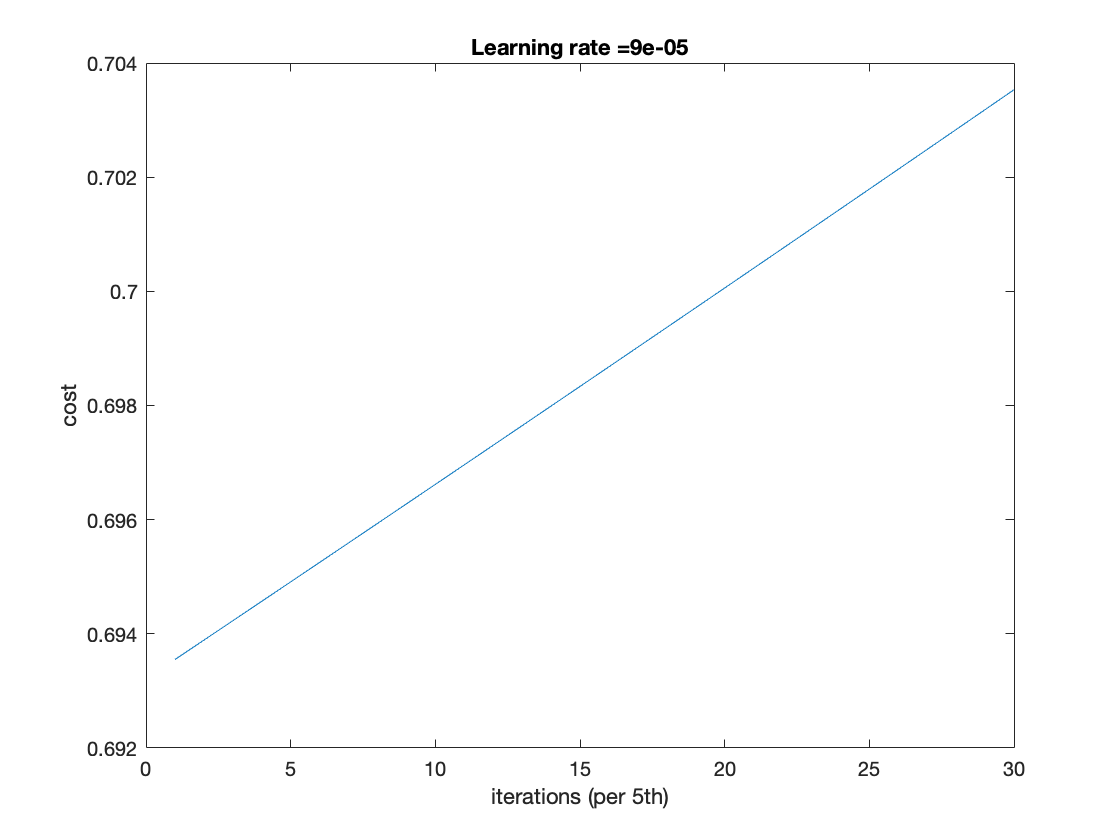


%CONSTANTS DEFINING THE MODEL
n_x = 26;     % 26 samples/input
n_h = 7 ;   % 7 hidden layers 
n_y = 1 ;   % 1 output 
layers_dims = [n_x, n_h, n_y];
parameters = two_layer_model(train_x, train_y, layers_dims, 0.00009, 153, true);

predictions_train = predict(train_x, train_y, parameters);

key = 1×1 cell array
    {'cache1'}


     1   153

Accuracy: 0.124183

## L-layer Neural Network 

%parameters = L_layer_model(train_x, train_y, layers_dims, 0.0009 ,153, true)
